# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

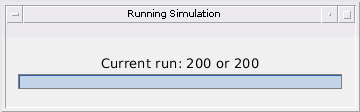

target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges =    23.0972       NaN       NaN       NaN       NaN
   24.0946       NaN       NaN       NaN       NaN
   25.0961   25.0962       NaN       NaN       NaN
   26.0970       NaN       NaN       NaN       NaN
   27.0943       NaN       NaN       NaN       NaN
   28.0971   28.0974       NaN       NaN       NaN
   29.0970       NaN       NaN       NaN       NaN
   30.0944       NaN       NaN       NaN       NaN
   31.0980   31.0980       NaN       NaN       NaN
   32.0970       NaN       NaN       NaN       NaN


actual_ranges =    23.0000   24.0001   25.0002   26.0002   27.0003   28.0004   29.0005   30.0006   31.0006   32.0007


estimated_velocities =   -29.4303       NaN       NaN       NaN       NaN
  -29.4299       NaN       NaN       NaN       NaN
  -30.8811  -29.4322       NaN       NaN       NaN
  -29.4290       NaN       NaN       NaN       NaN
  -29.4285       NaN       NaN       NaN       NaN
  -30.8811  -29.4310       NaN       NaN       NaN
  -29.4276       NaN       NaN       NaN       NaN
  -29.4286       NaN       NaN       NaN       NaN
  -30.8823  -29.4273       NaN       NaN       NaN
  -29.4256       NaN       NaN       NaN       NaN


actual_velocities =    -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected =      0     0     0     0     0     0     0     0     0     0


col_detection =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges =    20.9873       NaN       NaN       NaN       NaN
   20.9501       NaN       NaN       NaN       NaN
   20.9166       NaN       NaN       NaN       NaN
   20.8753       NaN       NaN       NaN       NaN
   20.8355       NaN       NaN       NaN       NaN
   20.8161       NaN       NaN       NaN       NaN
   20.8020       NaN       NaN       NaN       NaN
   20.7913       NaN       NaN       NaN       NaN
   20.7551       NaN       NaN       NaN       NaN
   20.7134       NaN       NaN       NaN       NaN


actual_ranges =    21.0000   20.9667   20.9333   20.9000   20.8667   20.8333   20.8000   20.7666   20.7333   20.7000


estimated_velocities =     1.0087       NaN       NaN       NaN       NaN
    1.0095       NaN       NaN       NaN       NaN
    1.0026       NaN       NaN       NaN       NaN
    1.0037       NaN       NaN       NaN       NaN
    1.0053       NaN       NaN       NaN       NaN
    0.9822       NaN       NaN       NaN       NaN
    0.9812       NaN       NaN       NaN       NaN
    1.0067       NaN       NaN       NaN       NaN
    1.0040       NaN       NaN       NaN       NaN
    1.0023       NaN       NaN       NaN       NaN


actual_velocities =      1     1     1     1     1     1     1     1     1     1


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0127
    0.0165
    0.0167
    0.0247
    0.0311
    0.0172
    0.0020
    0.0247
    0.0217
    0.0134


percent_error_velocities =     0.0087
    0.0095
    0.0026
    0.0037
    0.0053
    0.0178
    0.0188
    0.0067
    0.0040
    0.0023


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges =   109.9598       NaN       NaN       NaN       NaN
  209.7986  109.6420       NaN       NaN       NaN
  109.3104       NaN       NaN       NaN       NaN
  108.9547       NaN       NaN       NaN       NaN
  108.6397       NaN       NaN       NaN       NaN
  108.3091       NaN       NaN       NaN       NaN
  107.9590       NaN       NaN       NaN       NaN
  107.6388       NaN       NaN       NaN       NaN
  107.3083       NaN       NaN       NaN       NaN
  106.9616       NaN       NaN       NaN       NaN


actual_ranges =   110.0000  109.6666  109.3333  108.9999  108.6666  108.3332  107.9998  107.6665  107.3331  106.9998


estimated_velocities =     9.8507       NaN       NaN       NaN       NaN
  -24.2027    9.9028       NaN       NaN       NaN
    9.8508       NaN       NaN       NaN       NaN
    9.9020       NaN       NaN       NaN       NaN
    9.9090       NaN       NaN       NaN       NaN
    9.7580       NaN       NaN       NaN       NaN
    9.8936       NaN       NaN       NaN       NaN
    9.9135       NaN       NaN       NaN       NaN
    9.7639       NaN       NaN       NaN       NaN
    9.8498       NaN       NaN       NaN       NaN


actual_velocities =     10    10    10    10    10    10    10    10    10    10


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0402
    0.0246
    0.0228
    0.0452
    0.0269
    0.0241
    0.0409
    0.0277
    0.0248
    0.0382


percent_error_velocities =     0.1493
    0.0972
    0.1492
    0.0980
    0.0910
    0.2420
    0.1064
    0.0865
    0.2361
    0.1502


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges =     9.9583       NaN       NaN       NaN       NaN
    9.5977       NaN       NaN       NaN       NaN
    9.2454       NaN       NaN       NaN       NaN
    8.8547       NaN       NaN       NaN       NaN
    8.4939       NaN       NaN       NaN       NaN
    8.1336       NaN       NaN       NaN       NaN
    7.7769       NaN       NaN       NaN       NaN
    7.3867       NaN       NaN       NaN       NaN
    7.0288       NaN       NaN       NaN       NaN
    6.6722       NaN       NaN       NaN       NaN


actual_ranges =    10.0000    9.6333    9.2666    8.8999    8.5332    8.1665    7.7998    7.4331    7.0664    6.6997


estimated_velocities =    10.8294       NaN       NaN       NaN       NaN
   10.8902       NaN       NaN       NaN       NaN
   10.8842       NaN       NaN       NaN       NaN
   10.8478       NaN       NaN       NaN       NaN
   10.8698       NaN       NaN       NaN       NaN
   10.8691       NaN       NaN       NaN       NaN
   10.8430       NaN       NaN       NaN       NaN
   10.7688       NaN       NaN       NaN       NaN
   10.8902       NaN       NaN       NaN       NaN
   10.8279       NaN       NaN       NaN       NaN


actual_velocities =     11    11    11    11    11    11    11    11    11    11


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =     0.0417
    0.0356
    0.0212
    0.0452
    0.0393
    0.0329
    0.0229
    0.0465
    0.0377
    0.0276


percent_error_velocities =     0.1706
    0.1098
    0.1158
    0.1522
    0.1302
    0.1309
    0.1570
    0.2312
    0.1098
    0.1721


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges =    89.0951       NaN       NaN       NaN       NaN
   90.0926       NaN       NaN       NaN       NaN
   91.0947   91.0921       NaN       NaN       NaN
   92.0944   92.0967       NaN       NaN       NaN
   93.0940       NaN       NaN       NaN       NaN
   94.0962       NaN       NaN       NaN       NaN
   95.0944   95.0954       NaN       NaN       NaN
   96.0948   96.0946       NaN       NaN       NaN
   97.0983       NaN       NaN       NaN       NaN
   98.0945       NaN       NaN       NaN       NaN


actual_ranges =    89.0000   90.0001   91.0002   92.0002   93.0003   94.0004   95.0005   96.0006   97.0006   98.0007


estimated_velocities =   -29.4051       NaN       NaN       NaN       NaN
  -29.4008       NaN       NaN       NaN       NaN
  -29.3784  -30.8702       NaN       NaN       NaN
  -29.3821  -30.8682       NaN       NaN       NaN
  -29.4107       NaN       NaN       NaN       NaN
  -29.3950       NaN       NaN       NaN       NaN
  -29.3816  -30.8466       NaN       NaN       NaN
  -29.3789  -30.8532       NaN       NaN       NaN
  -29.4008       NaN       NaN       NaN       NaN
  -29.3867       NaN       NaN       NaN       NaN


actual_velocities =    -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected =      0     0     0     0     0     0     0     0     0     0


col_detection =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges =   106.9397       NaN       NaN       NaN       NaN
  106.3783       NaN       NaN       NaN       NaN
  105.8136       NaN       NaN       NaN       NaN
  105.2419       NaN       NaN       NaN       NaN
  104.6826       NaN       NaN       NaN       NaN
  104.1121       NaN       NaN       NaN       NaN
  103.5435       NaN       NaN       NaN       NaN
  102.9853       NaN       NaN       NaN       NaN
  102.4063       NaN       NaN       NaN       NaN
  101.8466       NaN       NaN       NaN       NaN


actual_ranges =   107.0000  106.4333  105.8666  105.2999  104.7331  104.1664  103.5997  103.0330  102.4663  101.8996


estimated_velocities =    16.6141       NaN       NaN       NaN       NaN
   16.6422       NaN       NaN       NaN       NaN
   16.6505       NaN       NaN       NaN       NaN
   16.6467       NaN       NaN       NaN       NaN
   16.6475       NaN       NaN       NaN       NaN
   16.6329       NaN       NaN       NaN       NaN
   16.6229       NaN       NaN       NaN       NaN
   16.6201       NaN       NaN       NaN       NaN
   16.6137       NaN       NaN       NaN       NaN
   16.6549       NaN       NaN       NaN       NaN


actual_velocities =     17    17    17    17    17    17    17    17    17    17


detected =      1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0603
    0.0550
    0.0530
    0.0579
    0.0505
    0.0543
    0.0563
    0.0478
    0.0600
    0.0530


percent_error_velocities = 10×1
    0.3859
    0.3578
    0.3495
    0.3533
    0.3525
    0.3671
    0.3771
    0.3799
    0.3863
    0.3451


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   41.9049       NaN       NaN       NaN       NaN
   40.9058       NaN       NaN       NaN       NaN
   39.9022       NaN       NaN       NaN       NaN
   38.9051       NaN       NaN       NaN       NaN
   37.9050       NaN       NaN       NaN       NaN
   36.9025       NaN       NaN       NaN       NaN
   35.9058       NaN       NaN       NaN       NaN
   34.9036       NaN       NaN       NaN       NaN
   33.9024       NaN       NaN       NaN       NaN
   32.9057       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   42.0000   40.9999   39.9998   38.9998   37.9997   36.9996   35.9995   34.9994   33.9994   32.9993


estimated_velocities = 10×5
   29.4221       NaN       NaN       NaN       NaN
   29.4253       NaN       NaN       NaN       NaN
   29.4251       NaN       NaN       NaN       NaN
   29.4211       NaN       NaN       NaN       NaN
   29.4285       NaN       NaN       NaN       NaN
   29.4280       NaN       NaN       NaN       NaN
   29.4245       NaN       NaN       NaN       NaN
   29.4279       NaN       NaN       NaN       NaN
   29.4251       NaN       NaN       NaN       NaN
   29.4268       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   67.0761       NaN       NaN       NaN       NaN
   67.8424       NaN       NaN       NaN       NaN
   68.6066       NaN       NaN       NaN       NaN
   69.3753       NaN       NaN       NaN       NaN
   70.1390       NaN       NaN       NaN       NaN
   70.9054       NaN       NaN       NaN       NaN
   71.6704       NaN       NaN       NaN       NaN
   72.4379       NaN       NaN       NaN       NaN
   73.2045       NaN       NaN       NaN       NaN
   73.9726       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   67.0000   67.7667   68.5335   69.3002   70.0669   70.8336   71.6004   72.3671   73.1338   73.9006


estimated_velocities = 10×5
  -22.5354       NaN       NaN       NaN       NaN
  -22.5215       NaN       NaN       NaN       NaN
  -22.5255       NaN       NaN       NaN       NaN
  -22.5197       NaN       NaN       NaN       NaN
  -22.5245       NaN       NaN       NaN       NaN
  -22.5238       NaN       NaN       NaN       NaN
  -22.5271       NaN       NaN       NaN       NaN
  -22.5342       NaN       NaN       NaN       NaN
  -22.5273       NaN       NaN       NaN       NaN
  -22.5243       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0761
    0.0757
    0.0732
    0.0751
    0.0721
    0.0717
    0.0701
    0.0708
    0.0706
    0.0720


percent_error_velocities = 10×1
    0.4646
    0.4785
    0.4745
    0.4803
    0.4755
    0.4762
    0.4729
    0.4658
    0.4727
    0.4757


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  142.0881  142.0964       NaN       NaN       NaN
  143.0739  143.0584       NaN       NaN       NaN
  144.0313  144.0293       NaN       NaN       NaN
  144.9948  144.9769       NaN       NaN       NaN
  145.9545  145.9678       NaN       NaN       NaN
  146.9284  146.9338       NaN       NaN       NaN
  147.8880       NaN       NaN       NaN       NaN
  148.8517  148.8557       NaN       NaN       NaN
  149.8258  149.8247       NaN       NaN       NaN
  150.7946  150.7882       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  142.9667  143.9335  144.9002  145.8670  146.8337  147.8005  148.7672  149.7340  150.7007


estimated_velocities = 10×5
  -28.4106  -29.7628       NaN       NaN       NaN
  -29.7988  -28.4059       NaN       NaN       NaN
  -28.3922  -29.8019       NaN       NaN       NaN
  -28.4297  -29.6682       NaN       NaN       NaN
  -29.8365  -28.4117       NaN       NaN       NaN
  -29.7994  -28.4128       NaN       NaN       NaN
  -28.4525       NaN       NaN       NaN       NaN
  -29.8328  -28.4003       NaN       NaN       NaN
  -29.7643  -28.4142       NaN       NaN       NaN
  -29.8929  -28.4001       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   54.0196       NaN       NaN       NaN       NaN
   54.1598       NaN       NaN       NaN       NaN
   54.2672       NaN       NaN       NaN       NaN
   54.4099       NaN       NaN       NaN       NaN
   54.5575       NaN       NaN       NaN       NaN
   54.6790       NaN       NaN       NaN       NaN
   54.8027       NaN       NaN       NaN       NaN
   54.9454       NaN       NaN       NaN       NaN
  202.9567   55.0954       NaN       NaN       NaN
   55.2010       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   54.0000   54.1333   54.2667   54.4000   54.5334   54.6667   54.8001   54.9334   55.0668   55.2001


estimated_velocities = 10×5
   -3.9462       NaN       NaN       NaN       NaN
   -3.8882       NaN       NaN       NaN       NaN
   -3.9266       NaN       NaN       NaN       NaN
   -3.9604       NaN       NaN       NaN       NaN
   -3.9382       NaN       NaN       NaN       NaN
   -3.8590       NaN       NaN       NaN       NaN
   -3.9316       NaN       NaN       NaN       NaN
   -3.9633       NaN       NaN       NaN       NaN
   -8.7034   -3.9324       NaN       NaN       NaN
   -3.8681       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0196
    0.0265
    0.0005
    0.0098
    0.0241
    0.0123
    0.0026
    0.0120
    0.0286
    0.0009


percent_error_velocities = 10×1
    0.0538
    0.1118
    0.0734
    0.0396
    0.0618
    0.1410
    0.0684
    0.0367
    0.0676
    0.1319


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   19.0868   19.0869       NaN       NaN       NaN
   20.0214   20.0211       NaN       NaN       NaN
   20.9576   20.9571       NaN       NaN       NaN
   21.8920   21.8917       NaN       NaN       NaN
   22.8246   22.8248       NaN       NaN       NaN
   23.7569   23.7570       NaN       NaN       NaN
   24.6887   24.6890       NaN       NaN       NaN
   25.6214   25.6213       NaN       NaN       NaN
   26.5547   26.5544       NaN       NaN       NaN
   27.4896   27.4889       NaN       NaN       NaN


actual_ranges = 1×10
   19.0000   19.9334   20.8668   21.8002   22.7336   23.6670   24.6005   25.5339   26.4673   27.4007


estimated_velocities = 10×5
  -28.8170  -27.4479       NaN       NaN       NaN
  -28.8129  -27.4490       NaN       NaN       NaN
  -28.8165  -27.4485       NaN       NaN       NaN
  -28.8183  -27.4469       NaN       NaN       NaN
  -28.8191  -27.4455       NaN       NaN       NaN
  -28.8189  -27.4453       NaN       NaN       NaN
  -28.8153  -27.4457       NaN       NaN       NaN
  -28.8150  -27.4454       NaN       NaN       NaN
  -28.8112  -27.4470       NaN       NaN       NaN
  -28.8087  -27.4477       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   77.0477       NaN       NaN       NaN       NaN
   77.4086       NaN       NaN       NaN       NaN
   77.7639       NaN       NaN       NaN       NaN
   78.1194       NaN       NaN       NaN       NaN
   78.5180       NaN       NaN       NaN       NaN
   43.2344   78.8691       NaN       NaN       NaN
   79.2288       NaN       NaN       NaN       NaN
   79.6030       NaN       NaN       NaN       NaN
   79.9843       NaN       NaN       NaN       NaN
   80.3326       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   77.0000   77.3667   77.7334   78.1001   78.4668   78.8335   79.2002   79.5669   79.9336   80.3003


estimated_velocities = 10×5
  -10.8147       NaN       NaN       NaN       NaN
  -10.8504       NaN       NaN       NaN       NaN
  -10.8967       NaN       NaN       NaN       NaN
  -10.8853       NaN       NaN       NaN       NaN
  -10.8724       NaN       NaN       NaN       NaN
   10.8951  -10.8987       NaN       NaN       NaN
  -10.8568       NaN       NaN       NaN       NaN
  -10.7091       NaN       NaN       NaN       NaN
  -10.9043       NaN       NaN       NaN       NaN
  -10.9016       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0477
    0.0419
    0.0305
    0.0193
    0.0512
    0.0356
    0.0287
    0.0361
    0.0508
    0.0324


percent_error_velocities = 10×1
    0.1853
    0.1496
    0.1033
    0.1147
    0.1276
    0.1013
    0.1432
    0.2909
    0.0957
    0.0984


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   89.0939       NaN       NaN       NaN       NaN
   90.0615       NaN       NaN       NaN       NaN
   91.0243       NaN       NaN       NaN       NaN
   91.9943       NaN       NaN       NaN       NaN
   92.9602       NaN       NaN       NaN       NaN
   93.9260   93.9283       NaN       NaN       NaN
   94.8920       NaN       NaN       NaN       NaN
   95.8609       NaN       NaN       NaN       NaN
   96.8261       NaN       NaN       NaN       NaN
   97.7919       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   89.9667   90.9335   91.9002   92.8670   93.8337   94.8005   95.7672   96.7340   97.7007


estimated_velocities = 10×5
  -28.4256       NaN       NaN       NaN       NaN
  -28.4221       NaN       NaN       NaN       NaN
  -28.4186       NaN       NaN       NaN       NaN
  -28.4256       NaN       NaN       NaN       NaN
  -28.4096       NaN       NaN       NaN       NaN
  -29.8347  -28.4240       NaN       NaN       NaN
  -28.4179       NaN       NaN       NaN       NaN
  -28.4169       NaN       NaN       NaN       NaN
  -28.4155       NaN       NaN       NaN       NaN
  -28.4215       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   40.0300       NaN       NaN       NaN       NaN
   40.0961       NaN       NaN       NaN       NaN
   40.2015       NaN       NaN       NaN       NaN
   40.3119       NaN       NaN       NaN       NaN
   40.4227       NaN       NaN       NaN       NaN
   40.5304       NaN       NaN       NaN       NaN
   40.5971       NaN       NaN       NaN       NaN
   40.7007       NaN       NaN       NaN       NaN
   40.8107       NaN       NaN       NaN       NaN
   40.9207       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   40.1000   40.2000   40.3000   40.4000   40.5000   40.6000   40.7001   40.8001   40.9001


estimated_velocities = 10×5
   -2.9660       NaN       NaN       NaN       NaN
   -2.8760       NaN       NaN       NaN       NaN
   -2.9528       NaN       NaN       NaN       NaN
   -2.9829       NaN       NaN       NaN       NaN
   -2.9852       NaN       NaN       NaN       NaN
   -2.9538       NaN       NaN       NaN       NaN
   -2.8880       NaN       NaN       NaN       NaN
   -2.9616       NaN       NaN       NaN       NaN
   -2.9821       NaN       NaN       NaN       NaN
   -2.9766       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0300
    0.0039
    0.0015
    0.0118
    0.0227
    0.0303
    0.0029
    0.0006
    0.0107
    0.0206


percent_error_velocities = 10×1
    0.0340
    0.1240
    0.0472
    0.0171
    0.0148
    0.0462
    0.1120
    0.0384
    0.0179
    0.0234


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   99.0483       NaN       NaN       NaN       NaN
   99.5803       NaN       NaN       NaN       NaN
  100.1163       NaN       NaN       NaN       NaN
  100.6540       NaN       NaN       NaN       NaN
  101.1915       NaN       NaN       NaN       NaN
  101.7244       NaN       NaN       NaN       NaN
  102.2509       NaN       NaN       NaN       NaN
  102.7833       NaN       NaN       NaN       NaN
  103.3232       NaN       NaN       NaN       NaN
  103.8551       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   99.5334  100.0668  100.6001  101.1335  101.6669  102.2003  102.7336  103.2670  103.8004


estimated_velocities = 10×5
  -15.6714       NaN       NaN       NaN       NaN
  -15.7324       NaN       NaN       NaN       NaN
  -15.7169       NaN       NaN       NaN       NaN
  -15.7377       NaN       NaN       NaN       NaN
  -15.7598       NaN       NaN       NaN       NaN
  -15.7661       NaN       NaN       NaN       NaN
  -15.6831       NaN       NaN       NaN       NaN
  -15.6361       NaN       NaN       NaN       NaN
  -15.6882       NaN       NaN       NaN       NaN
  -15.7109       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0483
    0.0469
    0.0496
    0.0539
    0.0580
    0.0575
    0.0506
    0.0497
    0.0562
    0.0547


percent_error_velocities = 10×1
    0.3286
    0.2676
    0.2831
    0.2623
    0.2402
    0.2339
    0.3169
    0.3639
    0.3118
    0.2891


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   20.1003   20.1001       NaN       NaN       NaN
   21.1340   21.1340       NaN       NaN       NaN
   22.1675   22.1674       NaN       NaN       NaN
   23.2013   23.2012       NaN       NaN       NaN
   24.2345   24.2346       NaN       NaN       NaN
   25.2679   25.2677       NaN       NaN       NaN
   26.3009   26.3011       NaN       NaN       NaN
   27.3338   27.3337       NaN       NaN       NaN
   28.3667   28.3664       NaN       NaN       NaN
   29.3992   29.3993       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   21.0334   22.0668   23.1003   24.1337   25.1671   26.2005   27.2339   28.2673   29.3008


estimated_velocities = 10×5
  -30.3936  -31.9161       NaN       NaN       NaN
  -30.3933  -31.9165       NaN       NaN       NaN
  -30.3923  -31.9145       NaN       NaN       NaN
  -30.3921  -31.9128       NaN       NaN       NaN
  -30.3919  -31.9131       NaN       NaN       NaN
  -30.3920  -31.9110       NaN       NaN       NaN
  -30.3916  -31.9105       NaN       NaN       NaN
  -30.3911  -31.9089       NaN       NaN       NaN
  -30.3904  -31.9069       NaN       NaN       NaN
  -30.3946  -31.9022       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  128.8831  128.8899       NaN       NaN       NaN
  127.6853  127.6828       NaN       NaN       NaN
  126.4804  126.4859       NaN       NaN       NaN
  125.2952  125.2885       NaN       NaN       NaN
  124.0840  124.0830       NaN       NaN       NaN
  122.8831  122.8862       NaN       NaN       NaN
  121.6897  121.6827       NaN       NaN       NaN
  120.4855  120.4808       NaN       NaN       NaN
  119.2888  119.2834       NaN       NaN       NaN
  118.0819  118.0855       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  127.7999  126.5998  125.3997  124.1996  122.9995  121.7994  120.5993  119.3992  118.1991


estimated_velocities = 10×5
   36.9963   35.2191       NaN       NaN       NaN
   36.9803   35.2499       NaN       NaN       NaN
   36.9535   35.2274       NaN       NaN       NaN
   36.9801   35.2253       NaN       NaN       NaN
   36.9844   35.2393       NaN       NaN       NaN
   36.9748   35.2086       NaN       NaN       NaN
   36.9674   35.2419       NaN       NaN       NaN
   36.9880   35.2189       NaN       NaN       NaN
   36.9726   35.2491       NaN       NaN       NaN
   36.9672   35.2437       NaN       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   15.9135   15.9136       NaN       NaN       NaN
   15.0147   15.0138       NaN       NaN       NaN
   14.1143   14.1139       NaN       NaN       NaN
   13.2122   13.2126       NaN       NaN       NaN
   12.3132   12.3139       NaN       NaN       NaN
   11.4123   11.4120       NaN       NaN       NaN
   10.5148   10.5142       NaN       NaN       NaN
    9.6120    9.6115       NaN       NaN       NaN
    8.7137    8.7142       NaN       NaN       NaN
    7.8105    7.8109       NaN       NaN       NaN


actual_ranges = 1×10
   16.0000   15.0999   14.1999   13.2998   12.3997   11.4996   10.5996    9.6995    8.7994    7.8993


estimated_velocities = 10×5
   27.7863   26.4592       NaN       NaN       NaN
   27.7842   26.4628       NaN       NaN       NaN
   27.7817   26.4611       NaN       NaN       NaN
   27.7809   26.4637       NaN       NaN       NaN
   27.7851   26.4615       NaN       NaN       NaN
   27.7845   26.4645       NaN       NaN       NaN
   27.7859   26.4619       NaN       NaN       NaN
   27.7803   26.4658       NaN       NaN       NaN
   27.7832   26.4639       NaN       NaN       NaN
   27.7872   26.4641       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  123.9402       NaN       NaN       NaN       NaN
  123.3767       NaN       NaN       NaN       NaN
  122.8170       NaN       NaN       NaN       NaN
  122.2459       NaN       NaN       NaN       NaN
  121.6815       NaN       NaN       NaN       NaN
  121.1098       NaN       NaN       NaN       NaN
  120.5455       NaN       NaN       NaN       NaN
  119.9807       NaN       NaN       NaN       NaN
   25.2485  119.4101       NaN       NaN       NaN
  118.8456       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  123.4333  122.8666  122.2999  121.7331  121.1664  120.5997  120.0330  119.4663  118.8996


estimated_velocities = 10×5
   16.6220       NaN       NaN       NaN       NaN
   16.6456       NaN       NaN       NaN       NaN
   16.6229       NaN       NaN       NaN       NaN
   16.6659       NaN       NaN       NaN       NaN
   16.6031       NaN       NaN       NaN       NaN
   16.6152       NaN       NaN       NaN       NaN
   16.6074       NaN       NaN       NaN       NaN
   16.6544       NaN       NaN       NaN       NaN
  -30.3161   16.6345       NaN       NaN       NaN
   16.6784       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0598
    0.0565
    0.0495
    0.0540
    0.0517
    0.0567
    0.0543
    0.0523
    0.0562
    0.0540


percent_error_velocities = 10×1
    0.3780
    0.3544
    0.3771
    0.3341
    0.3969
    0.3848
    0.3926
    0.3456
    0.3655
    0.3216


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   59.0245       NaN       NaN       NaN       NaN
  167.2672   59.0646       NaN       NaN       NaN
   59.0422       NaN       NaN       NaN       NaN
   59.0774       NaN       NaN       NaN       NaN
   59.1161       NaN       NaN       NaN       NaN
   59.1457       NaN       NaN       NaN       NaN
   59.1866       NaN       NaN       NaN       NaN
   59.2278       NaN       NaN       NaN       NaN
   59.2626       NaN       NaN       NaN       NaN
   59.2987       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   59.0333   59.0667   59.1000   59.1333   59.1667   59.2000   59.2334   59.2667   59.3000


estimated_velocities = 10×5
   -0.9970       NaN       NaN       NaN       NaN
   33.7386   -1.0021       NaN       NaN       NaN
   -1.0025       NaN       NaN       NaN       NaN
   -0.9920       NaN       NaN       NaN       NaN
   -0.9945       NaN       NaN       NaN       NaN
   -1.0069       NaN       NaN       NaN       NaN
   -1.0072       NaN       NaN       NaN       NaN
   -1.0065       NaN       NaN       NaN       NaN
   -1.0116       NaN       NaN       NaN       NaN
   -1.0091       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0245
    0.0312
    0.0245
    0.0226
    0.0173
    0.0210
    0.0134
    0.0056
    0.0041
    0.0014


percent_error_velocities = 10×1
    0.0030
    0.0021
    0.0025
    0.0080
    0.0055
    0.0069
    0.0072
    0.0065
    0.0116
    0.0091


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   28.9554       NaN       NaN       NaN       NaN
   28.5229       NaN       NaN       NaN       NaN
   28.0914       NaN       NaN       NaN       NaN
   27.6601       NaN       NaN       NaN       NaN
   27.2278       NaN       NaN       NaN       NaN
   26.7942       NaN       NaN       NaN       NaN
   26.3604       NaN       NaN       NaN       NaN
   25.9268       NaN       NaN       NaN       NaN
   25.4936       NaN       NaN       NaN       NaN
   25.0602       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   28.5666   28.1333   27.6999   27.2665   26.8332   26.3998   25.9664   25.5331   25.0997


estimated_velocities = 10×5
   12.7763       NaN       NaN       NaN       NaN
   12.8172       NaN       NaN       NaN       NaN
   12.7876       NaN       NaN       NaN       NaN
   12.8172       NaN       NaN       NaN       NaN
   12.7682       NaN       NaN       NaN       NaN
   12.7107       NaN       NaN       NaN       NaN
   12.6817       NaN       NaN       NaN       NaN
   12.6994       NaN       NaN       NaN       NaN
   12.7539       NaN       NaN       NaN       NaN
   12.8067       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0446
    0.0437
    0.0419
    0.0398
    0.0388
    0.0389
    0.0394
    0.0397
    0.0395
    0.0395


percent_error_velocities = 10×1
    0.2237
    0.1828
    0.2124
    0.1828
    0.2318
    0.2893
    0.3183
    0.3006
    0.2461
    0.1933


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  140.9236  140.9245       NaN       NaN       NaN
  140.0861  140.0870       NaN       NaN       NaN
  139.2472  139.2549       NaN       NaN       NaN
  138.4321  138.4167       NaN       NaN       NaN
  137.5918  137.5987       NaN       NaN       NaN
  136.7524  136.7535       NaN       NaN       NaN
  135.9211  135.9209       NaN       NaN       NaN
  135.0949  135.0883       NaN       NaN       NaN
  134.2528  134.2493       NaN       NaN       NaN
  133.4154  133.4180       NaN       NaN       NaN


actual_ranges = 1×10
  141.0000  140.1666  139.3332  138.4998  137.6664  136.8330  135.9996  135.1662  134.3328  133.4994


estimated_velocities = 10×5
   25.7084   24.5218       NaN       NaN       NaN
   25.6938   24.4865       NaN       NaN       NaN
   25.6504   24.4671       NaN       NaN       NaN
   25.6655   24.4789       NaN       NaN       NaN
   25.6416   24.4932       NaN       NaN       NaN
   25.6686   24.4807       NaN       NaN       NaN
   25.7262   24.4936       NaN       NaN       NaN
   25.6852   24.5061       NaN       NaN       NaN
   25.6495   24.4827       NaN       NaN       NaN
   25.6989   24.5238       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     0     0     0     0     0     0     1     0     1


col_detection = 10×1
     2
     0
     0
     0
     0
     0
     0
     0
     0
     2


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0755
         0
         0
         0
         0
         0
         0
         0
         0
    0.0814


percent_error_velocities = 10×1
    0.4782
         0
         0
         0
         0
         0
         0
         0
         0
    0.4762


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  138.0261       NaN       NaN       NaN       NaN
  138.0910       NaN       NaN       NaN       NaN
  138.1993       NaN       NaN       NaN       NaN
  138.3130       NaN       NaN       NaN       NaN
  138.4223       NaN       NaN       NaN       NaN
  138.5163       NaN       NaN       NaN       NaN
  125.4024  138.5918       NaN       NaN       NaN
  138.6996       NaN       NaN       NaN       NaN
  138.8101       NaN       NaN       NaN       NaN
  138.9227       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  138.1000  138.2000  138.3000  138.4000  138.5000  138.6000  138.7001  138.8001  138.9001


estimated_velocities = 10×5
   -2.8545       NaN       NaN       NaN       NaN
   -2.9546       NaN       NaN       NaN       NaN
   -3.0057       NaN       NaN       NaN       NaN
   -2.9952       NaN       NaN       NaN       NaN
   -2.9668       NaN       NaN       NaN       NaN
   -2.8869       NaN       NaN       NaN       NaN
    3.7972   -2.9869       NaN       NaN       NaN
   -2.9931       NaN       NaN       NaN       NaN
   -2.9879       NaN       NaN       NaN       NaN
   -2.9579       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.0261
    0.0090
    0.0007
    0.0129
    0.0223
    0.0163
    0.0082
    0.0004
    0.0100
    0.0226


percent_error_velocities = 10×1
    0.1455
    0.0454
    0.0057
    0.0048
    0.0332
    0.1131
    0.0131
    0.0069
    0.0121
    0.0421


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  102.9968       NaN       NaN       NaN       NaN
  103.1780       NaN       NaN       NaN       NaN
  103.3736       NaN       NaN       NaN       NaN
  103.4940       NaN       NaN       NaN       NaN
  103.6809       NaN       NaN       NaN       NaN
  103.8710       NaN       NaN       NaN       NaN
  103.9871       NaN       NaN       NaN       NaN
  104.1829       NaN       NaN       NaN       NaN
  104.3667       NaN       NaN       NaN       NaN
  104.4910       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  103.1667  103.3334  103.5000  103.6667  103.8334  104.0001  104.1668  104.3334  104.5001


estimated_velocities = 10×5
   -4.9239       NaN       NaN       NaN       NaN
   -4.9399       NaN       NaN       NaN       NaN
   -4.9432       NaN       NaN       NaN       NaN
   -4.9303       NaN       NaN       NaN       NaN
   -4.9766       NaN       NaN       NaN       NaN
   -4.9734       NaN       NaN       NaN       NaN
   -4.9500       NaN       NaN       NaN       NaN
   -4.9764       NaN       NaN       NaN       NaN
   -4.9445       NaN       NaN       NaN       NaN
   -4.9814       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0032
    0.0113
    0.0402
    0.0061
    0.0142
    0.0376
    0.0130
    0.0161
    0.0333
    0.0091


percent_error_velocities = 10×1
    0.0761
    0.0601
    0.0568
    0.0697
    0.0234
    0.0266
    0.0500
    0.0236
    0.0555
    0.0186


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  136.0637       NaN       NaN       NaN       NaN
  136.7306       NaN       NaN       NaN       NaN
  137.3956       NaN       NaN       NaN       NaN
  138.0610       NaN       NaN       NaN       NaN
  138.7362       NaN       NaN       NaN       NaN
  139.3973       NaN       NaN       NaN       NaN
  140.0619       NaN       NaN       NaN       NaN
  140.7261       NaN       NaN       NaN       NaN
  123.7622  141.3959       NaN       NaN       NaN
  142.0607       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  136.0000  136.6667  137.3334  138.0002  138.6669  139.3336  140.0003  140.6670  141.3338  142.0005


estimated_velocities = 10×5
  -19.6251       NaN       NaN       NaN       NaN
  -19.5813       NaN       NaN       NaN       NaN
  -19.6126       NaN       NaN       NaN       NaN
  -19.5922       NaN       NaN       NaN       NaN
  -19.5920       NaN       NaN       NaN       NaN
  -19.5897       NaN       NaN       NaN       NaN
  -19.5996       NaN       NaN       NaN       NaN
  -19.5850       NaN       NaN       NaN       NaN
  -18.9886  -19.5676       NaN       NaN       NaN
  -19.5835       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0637
    0.0639
    0.0622
    0.0608
    0.0693
    0.0637
    0.0616
    0.0591
    0.0622
    0.0602


percent_error_velocities = 10×1
    0.3749
    0.4187
    0.3874
    0.4078
    0.4080
    0.4103
    0.4004
    0.4150
    0.4324
    0.4165


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  135.0989  135.0999       NaN       NaN       NaN
  136.1698  136.1711       NaN       NaN       NaN
  137.2335  137.2358       NaN       NaN       NaN
  138.3038  138.2980       NaN       NaN       NaN
  139.3618  139.3684       NaN       NaN       NaN
  140.4289  140.4332       NaN       NaN       NaN
  141.5005  141.5124       NaN       NaN       NaN
  142.5727  142.5675       NaN       NaN       NaN
  143.6432  143.6353       NaN       NaN       NaN
  144.6917  144.6972       NaN       NaN       NaN


actual_ranges = 1×10
  135.0000  136.0668  137.1335  138.2003  139.2670  140.3338  141.4005  142.4673  143.5340  144.6008


estimated_velocities = 10×5
  -32.8332  -31.3134       NaN       NaN       NaN
  -31.2918  -32.8801       NaN       NaN       NaN
  -31.3178  -32.9358       NaN       NaN       NaN
  -31.3261  -32.8656       NaN       NaN       NaN
  -32.8885  -31.3211       NaN       NaN       NaN
  -32.8984  -31.3058       NaN       NaN       NaN
  -31.3402  -32.8961       NaN       NaN       NaN
  -32.8207  -31.3053       NaN       NaN       NaN
  -31.2864  -32.8763       NaN       NaN       NaN
  -32.9055  -31.2941       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   13.0167       NaN       NaN       NaN       NaN
   13.1757       NaN       NaN       NaN       NaN
   13.3561       NaN       NaN       NaN       NaN
   13.5207       NaN       NaN       NaN       NaN
   13.6740       NaN       NaN       NaN       NaN
   13.8545       NaN       NaN       NaN       NaN
   14.0271       NaN       NaN       NaN       NaN
   14.1714       NaN       NaN       NaN       NaN
   14.3556       NaN       NaN       NaN       NaN
   14.5286       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   13.0000   13.1667   13.3334   13.5000   13.6667   13.8334   14.0001   14.1668   14.3334   14.5001


estimated_velocities = 10×5
   -4.8415       NaN       NaN       NaN       NaN
   -4.9439       NaN       NaN       NaN       NaN
   -4.9532       NaN       NaN       NaN       NaN
   -4.8329       NaN       NaN       NaN       NaN
   -4.9496       NaN       NaN       NaN       NaN
   -4.9485       NaN       NaN       NaN       NaN
   -4.8326       NaN       NaN       NaN       NaN
   -4.9547       NaN       NaN       NaN       NaN
   -4.9432       NaN       NaN       NaN       NaN
   -4.9029       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0167
    0.0090
    0.0228
    0.0207
    0.0073
    0.0211
    0.0270
    0.0046
    0.0222
    0.0285


percent_error_velocities = 10×1
    0.1585
    0.0561
    0.0468
    0.1671
    0.0504
    0.0515
    0.1674
    0.0453
    0.0568
    0.0971


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   39.0944       NaN       NaN       NaN       NaN
   40.0977       NaN       NaN       NaN       NaN
   41.0949       NaN       NaN       NaN       NaN
   42.0957       NaN       NaN       NaN       NaN
   43.0976       NaN       NaN       NaN       NaN
   44.0946       NaN       NaN       NaN       NaN
   45.0969       NaN       NaN       NaN       NaN
   46.0975       NaN       NaN       NaN       NaN
   47.0948       NaN       NaN       NaN       NaN
   48.0978       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   40.0001   41.0002   42.0002   43.0003   44.0004   45.0005   46.0006   47.0006   48.0007


estimated_velocities = 10×5
  -29.4273       NaN       NaN       NaN       NaN
  -29.4241       NaN       NaN       NaN       NaN
  -29.4197       NaN       NaN       NaN       NaN
  -29.4253       NaN       NaN       NaN       NaN
  -29.4220       NaN       NaN       NaN       NaN
  -29.4212       NaN       NaN       NaN       NaN
  -29.4252       NaN       NaN       NaN       NaN
  -29.4180       NaN       NaN       NaN       NaN
  -29.4181       NaN       NaN       NaN       NaN
  -29.4222       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  109.8978  109.8946       NaN       NaN       NaN
  194.2309  108.7931  108.7938       NaN       NaN
  107.6935  107.6933       NaN       NaN       NaN
  106.5974  106.5941       NaN       NaN       NaN
  105.4981  105.4938       NaN       NaN       NaN
  104.3947  104.3972       NaN       NaN       NaN
  103.2949  103.2932       NaN       NaN       NaN
  102.1910  102.1933       NaN       NaN       NaN
  101.0967  101.0947       NaN       NaN       NaN
   99.9935   99.9959       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  108.8999  107.7998  106.6997  105.5996  104.4996  103.3995  102.2994  101.1993  100.0992


estimated_velocities = 10×5
   33.8931   32.3303       NaN       NaN       NaN
   12.6350   33.8712   32.3072       NaN       NaN
   33.9013   32.3236       NaN       NaN       NaN
   33.9368   32.3069       NaN       NaN       NaN
   33.8819   32.3262       NaN       NaN       NaN
   33.9226   32.3168       NaN       NaN       NaN
   33.9380   32.3352       NaN       NaN       NaN
   33.9089   32.3316       NaN       NaN       NaN
   33.9464   32.3255       NaN       NaN       NaN
   33.9236   32.3446       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  218.7392    6.9575       NaN       NaN       NaN
    6.5651       NaN       NaN       NaN       NaN
    6.1610       NaN       NaN       NaN       NaN
    5.7641       NaN       NaN       NaN       NaN
    5.3466       NaN       NaN       NaN       NaN
    4.9568       NaN       NaN       NaN       NaN
    4.5693       NaN       NaN       NaN       NaN
    4.1594       NaN       NaN       NaN       NaN
    3.7611       NaN       NaN       NaN       NaN
    3.3636       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    7.0000    6.6000    6.1999    5.7999    5.3999    4.9998    4.5998    4.1998    3.7997    3.3997


estimated_velocities = 10×5
  -24.5847   11.8215       NaN       NaN       NaN
   11.8345       NaN       NaN       NaN       NaN
   11.7495       NaN       NaN       NaN       NaN
   11.7071       NaN       NaN       NaN       NaN
   11.8094       NaN       NaN       NaN       NaN
   11.8629       NaN       NaN       NaN       NaN
   11.8763       NaN       NaN       NaN       NaN
   11.7105       NaN       NaN       NaN       NaN
   11.6986       NaN       NaN       NaN       NaN
   11.7193       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0425
    0.0348
    0.0389
    0.0358
    0.0533
    0.0430
    0.0305
    0.0404
    0.0386
    0.0361


percent_error_velocities = 10×1
    0.1785
    0.1655
    0.2505
    0.2929
    0.1906
    0.1371
    0.1237
    0.2895
    0.3014
    0.2807


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   77.9442       NaN       NaN       NaN       NaN
   77.3806       NaN       NaN       NaN       NaN
   76.8106       NaN       NaN       NaN       NaN
   76.2444       NaN       NaN       NaN       NaN
   75.6817       NaN       NaN       NaN       NaN
   75.1095       NaN       NaN       NaN       NaN
   74.5477       NaN       NaN       NaN       NaN
   73.9787       NaN       NaN       NaN       NaN
   73.4101       NaN       NaN       NaN       NaN
   72.8476       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   77.4333   76.8666   76.2999   75.7331   75.1664   74.5997   74.0330   73.4663   72.8996


estimated_velocities = 10×5
   16.6205       NaN       NaN       NaN       NaN
   16.6232       NaN       NaN       NaN       NaN
   16.6195       NaN       NaN       NaN       NaN
   16.6422       NaN       NaN       NaN       NaN
   16.6693       NaN       NaN       NaN       NaN
   16.6673       NaN       NaN       NaN       NaN
   16.6506       NaN       NaN       NaN       NaN
   16.6571       NaN       NaN       NaN       NaN
   16.6222       NaN       NaN       NaN       NaN
   16.6317       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0558
    0.0527
    0.0559
    0.0555
    0.0514
    0.0570
    0.0520
    0.0543
    0.0562
    0.0520


percent_error_velocities = 10×1
    0.3795
    0.3768
    0.3805
    0.3578
    0.3307
    0.3327
    0.3494
    0.3429
    0.3778
    0.3683


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   71.0161       NaN       NaN       NaN       NaN
   71.2962       NaN       NaN       NaN       NaN
   71.5541       NaN       NaN       NaN       NaN
   71.8300       NaN       NaN       NaN       NaN
   72.0900       NaN       NaN       NaN       NaN
   72.3650       NaN       NaN       NaN       NaN
   72.6254       NaN       NaN       NaN       NaN
   72.8992       NaN       NaN       NaN       NaN
  185.8335   73.1527       NaN       NaN       NaN
   73.4255       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   71.0000   71.2667   71.5334   71.8001   72.0668   72.3334   72.6001   72.8668   73.1335   73.4002


estimated_velocities = 10×5
   -7.8931       NaN       NaN       NaN       NaN
   -7.8399       NaN       NaN       NaN       NaN
   -7.8928       NaN       NaN       NaN       NaN
   -7.8352       NaN       NaN       NaN       NaN
   -7.9050       NaN       NaN       NaN       NaN
   -7.8326       NaN       NaN       NaN       NaN
   -7.9061       NaN       NaN       NaN       NaN
   -7.8041       NaN       NaN       NaN       NaN
  -10.8797   -7.9599       NaN       NaN       NaN
   -7.7387       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    0.0161
    0.0295
    0.0207
    0.0300
    0.0232
    0.0316
    0.0253
    0.0324
    0.0192
    0.0253


percent_error_velocities = 10×1
    0.1069
    0.1601
    0.1072
    0.1648
    0.0950
    0.1674
    0.0939
    0.1959
    0.0401
    0.2613


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  131.0819  131.0826       NaN       NaN       NaN
  131.9125  131.9131       NaN       NaN       NaN
  132.7457  132.7454       NaN       NaN       NaN
  133.5741       NaN       NaN       NaN       NaN
  134.4082  134.4082       NaN       NaN       NaN
  135.2528  135.2576       NaN       NaN       NaN
  136.0779  136.0769       NaN       NaN       NaN
  136.9197  136.9140       NaN       NaN       NaN
  137.7408  137.7482       NaN       NaN       NaN
  138.5873  138.5832       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  131.8334  132.6668  133.5002  134.3336  135.1670  136.0004  136.8338  137.6672  138.5006


estimated_velocities = 10×5
  -25.6722  -24.4489       NaN       NaN       NaN
  -25.6850  -24.4648       NaN       NaN       NaN
  -24.4821  -25.6865       NaN       NaN       NaN
  -24.5150       NaN       NaN       NaN       NaN
  -25.6803  -24.4765       NaN       NaN       NaN
  -25.6544  -24.4944       NaN       NaN       NaN
  -25.6887  -24.5138       NaN       NaN       NaN
  -24.4656  -25.7251       NaN       NaN       NaN
  -25.6802  -24.4950       NaN       NaN       NaN
  -25.6707  -24.4818       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     0     0     0     1     0     0     1     0     0     0


col_detection = 10×1
     0
     0
     0
     1
     0
     0
     2
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
         0
         0
         0
    0.0739
         0
         0
    0.0765
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
         0
    0.4850
         0
         0
    0.4862
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   32.9752       NaN       NaN       NaN       NaN
   32.6623       NaN       NaN       NaN       NaN
   32.3756       NaN       NaN       NaN       NaN
   32.0630       NaN       NaN       NaN       NaN
   31.7714       NaN       NaN       NaN       NaN
   31.4788       NaN       NaN       NaN       NaN
   31.1670       NaN       NaN       NaN       NaN
   30.8800       NaN       NaN       NaN       NaN
   30.5669       NaN       NaN       NaN       NaN
   30.2713       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   33.0000   32.7000   32.4000   32.0999   31.7999   31.4999   31.1999   30.8998   30.5998   30.2998


estimated_velocities = 10×5
    8.7810       NaN       NaN       NaN       NaN
    8.9122       NaN       NaN       NaN       NaN
    8.8722       NaN       NaN       NaN       NaN
    8.8384       NaN       NaN       NaN       NaN
    8.9142       NaN       NaN       NaN       NaN
    8.8328       NaN       NaN       NaN       NaN
    8.8771       NaN       NaN       NaN       NaN
    8.9114       NaN       NaN       NaN       NaN
    8.7851       NaN       NaN       NaN       NaN
    8.8979       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0248
    0.0377
    0.0244
    0.0370
    0.0285
    0.0211
    0.0329
    0.0198
    0.0329
    0.0285


percent_error_velocities = 10×1
    0.2190
    0.0878
    0.1278
    0.1616
    0.0858
    0.1672
    0.1229
    0.0886
    0.2149
    0.1021


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  113.8766  113.8969       NaN       NaN       NaN
  112.7551  112.7576       NaN       NaN       NaN
  111.6210  111.6192       NaN       NaN       NaN
  110.4961  110.4928       NaN       NaN       NaN
  109.3612  109.3621       NaN       NaN       NaN
  108.2277  108.2258       NaN       NaN       NaN
  107.0877  107.0903       NaN       NaN       NaN
  105.9565  105.9545       NaN       NaN       NaN
  104.8196  104.8178       NaN       NaN       NaN
  103.6917  103.6944       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  112.8666  111.7331  110.5997  109.4663  108.3329  107.1994  106.0660  104.9326  103.7992


estimated_velocities = 10×5
   34.9410   33.3401       NaN       NaN       NaN
   34.9164   33.3302       NaN       NaN       NaN
   34.8824   33.3172       NaN       NaN       NaN
   34.9041   33.3190       NaN       NaN       NaN
   34.9307   33.2929       NaN       NaN       NaN
   34.9606   33.3154       NaN       NaN       NaN
   34.9209   33.3050       NaN       NaN       NaN
   34.9297   33.3058       NaN       NaN       NaN
   34.9007   33.3319       NaN       NaN       NaN
   34.9076   33.3133       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  114.9240       NaN       NaN       NaN       NaN
  114.1226       NaN       NaN       NaN       NaN
  113.3202       NaN       NaN       NaN       NaN
  112.5261       NaN       NaN       NaN       NaN
  111.7213       NaN       NaN       NaN       NaN
  110.9275       NaN       NaN       NaN       NaN
  110.1231       NaN       NaN       NaN       NaN
  109.3209       NaN       NaN       NaN       NaN
  108.5248       NaN       NaN       NaN       NaN
  107.7240       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  115.0000  114.1999  113.3999  112.5998  111.7997  110.9997  110.1996  109.3995  108.5995  107.7994


estimated_velocities = 10×5
   23.5186       NaN       NaN       NaN       NaN
   23.5146       NaN       NaN       NaN       NaN
   23.5191       NaN       NaN       NaN       NaN
   23.5050       NaN       NaN       NaN       NaN
   23.5013       NaN       NaN       NaN       NaN
   23.5070       NaN       NaN       NaN       NaN
   23.4931       NaN       NaN       NaN       NaN
   23.5108       NaN       NaN       NaN       NaN
   23.5188       NaN       NaN       NaN       NaN
   23.5090       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.0760
    0.0774
    0.0796
    0.0737
    0.0785
    0.0722
         0
    0.0786
    0.0747
    0.0754


percent_error_velocities = 10×1
    0.4814
    0.4854
    0.4809
    0.4950
    0.4987
    0.4930
         0
    0.4892
    0.4812
    0.4910


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   92.0901       NaN       NaN       NaN       NaN
   93.0215   93.0225       NaN       NaN       NaN
   93.9559       NaN       NaN       NaN       NaN
   94.8893       NaN       NaN       NaN       NaN
   95.8215   95.8204       NaN       NaN       NaN
   96.7528   96.7561       NaN       NaN       NaN
   97.6958   97.6930       NaN       NaN       NaN
   98.6229       NaN       NaN       NaN       NaN
   99.5559       NaN       NaN       NaN       NaN
  100.4895       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   92.0000   92.9334   93.8668   94.8002   95.7336   96.6670   97.6005   98.5339   99.4673  100.4007


estimated_velocities = 10×5
  -27.4202       NaN       NaN       NaN       NaN
  -28.8030  -27.4274       NaN       NaN       NaN
  -27.4254       NaN       NaN       NaN       NaN
  -27.4198       NaN       NaN       NaN       NaN
  -28.7939  -27.4282       NaN       NaN       NaN
  -28.7914  -27.4346       NaN       NaN       NaN
  -28.7935  -27.4184       NaN       NaN       NaN
  -27.4208       NaN       NaN       NaN       NaN
  -27.4256       NaN       NaN       NaN       NaN
  -27.4290       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   78.8995   78.8980       NaN       NaN       NaN
   77.7956   77.7926       NaN       NaN       NaN
   76.6959   76.6924       NaN       NaN       NaN
   75.5917   75.5930       NaN       NaN       NaN
   74.4977   74.4951       NaN       NaN       NaN
   73.3950   73.3961       NaN       NaN       NaN
   72.2932   72.2967       NaN       NaN       NaN
   71.1987   71.1938       NaN       NaN       NaN
   70.0909   70.0919       NaN       NaN       NaN
   68.9964   68.9941       NaN       NaN       NaN


actual_ranges = 1×10
   79.0000   77.8999   76.7998   75.6997   74.5996   73.4996   72.3995   71.2994   70.1993   69.0992


estimated_velocities = 10×5
   33.9547   32.3375       NaN       NaN       NaN
   33.9410   32.3341       NaN       NaN       NaN
   33.8965   32.3338       NaN       NaN       NaN
   33.9285   32.3268       NaN       NaN       NaN
   33.9261   32.3319       NaN       NaN       NaN
   33.9118   32.3319       NaN       NaN       NaN
   33.9192   32.3247       NaN       NaN       NaN
   33.9487   32.3263       NaN       NaN       NaN
   33.9305   32.3310       NaN       NaN       NaN
   33.9359   32.3336       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  128.0431       NaN       NaN       NaN       NaN
  128.1303       NaN       NaN       NaN       NaN
  128.2801       NaN       NaN       NaN       NaN
  128.4329       NaN       NaN       NaN       NaN
  128.5154       NaN       NaN       NaN       NaN
  128.6670       NaN       NaN       NaN       NaN
  128.8210       NaN       NaN       NaN       NaN
  128.9720       NaN       NaN       NaN       NaN
  129.0574       NaN       NaN       NaN       NaN
  129.2058       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  128.1333  128.2667  128.4000  128.5334  128.6667  128.8001  128.9334  129.0668  129.2001


estimated_velocities = 10×5
   -3.9610       NaN       NaN       NaN       NaN
   -3.9648       NaN       NaN       NaN       NaN
   -3.9661       NaN       NaN       NaN       NaN
   -3.9705       NaN       NaN       NaN       NaN
   -3.9551       NaN       NaN       NaN       NaN
   -3.9532       NaN       NaN       NaN       NaN
   -3.9759       NaN       NaN       NaN       NaN
   -4.0014       NaN       NaN       NaN       NaN
   -3.9581       NaN       NaN       NaN       NaN
   -3.9531       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0431
    0.0030
    0.0134
    0.0329
    0.0179
    0.0003
    0.0209
    0.0386
    0.0093
    0.0057


percent_error_velocities = 10×1
    0.0390
    0.0352
    0.0339
    0.0295
    0.0449
    0.0468
    0.0241
    0.0014
    0.0419
    0.0469


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   35.0849   35.0852       NaN       NaN       NaN
   35.9526   35.9514       NaN       NaN       NaN
   36.8187   36.8172       NaN       NaN       NaN
   37.6820   37.6839       NaN       NaN       NaN
   38.5474   38.5481       NaN       NaN       NaN
   39.4150   39.4139       NaN       NaN       NaN
   40.2820       NaN       NaN       NaN       NaN
   41.1493       NaN       NaN       NaN       NaN
   42.0168   42.0176       NaN       NaN       NaN
   42.8845       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   35.8667   36.7335   37.6002   38.4669   39.3337   40.2004   41.0672   41.9339   42.8006


estimated_velocities = 10×5
  -26.7416  -25.4912       NaN       NaN       NaN
  -26.7430  -25.4877       NaN       NaN       NaN
  -26.7438  -25.4874       NaN       NaN       NaN
  -26.7455  -25.4893       NaN       NaN       NaN
  -26.7384  -25.4904       NaN       NaN       NaN
  -26.7453  -25.4899       NaN       NaN       NaN
  -25.4887       NaN       NaN       NaN       NaN
  -25.4857       NaN       NaN       NaN       NaN
  -25.4869  -26.7374       NaN       NaN       NaN
  -25.4838       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   85.0079       NaN       NaN       NaN       NaN
   85.1577       NaN       NaN       NaN       NaN
   85.2948       NaN       NaN       NaN       NaN
   85.3954       NaN       NaN       NaN       NaN
   85.5458       NaN       NaN       NaN       NaN
   85.6908       NaN       NaN       NaN       NaN
   85.8203       NaN       NaN       NaN       NaN
   85.9355       NaN       NaN       NaN       NaN
   86.0813       NaN       NaN       NaN       NaN
   86.2250       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   85.1333   85.2667   85.4000   85.5334   85.6667   85.8001   85.9334   86.0668   86.2001


estimated_velocities = 10×5
   -3.9576       NaN       NaN       NaN       NaN
   -3.9732       NaN       NaN       NaN       NaN
   -3.8659       NaN       NaN       NaN       NaN
   -3.9446       NaN       NaN       NaN       NaN
   -3.9665       NaN       NaN       NaN       NaN
   -3.9337       NaN       NaN       NaN       NaN
   -3.8544       NaN       NaN       NaN       NaN
   -3.9416       NaN       NaN       NaN       NaN
   -3.9702       NaN       NaN       NaN       NaN
   -3.9396       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0079
    0.0244
    0.0281
    0.0046
    0.0125
    0.0240
    0.0202
    0.0021
    0.0145
    0.0249


percent_error_velocities = 10×1
    0.0424
    0.0268
    0.1341
    0.0554
    0.0335
    0.0663
    0.1456
    0.0584
    0.0298
    0.0604


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   28.8957   28.8955       NaN       NaN       NaN
   27.8325   27.8331       NaN       NaN       NaN
   26.7632   26.7632       NaN       NaN       NaN
   25.6989   25.6985       NaN       NaN       NaN
   24.6310   24.6311       NaN       NaN       NaN
   23.5630   23.5626       NaN       NaN       NaN
   22.4985   22.4990       NaN       NaN       NaN
   21.4285   21.4285       NaN       NaN       NaN
   20.3653   20.3657       NaN       NaN       NaN
   19.2958   19.2960       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   27.9332   26.8665   25.7997   24.7330   23.6662   22.5995   21.5327   20.4660   19.3992


estimated_velocities = 10×5
   32.9396   31.3607       NaN       NaN       NaN
   32.9349   31.3618       NaN       NaN       NaN
   32.9388   31.3614       NaN       NaN       NaN
   32.9362   31.3631       NaN       NaN       NaN
   32.9423   31.3611       NaN       NaN       NaN
   32.9381   31.3641       NaN       NaN       NaN
   32.9450   31.3630       NaN       NaN       NaN
   32.9460   31.3630       NaN       NaN       NaN
   32.9417   31.3655       NaN       NaN       NaN
   32.9428   31.3643       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  102.0561       NaN       NaN       NaN       NaN
  102.6192       NaN       NaN       NaN       NaN
  103.1861       NaN       NaN       NaN       NaN
  103.7555       NaN       NaN       NaN       NaN
  104.3190       NaN       NaN       NaN       NaN
  104.8884       NaN       NaN       NaN       NaN
  105.4526       NaN       NaN       NaN       NaN
  106.0217       NaN       NaN       NaN       NaN
  106.5893       NaN       NaN       NaN       NaN
  107.1522       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  102.5667  103.1334  103.7001  104.2669  104.8336  105.4003  105.9670  106.5337  107.1004


estimated_velocities = 10×5
  -16.6039       NaN       NaN       NaN       NaN
  -16.6543       NaN       NaN       NaN       NaN
  -16.6535       NaN       NaN       NaN       NaN
  -16.6444       NaN       NaN       NaN       NaN
  -16.6209       NaN       NaN       NaN       NaN
  -16.6328       NaN       NaN       NaN       NaN
  -16.6089       NaN       NaN       NaN       NaN
  -16.6281       NaN       NaN       NaN       NaN
  -16.6206       NaN       NaN       NaN       NaN
  -16.6664       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0561
    0.0525
    0.0527
    0.0554
    0.0522
    0.0548
    0.0523
    0.0547
    0.0556
    0.0518


percent_error_velocities = 10×1
    0.3961
    0.3457
    0.3465
    0.3556
    0.3791
    0.3672
    0.3911
    0.3719
    0.3794
    0.3336


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  127.9193       NaN       NaN       NaN       NaN
  127.1276       NaN       NaN       NaN       NaN
  126.3217       NaN       NaN       NaN       NaN
  125.5157       NaN       NaN       NaN       NaN
  124.7233       NaN       NaN       NaN       NaN
  123.9256       NaN       NaN       NaN       NaN
  123.1215       NaN       NaN       NaN       NaN
  122.3241       NaN       NaN       NaN       NaN
  121.5281       NaN       NaN       NaN       NaN
  120.7247       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  127.1999  126.3999  125.5998  124.7997  123.9997  123.1996  122.3995  121.5995  120.7994


estimated_velocities = 10×5
   23.5163       NaN       NaN       NaN       NaN
   23.5174       NaN       NaN       NaN       NaN
   23.4892       NaN       NaN       NaN       NaN
   23.5111       NaN       NaN       NaN       NaN
   23.4995       NaN       NaN       NaN       NaN
   23.4931       NaN       NaN       NaN       NaN
   23.5189       NaN       NaN       NaN       NaN
   23.5255       NaN       NaN       NaN       NaN
   23.5175       NaN       NaN       NaN       NaN
   23.5186       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     0     1     0     0     1     1     1     1


col_detection = 10×1
     1
     1
     0
     1
     0
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0807
    0.0724
         0
    0.0841
         0
         0
    0.0781
    0.0755
    0.0714
    0.0747


percent_error_velocities = 10×1
    0.4837
    0.4826
         0
    0.4889
         0
         0
    0.4811
    0.4745
    0.4825
    0.4814


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  107.9444       NaN       NaN       NaN       NaN
  107.3760       NaN       NaN       NaN       NaN
  106.8120       NaN       NaN       NaN       NaN
  106.2460       NaN       NaN       NaN       NaN
  105.6776       NaN       NaN       NaN       NaN
  105.1130       NaN       NaN       NaN       NaN
  104.5397       NaN       NaN       NaN       NaN
  103.9759       NaN       NaN       NaN       NaN
  103.4131       NaN       NaN       NaN       NaN
  102.8436       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  107.4333  106.8666  106.2999  105.7331  105.1664  104.5997  104.0330  103.4663  102.8996


estimated_velocities = 10×5
   16.6297       NaN       NaN       NaN       NaN
   16.6187       NaN       NaN       NaN       NaN
   16.6604       NaN       NaN       NaN       NaN
   16.6498       NaN       NaN       NaN       NaN
   16.6660       NaN       NaN       NaN       NaN
   16.6186       NaN       NaN       NaN       NaN
   16.6169       NaN       NaN       NaN       NaN
   16.6215       NaN       NaN       NaN       NaN
   16.6591       NaN       NaN       NaN       NaN
   16.6300       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0556
    0.0573
    0.0546
    0.0538
    0.0556
    0.0535
    0.0600
    0.0571
    0.0532
    0.0560


percent_error_velocities = 10×1
    0.3703
    0.3813
    0.3396
    0.3502
    0.3340
    0.3814
    0.3831
    0.3785
    0.3409
    0.3700


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   79.9185       NaN       NaN       NaN       NaN
   79.0844       NaN       NaN       NaN       NaN
   78.2542       NaN       NaN       NaN       NaN
   77.4209       NaN       NaN       NaN       NaN
   76.5856       NaN       NaN       NaN       NaN
   75.7540       NaN       NaN       NaN       NaN
   74.9218       NaN       NaN       NaN       NaN
   74.0862       NaN       NaN       NaN       NaN
   73.2514       NaN       NaN       NaN       NaN
   72.4200       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   80.0000   79.1666   78.3332   77.4998   76.6664   75.8330   74.9996   74.1662   73.3328   72.4994


estimated_velocities = 10×5
   24.5071       NaN       NaN       NaN       NaN
   24.5106       NaN       NaN       NaN       NaN
   24.5157       NaN       NaN       NaN       NaN
   24.5110       NaN       NaN       NaN       NaN
   24.4981       NaN       NaN       NaN       NaN
   24.5106       NaN       NaN       NaN       NaN
   24.5007       NaN       NaN       NaN       NaN
   24.5069       NaN       NaN       NaN       NaN
   24.5075       NaN       NaN       NaN       NaN
   24.5087       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     0     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0815
    0.0822
    0.0790
    0.0789
         0
    0.0790
    0.0778
    0.0800
    0.0814
    0.0794


percent_error_velocities = 10×1
    0.4929
    0.4894
    0.4843
    0.4890
         0
    0.4894
    0.4993
    0.4931
    0.4925
    0.4913


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  104.9208  104.9135       NaN       NaN       NaN
  104.0479  104.0472       NaN       NaN       NaN
  103.1815  103.1816       NaN       NaN       NaN
  102.3213  102.3117       NaN       NaN       NaN
  101.4553  101.4539       NaN       NaN       NaN
  100.5851  100.5860       NaN       NaN       NaN
   99.7163   99.7159       NaN       NaN       NaN
   98.8487   98.8513       NaN       NaN       NaN
   97.9876   97.9862       NaN       NaN       NaN
   97.1197   97.1167       NaN       NaN       NaN


actual_ranges = 1×10
  105.0000  104.1333  103.2665  102.3998  101.5331  100.6663   99.7996   98.9328   98.0661   97.1994


estimated_velocities = 10×5
   26.7022   25.4589       NaN       NaN       NaN
   26.7237   25.4700       NaN       NaN       NaN
   26.7130   25.4557       NaN       NaN       NaN
   26.7236   25.4502       NaN       NaN       NaN
   26.7147   25.4532       NaN       NaN       NaN
   26.7107   25.4437       NaN       NaN       NaN
   26.7281   25.4479       NaN       NaN       NaN
   26.7401   25.4428       NaN       NaN       NaN
   26.7226   25.4712       NaN       NaN       NaN
   26.7405   25.4565       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   45.9906       NaN       NaN       NaN       NaN
   45.7032       NaN       NaN       NaN       NaN
   45.4511       NaN       NaN       NaN       NaN
   45.1716       NaN       NaN       NaN       NaN
   44.9109       NaN       NaN       NaN       NaN
   44.6387       NaN       NaN       NaN       NaN
   44.3719       NaN       NaN       NaN       NaN
   44.1081       NaN       NaN       NaN       NaN
   43.8351       NaN       NaN       NaN       NaN
   43.5801       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.7333   45.4666   45.1999   44.9332   44.6666   44.3999   44.1332   43.8665   43.5998


estimated_velocities = 10×5
    7.9489       NaN       NaN       NaN       NaN
    7.7722       NaN       NaN       NaN       NaN
    7.9413       NaN       NaN       NaN       NaN
    7.7640       NaN       NaN       NaN       NaN
    7.9472       NaN       NaN       NaN       NaN
    7.7561       NaN       NaN       NaN       NaN
    7.9492       NaN       NaN       NaN       NaN
    7.7503       NaN       NaN       NaN       NaN
    7.9569       NaN       NaN       NaN       NaN
    7.8109       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0094
    0.0301
    0.0155
    0.0283
    0.0223
    0.0279
    0.0280
    0.0251
    0.0314
    0.0197


percent_error_velocities = 10×1
    0.0511
    0.2278
    0.0587
    0.2360
    0.0528
    0.2439
    0.0508
    0.2497
    0.0431
    0.1891


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   45.0910   45.0922       NaN       NaN       NaN
   46.0572       NaN       NaN       NaN       NaN
   47.0274   47.0271       NaN       NaN       NaN
   47.9944   47.9951       NaN       NaN       NaN
   48.9584   48.9578       NaN       NaN       NaN
   49.9240       NaN       NaN       NaN       NaN
   50.8943       NaN       NaN       NaN       NaN
   51.8620       NaN       NaN       NaN       NaN
   52.8247   52.8246       NaN       NaN       NaN
   53.7920       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   45.9667   46.9335   47.9002   48.8670   49.8337   50.8005   51.7672   52.7340   53.7007


estimated_velocities = 10×5
  -29.8394  -28.4337       NaN       NaN       NaN
  -28.4358       NaN       NaN       NaN       NaN
  -29.8447  -28.4336       NaN       NaN       NaN
  -29.8400  -28.4361       NaN       NaN       NaN
  -29.8318  -28.4330       NaN       NaN       NaN
  -28.4353       NaN       NaN       NaN       NaN
  -28.4334       NaN       NaN       NaN       NaN
  -28.4338       NaN       NaN       NaN       NaN
  -29.8400  -28.4305       NaN       NaN       NaN
  -28.4296       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   43.1061   43.1058       NaN       NaN       NaN
   44.2020   44.2044       NaN       NaN       NaN
   45.3031   45.3040       NaN       NaN       NaN
   46.4074   46.4061       NaN       NaN       NaN
   47.5084   47.5087       NaN       NaN       NaN
   48.6062   48.6062       NaN       NaN       NaN
   49.7048   49.7055       NaN       NaN       NaN
   50.8037   50.8030       NaN       NaN       NaN
   51.9057   51.9040       NaN       NaN       NaN
  197.2388   53.0077   53.0113       NaN       NaN


actual_ranges = 1×10
   43.0000   44.1001   45.2002   46.3003   47.4004   48.5004   49.6005   50.7006   51.8007   52.9008


estimated_velocities = 10×5
  -33.9588  -32.3482       NaN       NaN       NaN
  -33.9529  -32.3455       NaN       NaN       NaN
  -32.3484  -33.9680       NaN       NaN       NaN
  -32.3457  -33.9631       NaN       NaN       NaN
  -32.3475  -33.9580       NaN       NaN       NaN
  -32.3446  -33.9666       NaN       NaN       NaN
  -33.9598  -32.3448       NaN       NaN       NaN
  -32.3427  -33.9516       NaN       NaN       NaN
  -32.3462  -33.9563       NaN       NaN       NaN
   37.2332  -32.3454  -33.9357       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   31.0968   31.0973       NaN       NaN       NaN
   32.0961       NaN       NaN       NaN       NaN
   33.0936       NaN       NaN       NaN       NaN
   34.0984       NaN       NaN       NaN       NaN
   35.0959       NaN       NaN       NaN       NaN
   36.0944       NaN       NaN       NaN       NaN
   37.0984       NaN       NaN       NaN       NaN
   38.0961       NaN       NaN       NaN       NaN
   39.0951       NaN       NaN       NaN       NaN
   40.0986       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   32.0001   33.0002   34.0002   35.0003   36.0004   37.0005   38.0006   39.0006   40.0007


estimated_velocities = 10×5
  -30.8817  -29.4285       NaN       NaN       NaN
  -29.4270       NaN       NaN       NaN       NaN
  -29.4288       NaN       NaN       NaN       NaN
  -29.4269       NaN       NaN       NaN       NaN
  -29.4240       NaN       NaN       NaN       NaN
  -29.4264       NaN       NaN       NaN       NaN
  -29.4231       NaN       NaN       NaN       NaN
  -29.4272       NaN       NaN       NaN       NaN
  -29.4261       NaN       NaN       NaN       NaN
  -29.4258       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  110.9371       NaN       NaN       NaN       NaN
  110.2636       NaN       NaN       NaN       NaN
  109.5994       NaN       NaN       NaN       NaN
  108.9347       NaN       NaN       NaN       NaN
  108.2699       NaN       NaN       NaN       NaN
  107.6007       NaN       NaN       NaN       NaN
  106.9311       NaN       NaN       NaN       NaN
  163.2090  106.2672       NaN       NaN       NaN
  105.6069       NaN       NaN       NaN       NaN
  104.9360       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  111.0000  110.3333  109.6666  108.9998  108.3331  107.6664  106.9997  106.3330  105.6662  104.9995


estimated_velocities = 10×5
   19.5969       NaN       NaN       NaN       NaN
   19.6081       NaN       NaN       NaN       NaN
   19.6162       NaN       NaN       NaN       NaN
   19.5949       NaN       NaN       NaN       NaN
   19.6073       NaN       NaN       NaN       NaN
   19.6192       NaN       NaN       NaN       NaN
   19.6092       NaN       NaN       NaN       NaN
   14.8534   19.5967       NaN       NaN       NaN
   19.5842       NaN       NaN       NaN       NaN
   19.5921       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    0.0629
    0.0697
    0.0672
    0.0652
    0.0633
    0.0657
    0.0685
    0.0658
    0.0593
    0.0635


percent_error_velocities = 10×1
    0.4031
    0.3919
    0.3838
    0.4051
    0.3927
    0.3808
    0.3908
    0.4033
    0.4158
    0.4079


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   11.0015       NaN       NaN       NaN       NaN
   11.1359       NaN       NaN       NaN       NaN
   11.2842       NaN       NaN       NaN       NaN
   11.4318       NaN       NaN       NaN       NaN
   11.5303       NaN       NaN       NaN       NaN
   11.6723       NaN       NaN       NaN       NaN
   11.8228       NaN       NaN       NaN       NaN
   11.9629       NaN       NaN       NaN       NaN
   12.0617       NaN       NaN       NaN       NaN
   12.2104       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   11.0000   11.1333   11.2667   11.4000   11.5334   11.6667   11.8001   11.9334   12.0668   12.2001


estimated_velocities = 10×5
   -3.8744       NaN       NaN       NaN       NaN
   -3.9645       NaN       NaN       NaN       NaN
   -3.9563       NaN       NaN       NaN       NaN
   -3.9315       NaN       NaN       NaN       NaN
   -3.8820       NaN       NaN       NaN       NaN
   -3.9633       NaN       NaN       NaN       NaN
   -3.9552       NaN       NaN       NaN       NaN
   -3.9297       NaN       NaN       NaN       NaN
   -3.9543       NaN       NaN       NaN       NaN
   -3.9623       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0015
    0.0026
    0.0175
    0.0317
    0.0031
    0.0056
    0.0227
    0.0295
    0.0051
    0.0103


percent_error_velocities = 10×1
    0.1256
    0.0355
    0.0437
    0.0685
    0.1180
    0.0367
    0.0448
    0.0703
    0.0457
    0.0377


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   93.0395       NaN       NaN       NaN       NaN
   93.4695       NaN       NaN       NaN       NaN
   93.9039       NaN       NaN       NaN       NaN
   94.3390       NaN       NaN       NaN       NaN
   94.7725       NaN       NaN       NaN       NaN
   95.2089       NaN       NaN       NaN       NaN
   95.6428       NaN       NaN       NaN       NaN
   96.0768       NaN       NaN       NaN       NaN
   96.5101       NaN       NaN       NaN       NaN
   96.9446       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   93.4334   93.8667   94.3001   94.7335   95.1668   95.6002   96.0336   96.4669   96.9003


estimated_velocities = 10×5
  -12.7640       NaN       NaN       NaN       NaN
  -12.8125       NaN       NaN       NaN       NaN
  -12.7870       NaN       NaN       NaN       NaN
  -12.7292       NaN       NaN       NaN       NaN
  -12.6742       NaN       NaN       NaN       NaN
  -12.6815       NaN       NaN       NaN       NaN
  -12.7153       NaN       NaN       NaN       NaN
  -12.7801       NaN       NaN       NaN       NaN
  -12.8220       NaN       NaN       NaN       NaN
  -12.7819       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0395
    0.0362
    0.0372
    0.0389
    0.0390
    0.0420
    0.0426
    0.0433
    0.0431
    0.0443


percent_error_velocities = 10×1
    0.2360
    0.1875
    0.2130
    0.2708
    0.3258
    0.3185
    0.2847
    0.2199
    0.1780
    0.2181


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  137.0286       NaN       NaN       NaN       NaN
  137.3507       NaN       NaN       NaN       NaN
  137.7117       NaN       NaN       NaN       NaN
  138.0297       NaN       NaN       NaN       NaN
  138.3518       NaN       NaN       NaN       NaN
  138.7020       NaN       NaN       NaN       NaN
  139.0244       NaN       NaN       NaN       NaN
  139.3471       NaN       NaN       NaN       NaN
  139.7130       NaN       NaN       NaN       NaN
  140.0237       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.3334  137.6667  138.0001  138.3334  138.6668  139.0002  139.3335  139.6669  140.0002


estimated_velocities = 10×5
   -9.9493       NaN       NaN       NaN       NaN
   -9.8810       NaN       NaN       NaN       NaN
   -9.8674       NaN       NaN       NaN       NaN
   -9.9064       NaN       NaN       NaN       NaN
   -9.7993       NaN       NaN       NaN       NaN
   -9.8242       NaN       NaN       NaN       NaN
   -9.9137       NaN       NaN       NaN       NaN
   -9.8405       NaN       NaN       NaN       NaN
   -9.8853       NaN       NaN       NaN       NaN
   -9.9023       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0286
    0.0174
    0.0450
    0.0296
    0.0183
    0.0352
    0.0242
    0.0136
    0.0461
    0.0235


percent_error_velocities = 10×1
    0.0507
    0.1190
    0.1326
    0.0936
    0.2007
    0.1758
    0.0863
    0.1595
    0.1147
    0.0977


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  103.0474       NaN       NaN       NaN       NaN
  103.4321       NaN       NaN       NaN       NaN
  103.8180       NaN       NaN       NaN       NaN
  104.2404       NaN       NaN       NaN       NaN
  104.6383       NaN       NaN       NaN       NaN
  105.0453       NaN       NaN       NaN       NaN
  105.4325       NaN       NaN       NaN       NaN
  105.8360       NaN       NaN       NaN       NaN
  106.2341       NaN       NaN       NaN       NaN
  106.6531       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  103.4000  103.8001  104.2001  104.6001  105.0002  105.4002  105.8002  106.2003  106.6003


estimated_velocities = 10×5
  -11.8851       NaN       NaN       NaN       NaN
  -11.8813       NaN       NaN       NaN       NaN
  -11.8016       NaN       NaN       NaN       NaN
  -11.6771       NaN       NaN       NaN       NaN
  -11.7414       NaN       NaN       NaN       NaN
  -11.8931       NaN       NaN       NaN       NaN
  -11.8288       NaN       NaN       NaN       NaN
  -11.7318       NaN       NaN       NaN       NaN
  -11.6817       NaN       NaN       NaN       NaN
  -11.7789       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0474
    0.0321
    0.0179
    0.0404
    0.0382
    0.0452
    0.0323
    0.0357
    0.0338
    0.0528


percent_error_velocities = 10×1
    0.1149
    0.1187
    0.1984
    0.3229
    0.2586
    0.1069
    0.1712
    0.2682
    0.3183
    0.2211


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   87.0755       NaN       NaN       NaN       NaN
   87.8416       NaN       NaN       NaN       NaN
   88.6080       NaN       NaN       NaN       NaN
   89.3734       NaN       NaN       NaN       NaN
   90.1378       NaN       NaN       NaN       NaN
   90.9041       NaN       NaN       NaN       NaN
   91.6713       NaN       NaN       NaN       NaN
   92.4377       NaN       NaN       NaN       NaN
   93.2047       NaN       NaN       NaN       NaN
   93.9718       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   87.7667   88.5335   89.3002   90.0669   90.8336   91.6004   92.3671   93.1338   93.9006


estimated_velocities = 10×5
  -22.5225       NaN       NaN       NaN       NaN
  -22.5197       NaN       NaN       NaN       NaN
  -22.5303       NaN       NaN       NaN       NaN
  -22.5164       NaN       NaN       NaN       NaN
  -22.5259       NaN       NaN       NaN       NaN
  -22.5112       NaN       NaN       NaN       NaN
  -22.5237       NaN       NaN       NaN       NaN
  -22.5191       NaN       NaN       NaN       NaN
  -22.5212       NaN       NaN       NaN       NaN
  -22.5092       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0755
    0.0749
    0.0745
    0.0732
    0.0708
    0.0705
    0.0709
    0.0706
    0.0708
    0.0712


percent_error_velocities = 10×1
    0.4775
    0.4803
    0.4697
    0.4836
    0.4741
    0.4888
    0.4763
    0.4809
    0.4788
    0.4908


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   93.9263       NaN       NaN       NaN       NaN
   93.1587       NaN       NaN       NaN       NaN
   92.3935       NaN       NaN       NaN       NaN
   91.6242       NaN       NaN       NaN       NaN
   90.8569       NaN       NaN       NaN       NaN
   90.0922       NaN       NaN       NaN       NaN
   89.3256       NaN       NaN       NaN       NaN
   88.5575       NaN       NaN       NaN       NaN
   87.7944       NaN       NaN       NaN       NaN
   87.0278       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   93.2333   92.4665   91.6998   90.9331   90.1664   89.3996   88.6329   87.8662   87.0994


estimated_velocities = 10×5
   22.5150       NaN       NaN       NaN       NaN
   22.5289       NaN       NaN       NaN       NaN
   22.5237       NaN       NaN       NaN       NaN
   22.5213       NaN       NaN       NaN       NaN
   22.5189       NaN       NaN       NaN       NaN
   22.5214       NaN       NaN       NaN       NaN
   22.5209       NaN       NaN       NaN       NaN
   22.5150       NaN       NaN       NaN       NaN
   22.5201       NaN       NaN       NaN       NaN
   22.5300       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0737
    0.0745
    0.0730
    0.0756
    0.0762
    0.0742
    0.0740
    0.0754
    0.0718
    0.0716


percent_error_velocities = 10×1
    0.4850
    0.4711
    0.4763
    0.4787
    0.4811
    0.4786
    0.4791
    0.4850
    0.4799
    0.4700


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
    9.0642       NaN       NaN       NaN       NaN
    9.7654       NaN       NaN       NaN       NaN
   10.4661       NaN       NaN       NaN       NaN
   11.1678       NaN       NaN       NaN       NaN
   11.8697       NaN       NaN       NaN       NaN
   12.5684       NaN       NaN       NaN       NaN
   13.2667       NaN       NaN       NaN       NaN
   13.9649       NaN       NaN       NaN       NaN
   14.6656       NaN       NaN       NaN       NaN
   15.3680       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    9.0000    9.7001   10.4001   11.1002   11.8002   12.5003   13.2003   13.9004   14.6005   15.3005


estimated_velocities = 10×5
  -20.6043       NaN       NaN       NaN       NaN
  -20.6089       NaN       NaN       NaN       NaN
  -20.6085       NaN       NaN       NaN       NaN
  -20.6035       NaN       NaN       NaN       NaN
  -20.6057       NaN       NaN       NaN       NaN
  -20.6115       NaN       NaN       NaN       NaN
  -20.6121       NaN       NaN       NaN       NaN
  -20.6067       NaN       NaN       NaN       NaN
  -20.6017       NaN       NaN       NaN       NaN
  -20.6055       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0642
    0.0653
    0.0660
    0.0677
    0.0695
    0.0681
    0.0663
    0.0645
    0.0652
    0.0675


percent_error_velocities = 10×1
    0.3957
    0.3911
    0.3915
    0.3965
    0.3943
    0.3885
    0.3879
    0.3933
    0.3983
    0.3945


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   11.0379       NaN       NaN       NaN       NaN
   11.3921       NaN       NaN       NaN       NaN
   11.7686       NaN       NaN       NaN       NaN
   12.1462       NaN       NaN       NaN       NaN
   12.4971       NaN       NaN       NaN       NaN
   12.8594       NaN       NaN       NaN       NaN
   13.2419       NaN       NaN       NaN       NaN
   13.6114       NaN       NaN       NaN       NaN
   13.9604       NaN       NaN       NaN       NaN
   14.3285       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   11.0000   11.3667   11.7334   12.1001   12.4668   12.8335   13.2002   13.5669   13.9336   14.3003


estimated_velocities = 10×5
  -10.8923       NaN       NaN       NaN       NaN
  -10.8703       NaN       NaN       NaN       NaN
  -10.7491       NaN       NaN       NaN       NaN
  -10.8793       NaN       NaN       NaN       NaN
  -10.8941       NaN       NaN       NaN       NaN
  -10.8282       NaN       NaN       NaN       NaN
  -10.7778       NaN       NaN       NaN       NaN
  -10.8969       NaN       NaN       NaN       NaN
  -10.8951       NaN       NaN       NaN       NaN
  -10.7757       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0379
    0.0254
    0.0352
    0.0462
    0.0303
    0.0259
    0.0418
    0.0445
    0.0268
    0.0282


percent_error_velocities = 10×1
    0.1077
    0.1297
    0.2509
    0.1207
    0.1059
    0.1718
    0.2222
    0.1031
    0.1049
    0.2243


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  113.9943       NaN       NaN       NaN       NaN
  114.1049       NaN       NaN       NaN       NaN
  114.2182       NaN       NaN       NaN       NaN
  114.3275       NaN       NaN       NaN       NaN
  114.3983       NaN       NaN       NaN       NaN
  114.4927       NaN       NaN       NaN       NaN
  114.6028       NaN       NaN       NaN       NaN
  114.7145       NaN       NaN       NaN       NaN
  114.8267       NaN       NaN       NaN       NaN
  114.9196       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  114.1000  114.2000  114.3000  114.4000  114.5000  114.6000  114.7001  114.8001  114.9001


estimated_velocities = 10×5
   -2.9309       NaN       NaN       NaN       NaN
   -2.9902       NaN       NaN       NaN       NaN
   -2.9956       NaN       NaN       NaN       NaN
   -2.9706       NaN       NaN       NaN       NaN
   -2.8153       NaN       NaN       NaN       NaN
   -2.9430       NaN       NaN       NaN       NaN
   -2.9883       NaN       NaN       NaN       NaN
   -2.9866       NaN       NaN       NaN       NaN
   -2.9508       NaN       NaN       NaN       NaN
   -2.8888       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0057
    0.0049
    0.0182
    0.0275
    0.0018
    0.0073
    0.0028
    0.0144
    0.0267
    0.0196


percent_error_velocities = 10×1
    0.0691
    0.0098
    0.0044
    0.0294
    0.1847
    0.0570
    0.0117
    0.0134
    0.0492
    0.1112


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   88.0149       NaN       NaN       NaN       NaN
   87.9731       NaN       NaN       NaN       NaN
   87.9410       NaN       NaN       NaN       NaN
   87.9005       NaN       NaN       NaN       NaN
   87.8605       NaN       NaN       NaN       NaN
   87.8270       NaN       NaN       NaN       NaN
   87.7888       NaN       NaN       NaN       NaN
   87.7461       NaN       NaN       NaN       NaN
   87.7109       NaN       NaN       NaN       NaN
   87.6749       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   87.9667   87.9333   87.9000   87.8667   87.8333   87.8000   87.7666   87.7333   87.7000


estimated_velocities = 10×5
    1.0074       NaN       NaN       NaN       NaN
    1.0112       NaN       NaN       NaN       NaN
    1.0193       NaN       NaN       NaN       NaN
    1.0117       NaN       NaN       NaN       NaN
    1.0102       NaN       NaN       NaN       NaN
    1.0081       NaN       NaN       NaN       NaN
    1.0031       NaN       NaN       NaN       NaN
    1.0125       NaN       NaN       NaN       NaN
    1.0023       NaN       NaN       NaN       NaN
    1.0025       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0149
    0.0064
    0.0077
    0.0005
    0.0062
    0.0063
    0.0112
    0.0205
    0.0225
    0.0250


percent_error_velocities = 10×1
    0.0074
    0.0112
    0.0193
    0.0117
    0.0102
    0.0081
    0.0031
    0.0125
    0.0023
    0.0025


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  118.0036       NaN       NaN       NaN       NaN
  117.7746       NaN       NaN       NaN       NaN
  117.5497       NaN       NaN       NaN       NaN
  117.3923       NaN       NaN       NaN       NaN
  117.1658       NaN       NaN       NaN       NaN
  117.0041       NaN       NaN       NaN       NaN
  116.7820       NaN       NaN       NaN       NaN
  116.5601       NaN       NaN       NaN       NaN
  116.3939       NaN       NaN       NaN       NaN
  116.1701       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  117.8000  117.6000  117.4000  117.1999  116.9999  116.7999  116.5999  116.3999  116.1999


estimated_velocities = 10×5
    5.8708       NaN       NaN       NaN       NaN
    5.9787       NaN       NaN       NaN       NaN
    5.9321       NaN       NaN       NaN       NaN
    5.9729       NaN       NaN       NaN       NaN
    5.9677       NaN       NaN       NaN       NaN
    5.9363       NaN       NaN       NaN       NaN
    5.9768       NaN       NaN       NaN       NaN
    5.8474       NaN       NaN       NaN       NaN
    5.9740       NaN       NaN       NaN       NaN
    5.9489       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0036
    0.0254
    0.0503
    0.0076
    0.0341
    0.0041
    0.0179
    0.0398
    0.0060
    0.0297


percent_error_velocities = 10×1
    0.1292
    0.0213
    0.0679
    0.0271
    0.0323
    0.0637
    0.0232
    0.1526
    0.0260
    0.0511


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   21.9210       NaN       NaN       NaN       NaN
   21.1252       NaN       NaN       NaN       NaN
   20.3240       NaN       NaN       NaN       NaN
   19.5210       NaN       NaN       NaN       NaN
   18.7245       NaN       NaN       NaN       NaN
   17.9242       NaN       NaN       NaN       NaN
   17.1211       NaN       NaN       NaN       NaN
   16.3235       NaN       NaN       NaN       NaN
   15.5244       NaN       NaN       NaN       NaN
   14.7211       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   22.0000   21.1999   20.3999   19.5998   18.7997   17.9997   17.1996   16.3995   15.5995   14.7994


estimated_velocities = 10×5
   23.5372       NaN       NaN       NaN       NaN
   23.5374       NaN       NaN       NaN       NaN
   23.5361       NaN       NaN       NaN       NaN
   23.5375       NaN       NaN       NaN       NaN
   23.5392       NaN       NaN       NaN       NaN
   23.5362       NaN       NaN       NaN       NaN
   23.5367       NaN       NaN       NaN       NaN
   23.5399       NaN       NaN       NaN       NaN
   23.5378       NaN       NaN       NaN       NaN
   23.5373       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0790
    0.0747
    0.0759
    0.0788
    0.0752
    0.0754
    0.0785
    0.0761
    0.0751
    0.0783


percent_error_velocities = 10×1
    0.4628
    0.4626
    0.4639
    0.4625
    0.4608
    0.4638
    0.4633
    0.4601
    0.4622
    0.4627


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   88.0631       NaN       NaN       NaN       NaN
   88.6942       NaN       NaN       NaN       NaN
   89.3247       NaN       NaN       NaN       NaN
   89.9610       NaN       NaN       NaN       NaN
   90.5928       NaN       NaN       NaN       NaN
   91.2283       NaN       NaN       NaN       NaN
   91.8614       NaN       NaN       NaN       NaN
   92.4902       NaN       NaN       NaN       NaN
   93.1297       NaN       NaN       NaN       NaN
   93.7583       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   88.6334   89.2668   89.9002   90.5335   91.1669   91.8003   92.4337   93.0671   93.7005


estimated_velocities = 10×5
  -18.6139       NaN       NaN       NaN       NaN
  -18.6256       NaN       NaN       NaN       NaN
  -18.6240       NaN       NaN       NaN       NaN
  -18.5978       NaN       NaN       NaN       NaN
  -18.6290       NaN       NaN       NaN       NaN
  -18.6256       NaN       NaN       NaN       NaN
  -18.6252       NaN       NaN       NaN       NaN
  -18.6070       NaN       NaN       NaN       NaN
  -18.6087       NaN       NaN       NaN       NaN
  -18.6207       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0631
    0.0608
    0.0579
    0.0609
    0.0592
    0.0614
    0.0611
    0.0566
    0.0626
    0.0579


percent_error_velocities = 10×1
    0.3861
    0.3744
    0.3760
    0.4022
    0.3710
    0.3744
    0.3748
    0.3930
    0.3913
    0.3793


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   60.9220       NaN       NaN       NaN       NaN
   60.0874       NaN       NaN       NaN       NaN
   59.2527       NaN       NaN       NaN       NaN
   58.4201       NaN       NaN       NaN       NaN
   57.5907       NaN       NaN       NaN       NaN
   56.7492       NaN       NaN       NaN       NaN
   55.9183       NaN       NaN       NaN       NaN
   55.0880       NaN       NaN       NaN       NaN
   54.2531       NaN       NaN       NaN       NaN
   53.4168       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   60.1666   59.3332   58.4998   57.6664   56.8330   55.9996   55.1662   54.3328   53.4994


estimated_velocities = 10×5
   24.5151       NaN       NaN       NaN       NaN
   24.5134       NaN       NaN       NaN       NaN
   24.5158       NaN       NaN       NaN       NaN
   24.5171       NaN       NaN       NaN       NaN
   24.5169       NaN       NaN       NaN       NaN
   24.5162       NaN       NaN       NaN       NaN
   24.5124       NaN       NaN       NaN       NaN
   24.5207       NaN       NaN       NaN       NaN
   24.5236       NaN       NaN       NaN       NaN
   24.5151       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0780
    0.0792
    0.0805
    0.0797
    0.0757
    0.0838
    0.0813
    0.0782
    0.0796
    0.0826


percent_error_velocities = 10×1
    0.4849
    0.4866
    0.4842
    0.4829
    0.4831
    0.4838
    0.4876
    0.4793
    0.4764
    0.4849


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   23.0973       NaN       NaN       NaN       NaN
   24.0944       NaN       NaN       NaN       NaN
   25.0963   25.0962       NaN       NaN       NaN
   26.0972       NaN       NaN       NaN       NaN
   27.0943       NaN       NaN       NaN       NaN
   28.0967   28.0973       NaN       NaN       NaN
   29.0971       NaN       NaN       NaN       NaN
   30.0942       NaN       NaN       NaN       NaN
   31.0981       NaN       NaN       NaN       NaN
   73.3502   32.0969       NaN       NaN       NaN


actual_ranges = 1×10
   23.0000   24.0001   25.0002   26.0002   27.0003   28.0004   29.0005   30.0006   31.0006   32.0007


estimated_velocities = 10×5
  -29.4303       NaN       NaN       NaN       NaN
  -29.4299       NaN       NaN       NaN       NaN
  -30.8798  -29.4322       NaN       NaN       NaN
  -29.4289       NaN       NaN       NaN       NaN
  -29.4289       NaN       NaN       NaN       NaN
  -30.8799  -29.4302       NaN       NaN       NaN
  -29.4281       NaN       NaN       NaN       NaN
  -29.4282       NaN       NaN       NaN       NaN
  -29.4288       NaN       NaN       NaN       NaN
   39.7990  -29.4269       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   20.0482       NaN       NaN       NaN       NaN
   20.5466       NaN       NaN       NaN       NaN
   21.0448       NaN       NaN       NaN       NaN
   21.5446       NaN       NaN       NaN       NaN
   22.0475       NaN       NaN       NaN       NaN
   22.5491       NaN       NaN       NaN       NaN
   23.0482       NaN       NaN       NaN       NaN
   23.5463       NaN       NaN       NaN       NaN
   24.0452       NaN       NaN       NaN       NaN
   24.5457       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   20.5000   21.0001   21.5001   22.0002   22.5002   23.0002   23.5003   24.0003   24.5004


estimated_velocities = 10×5
  -14.7004       NaN       NaN       NaN       NaN
  -14.7097       NaN       NaN       NaN       NaN
  -14.7209       NaN       NaN       NaN       NaN
  -14.7342       NaN       NaN       NaN       NaN
  -14.6873       NaN       NaN       NaN       NaN
  -14.6899       NaN       NaN       NaN       NaN
  -14.6964       NaN       NaN       NaN       NaN
  -14.7054       NaN       NaN       NaN       NaN
  -14.7161       NaN       NaN       NaN       NaN
  -14.7291       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0482
    0.0466
    0.0448
    0.0444
    0.0473
    0.0489
    0.0479
    0.0460
    0.0449
    0.0453


percent_error_velocities = 10×1
    0.2996
    0.2903
    0.2791
    0.2658
    0.3127
    0.3101
    0.3036
    0.2946
    0.2839
    0.2709


target_velocity = -33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   91.8905   91.8850       NaN       NaN       NaN
   90.7219   90.7199       NaN       NaN       NaN
   89.5538   89.5501       NaN       NaN       NaN
   88.3873   88.3863       NaN       NaN       NaN
   87.2212   87.2175       NaN       NaN       NaN
   86.0555   86.0542       NaN       NaN       NaN
   84.8949   84.8898       NaN       NaN       NaN
   83.7233   83.7193       NaN       NaN       NaN
   82.5585   82.5575       NaN       NaN       NaN
   81.3866   81.3854       NaN       NaN       NaN


actual_ranges = 1×10
   92.0000   90.8332   89.6665   88.4997   87.3330   86.1662   84.9994   83.8327   82.6659   81.4992


estimated_velocities = 10×5
   35.9531   34.2881       NaN       NaN       NaN
   35.9512   34.3117       NaN       NaN       NaN
   36.0179   34.3015       NaN       NaN       NaN
   35.9963   34.2838       NaN       NaN       NaN
   35.9669   34.3139       NaN       NaN       NaN
   35.9955   34.2918       NaN       NaN       NaN
   35.9718   34.2734       NaN       NaN       NaN
   35.9560   34.2963       NaN       NaN       NaN
   35.9740   34.3063       NaN       NaN       NaN
   35.9952   34.3049       NaN       NaN       NaN


actual_velocities = 1×10
    35    35    35    35    35    35    35    35    35    35


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   35.0409       NaN       NaN       NaN       NaN
   35.4754       NaN       NaN       NaN       NaN
   35.9094       NaN       NaN       NaN       NaN
   36.3436       NaN       NaN       NaN       NaN
   36.7775       NaN       NaN       NaN       NaN
   37.2109       NaN       NaN       NaN       NaN
   37.6436       NaN       NaN       NaN       NaN
   38.0771       NaN       NaN       NaN       NaN
   38.5107       NaN       NaN       NaN       NaN
   38.9439       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   35.4334   35.8667   36.3001   36.7335   37.1668   37.6002   38.0336   38.4669   38.9003


estimated_velocities = 10×5
  -12.7064       NaN       NaN       NaN       NaN
  -12.6803       NaN       NaN       NaN       NaN
  -12.7011       NaN       NaN       NaN       NaN
  -12.7536       NaN       NaN       NaN       NaN
  -12.8056       NaN       NaN       NaN       NaN
  -12.7990       NaN       NaN       NaN       NaN
  -12.7395       NaN       NaN       NaN       NaN
  -12.6889       NaN       NaN       NaN       NaN
  -12.6812       NaN       NaN       NaN       NaN
  -12.7180       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0409
    0.0420
    0.0427
    0.0435
    0.0441
    0.0440
    0.0434
    0.0435
    0.0437
    0.0435


percent_error_velocities = 10×1
    0.2936
    0.3197
    0.2989
    0.2464
    0.1944
    0.2010
    0.2605
    0.3111
    0.3188
    0.2820


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
    9.9918       NaN       NaN       NaN       NaN
    9.9918       NaN       NaN       NaN       NaN
    9.9918       NaN       NaN       NaN       NaN
    9.9918       NaN       NaN       NaN       NaN
    9.9918       NaN       NaN       NaN       NaN
   77.2093    9.9918       NaN       NaN       NaN
  194.0635    9.9918       NaN       NaN       NaN
    9.9918       NaN       NaN       NaN       NaN
    9.9918       NaN       NaN       NaN       NaN
   36.6807    9.9918       NaN       NaN       NaN


actual_ranges = 1×10
    10    10    10    10    10    10    10    10    10    10


estimated_velocities = 10×5
   -0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
   -2.6051   -0.0000       NaN       NaN       NaN
   33.0235    0.0000       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
    0.0000       NaN       NaN       NaN       NaN
  -25.7066   -0.0000       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
    0.0082
    0.0082
    0.0082
    0.0082
    0.0082
    0.0082
    0.0082
    0.0082
    0.0082
    0.0082


percent_error_velocities = 10×1
1.0e-04 *

    0.1263
    0.0138
    0.1420
    0.0471
    0.2332
    0.0117
    0.4722
    0.4438
    0.2649
    0.2397


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  123.9833       NaN       NaN       NaN       NaN
  124.0586       NaN       NaN       NaN       NaN
  124.1381       NaN       NaN       NaN       NaN
  124.2076       NaN       NaN       NaN       NaN
  124.2934       NaN       NaN       NaN       NaN
  124.3638       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  124.4370       NaN       NaN       NaN       NaN
  124.5235       NaN       NaN       NaN       NaN
  124.5946       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  124.0667  124.1333  124.2000  124.2667  124.3334  124.4000  124.4667  124.5334  124.6000


estimated_velocities = 10×5
   -2.0497       NaN       NaN       NaN       NaN
   -2.0260       NaN       NaN       NaN       NaN
   -2.0361       NaN       NaN       NaN       NaN
   -1.9836       NaN       NaN       NaN       NaN
   -2.0185       NaN       NaN       NaN       NaN
   -1.9899       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -2.0206       NaN       NaN       NaN       NaN
   -1.9855       NaN       NaN       NaN       NaN
   -1.9964       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0167
    0.0081
    0.0048
    0.0076
    0.0267
    0.0304
         0
    0.0298
    0.0098
    0.0054


percent_error_velocities = 10×1
    0.0497
    0.0260
    0.0361
    0.0164
    0.0185
    0.0101
         0
    0.0206
    0.0145
    0.0036


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  116.9564       NaN       NaN       NaN       NaN
  116.5207       NaN       NaN       NaN       NaN
  116.0931       NaN       NaN       NaN       NaN
  115.6567       NaN       NaN       NaN       NaN
  115.2202       NaN       NaN       NaN       NaN
  114.7882       NaN       NaN       NaN       NaN
  114.3608       NaN       NaN       NaN       NaN
  113.9222       NaN       NaN       NaN       NaN
  113.4925       NaN       NaN       NaN       NaN
  113.0597       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  116.5666  116.1333  115.6999  115.2665  114.8332  114.3998  113.9664  113.5331  113.0997


estimated_velocities = 10×5
   12.8202       NaN       NaN       NaN       NaN
   12.7879       NaN       NaN       NaN       NaN
   12.7300       NaN       NaN       NaN       NaN
   12.6704       NaN       NaN       NaN       NaN
   12.6562       NaN       NaN       NaN       NaN
   12.7137       NaN       NaN       NaN       NaN
   12.7707       NaN       NaN       NaN       NaN
   12.8121       NaN       NaN       NaN       NaN
   12.8090       NaN       NaN       NaN       NaN
   12.7876       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0436
    0.0460
    0.0402
    0.0432
    0.0464
    0.0450
    0.0390
    0.0442
    0.0406
    0.0400


percent_error_velocities = 10×1
    0.1798
    0.2121
    0.2700
    0.3296
    0.3438
    0.2863
    0.2293
    0.1879
    0.1910
    0.2124


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   37.8999   37.9007       NaN       NaN       NaN
   36.8684   36.8678       NaN       NaN       NaN
   35.8350   35.8352       NaN       NaN       NaN
   34.8024   34.8025       NaN       NaN       NaN
   33.7699   33.7696       NaN       NaN       NaN
   32.7368   32.7360       NaN       NaN       NaN
   31.7014   31.7027       NaN       NaN       NaN
   30.6696   30.6691       NaN       NaN       NaN
   29.6356   29.6358       NaN       NaN       NaN
   28.6021   28.6018       NaN       NaN       NaN


actual_ranges = 1×10
   38.0000   36.9666   35.9332   34.8997   33.8663   32.8329   31.7995   30.7661   29.7327   28.6992


estimated_velocities = 10×5
   31.9051   30.3916       NaN       NaN       NaN
   31.9003   30.3927       NaN       NaN       NaN
   31.9084   30.3898       NaN       NaN       NaN
   31.9058   30.3865       NaN       NaN       NaN
   31.9050   30.3897       NaN       NaN       NaN
   31.9087   30.3869       NaN       NaN       NaN
   31.9103   30.3850       NaN       NaN       NaN
   31.9117   30.3894       NaN       NaN       NaN
   31.9110   30.3862       NaN       NaN       NaN
   31.9115   30.3881       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  106.9907       NaN       NaN       NaN       NaN
  107.1814       NaN       NaN       NaN       NaN
  107.3645       NaN       NaN       NaN       NaN
  107.4840       NaN       NaN       NaN       NaN
  107.6798       NaN       NaN       NaN       NaN
  107.8632       NaN       NaN       NaN       NaN
  107.9949       NaN       NaN       NaN       NaN
  108.1772       NaN       NaN       NaN       NaN
  108.3654       NaN       NaN       NaN       NaN
  108.4959       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  107.0000  107.1667  107.3334  107.5000  107.6667  107.8334  108.0001  108.1668  108.3334  108.5001


estimated_velocities = 10×5
   -4.9515       NaN       NaN       NaN       NaN
   -4.9566       NaN       NaN       NaN       NaN
   -4.9454       NaN       NaN       NaN       NaN
   -4.9729       NaN       NaN       NaN       NaN
   -4.9639       NaN       NaN       NaN       NaN
   -4.9460       NaN       NaN       NaN       NaN
   -4.8774       NaN       NaN       NaN       NaN
   -4.9646       NaN       NaN       NaN       NaN
   -4.9361       NaN       NaN       NaN       NaN
   -4.9116       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0093
    0.0147
    0.0311
    0.0160
    0.0131
    0.0298
    0.0052
    0.0105
    0.0320
    0.0042


percent_error_velocities = 10×1
    0.0485
    0.0434
    0.0546
    0.0271
    0.0361
    0.0540
    0.1226
    0.0354
    0.0639
    0.0884


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  120.9785       NaN       NaN       NaN       NaN
  120.7066       NaN       NaN       NaN       NaN
  120.4463       NaN       NaN       NaN       NaN
  120.1658       NaN       NaN       NaN       NaN
  119.9111       NaN       NaN       NaN       NaN
  119.6257       NaN       NaN       NaN       NaN
  119.3994       NaN       NaN       NaN       NaN
  119.0860       NaN       NaN       NaN       NaN
  118.8488       NaN       NaN       NaN       NaN
  118.5694       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  121.0000  120.7333  120.4666  120.1999  119.9332  119.6666  119.3999  119.1332  118.8665  118.5998


estimated_velocities = 10×5
    7.7372       NaN       NaN       NaN       NaN
    7.9563       NaN       NaN       NaN       NaN
    7.7490       NaN       NaN       NaN       NaN
    7.9538       NaN       NaN       NaN       NaN
    7.7447       NaN       NaN       NaN       NaN
    7.9586       NaN       NaN       NaN       NaN
    7.9140       NaN       NaN       NaN       NaN
    7.9644       NaN       NaN       NaN       NaN
    7.9072       NaN       NaN       NaN       NaN
    7.8007       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0215
    0.0267
    0.0203
    0.0342
    0.0221
    0.0409
    0.0004
    0.0472
    0.0176
    0.0304


percent_error_velocities = 10×1
    0.2628
    0.0437
    0.2510
    0.0462
    0.2553
    0.0414
    0.0860
    0.0356
    0.0928
    0.1993


target_velocity = 5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   48.0221       NaN       NaN       NaN       NaN
   48.1013       NaN       NaN       NaN       NaN
   48.1912       NaN       NaN       NaN       NaN
   48.3006       NaN       NaN       NaN       NaN
   48.4129       NaN       NaN       NaN       NaN
   48.5248       NaN       NaN       NaN       NaN
   48.6076       NaN       NaN       NaN       NaN
   48.6940       NaN       NaN       NaN       NaN
   48.8067       NaN       NaN       NaN       NaN
   48.9201       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   48.0000   48.1000   48.2000   48.3000   48.4000   48.5000   48.6000   48.7001   48.8001   48.9001


estimated_velocities = 10×5
   -2.9266       NaN       NaN       NaN       NaN
   -2.8451       NaN       NaN       NaN       NaN
   -2.9762       NaN       NaN       NaN       NaN
   -2.9882       NaN       NaN       NaN       NaN
   -2.9709       NaN       NaN       NaN       NaN
   -2.9107       NaN       NaN       NaN       NaN
   -2.8420       NaN       NaN       NaN       NaN
   -2.9163       NaN       NaN       NaN       NaN
   -2.9720       NaN       NaN       NaN       NaN
   -2.9911       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0221
    0.0013
    0.0088
    0.0006
    0.0128
    0.0247
    0.0075
    0.0061
    0.0067
    0.0200


percent_error_velocities = 10×1
    0.0734
    0.1549
    0.0238
    0.0118
    0.0291
    0.0893
    0.1580
    0.0837
    0.0280
    0.0089


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   19.1023   19.1022       NaN       NaN       NaN
   20.1678   20.1678       NaN       NaN       NaN
   21.2375   21.2375       NaN       NaN       NaN
   22.3003   22.3008       NaN       NaN       NaN
   23.3706   23.3710       NaN       NaN       NaN
   24.4340   24.4340       NaN       NaN       NaN
   25.5027   25.5028       NaN       NaN       NaN
   26.5701   26.5689       NaN       NaN       NaN
   27.6349   27.6348       NaN       NaN       NaN
   28.7048   28.7046       NaN       NaN       NaN


actual_ranges = 1×10
   19.0000   20.0668   21.1335   22.2003   23.2670   24.3338   25.4005   26.4673   27.5340   28.6008


estimated_velocities = 10×5
  -31.3680  -32.9387       NaN       NaN       NaN
  -32.9459  -31.3630       NaN       NaN       NaN
  -31.3643  -32.9438       NaN       NaN       NaN
  -31.3633  -32.9414       NaN       NaN       NaN
  -31.3620  -32.9425       NaN       NaN       NaN
  -31.3645  -32.9359       NaN       NaN       NaN
  -32.9415  -31.3615       NaN       NaN       NaN
  -31.3646  -32.9342       NaN       NaN       NaN
  -31.3612  -32.9419       NaN       NaN       NaN
  -31.3603  -32.9399       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   75.9583       NaN       NaN       NaN       NaN
   75.4871       NaN       NaN       NaN       NaN
   75.0234       NaN       NaN       NaN       NaN
   74.5541       NaN       NaN       NaN       NaN
   74.0867       NaN       NaN       NaN       NaN
   73.6211       NaN       NaN       NaN       NaN
   73.1517       NaN       NaN       NaN       NaN
   72.6899       NaN       NaN       NaN       NaN
   72.2197       NaN       NaN       NaN       NaN
   71.7569       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   75.5333   75.0666   74.5999   74.1332   73.6665   73.1998   72.7331   72.2664   71.7997


estimated_velocities = 10×5
   13.7088       NaN       NaN       NaN       NaN
   13.6720       NaN       NaN       NaN       NaN
   13.6831       NaN       NaN       NaN       NaN
   13.6881       NaN       NaN       NaN       NaN
   13.7536       NaN       NaN       NaN       NaN
   13.7202       NaN       NaN       NaN       NaN
   13.7839       NaN       NaN       NaN       NaN
   13.7553       NaN       NaN       NaN       NaN
   13.7883       NaN       NaN       NaN       NaN
   13.7851       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0417
    0.0462
    0.0432
    0.0458
    0.0464
    0.0454
    0.0481
    0.0431
    0.0467
    0.0428


percent_error_velocities = 10×1
    0.2912
    0.3280
    0.3169
    0.3119
    0.2464
    0.2798
    0.2161
    0.2447
    0.2117
    0.2149


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  101.0774       NaN       NaN       NaN       NaN
  101.8731       NaN       NaN       NaN       NaN
  102.6763       NaN       NaN       NaN       NaN
  103.4779       NaN       NaN       NaN       NaN
  104.2762       NaN       NaN       NaN       NaN
  105.0770       NaN       NaN       NaN       NaN
  105.8805       NaN       NaN       NaN       NaN
  106.6782       NaN       NaN       NaN       NaN
  107.4768       NaN       NaN       NaN       NaN
  108.2823       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  101.8001  102.6001  103.4002  104.2003  105.0003  105.8004  106.6005  107.4005  108.2006


estimated_velocities = 10×5
  -23.5039       NaN       NaN       NaN       NaN
  -23.5173       NaN       NaN       NaN       NaN
  -23.5135       NaN       NaN       NaN       NaN
  -23.5084       NaN       NaN       NaN       NaN
  -23.5257       NaN       NaN       NaN       NaN
  -23.5121       NaN       NaN       NaN       NaN
  -23.5019       NaN       NaN       NaN       NaN
  -23.5148       NaN       NaN       NaN       NaN
  -23.5134       NaN       NaN       NaN       NaN
  -23.5075       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0774
    0.0730
    0.0762
    0.0777
    0.0759
    0.0766
    0.0802
    0.0778
    0.0763
    0.0817


percent_error_velocities = 10×1
    0.4961
    0.4827
    0.4865
    0.4916
    0.4743
    0.4879
    0.4981
    0.4852
    0.4866
    0.4925


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   41.0589       NaN       NaN       NaN       NaN
   41.6927       NaN       NaN       NaN       NaN
   42.3299       NaN       NaN       NaN       NaN
   42.9584       NaN       NaN       NaN       NaN
   43.5943       NaN       NaN       NaN       NaN
   44.2281       NaN       NaN       NaN       NaN
  129.2694   44.8595       NaN       NaN       NaN
   45.4964       NaN       NaN       NaN       NaN
   46.1254       NaN       NaN       NaN       NaN
   46.7606       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   41.6334   42.2668   42.9002   43.5335   44.1669   44.8003   45.4337   46.0671   46.7005


estimated_velocities = 10×5
  -18.6234       NaN       NaN       NaN       NaN
  -18.6146       NaN       NaN       NaN       NaN
  -18.6119       NaN       NaN       NaN       NaN
  -18.6436       NaN       NaN       NaN       NaN
  -18.6356       NaN       NaN       NaN       NaN
  -18.6272       NaN       NaN       NaN       NaN
  -16.1581  -18.6284       NaN       NaN       NaN
  -18.6384       NaN       NaN       NaN       NaN
  -18.6155       NaN       NaN       NaN       NaN
  -18.6110       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.0589
    0.0593
    0.0632
    0.0583
    0.0608
    0.0611
    0.0592
    0.0627
    0.0584
    0.0601


percent_error_velocities = 10×1
    0.3766
    0.3854
    0.3881
    0.3564
    0.3644
    0.3728
    0.3716
    0.3616
    0.3845
    0.3890


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   88.9424       NaN       NaN       NaN       NaN
   88.3426       NaN       NaN       NaN       NaN
   87.7407       NaN       NaN       NaN       NaN
   87.1413       NaN       NaN       NaN       NaN
   86.5434       NaN       NaN       NaN       NaN
   85.9420       NaN       NaN       NaN       NaN
   85.3412       NaN       NaN       NaN       NaN
   84.7421       NaN       NaN       NaN       NaN
   84.1415       NaN       NaN       NaN       NaN
   83.5442       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   88.4000   87.7999   87.1999   86.5998   85.9998   85.3997   84.7997   84.1996   83.5996


estimated_velocities = 10×5
   17.6021       NaN       NaN       NaN       NaN
   17.6039       NaN       NaN       NaN       NaN
   17.6309       NaN       NaN       NaN       NaN
   17.6454       NaN       NaN       NaN       NaN
   17.6333       NaN       NaN       NaN       NaN
   17.6067       NaN       NaN       NaN       NaN
   17.6101       NaN       NaN       NaN       NaN
   17.6284       NaN       NaN       NaN       NaN
   17.6392       NaN       NaN       NaN       NaN
   17.6318       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0576
    0.0574
    0.0592
    0.0586
    0.0564
    0.0578
    0.0585
    0.0575
    0.0581
    0.0553


percent_error_velocities = 10×1
    0.3979
    0.3961
    0.3691
    0.3546
    0.3667
    0.3933
    0.3899
    0.3716
    0.3608
    0.3682


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  143.0850  143.0809       NaN       NaN       NaN
  143.9193  143.9186       NaN       NaN       NaN
  144.7433  144.7467       NaN       NaN       NaN
  145.5795  145.5905       NaN       NaN       NaN
  146.4072  146.4172       NaN       NaN       NaN
  147.2410  147.2466       NaN       NaN       NaN
  148.0776  148.0744       NaN       NaN       NaN
  148.9137       NaN       NaN       NaN       NaN
  149.7496  149.7494       NaN       NaN       NaN
  150.5849  150.5756       NaN       NaN       NaN


actual_ranges = 1×10
  143.0000  143.8334  144.6668  145.5002  146.3336  147.1670  148.0004  148.8338  149.6672  150.5006


estimated_velocities = 10×5
  -25.6766  -24.5058       NaN       NaN       NaN
  -25.6648  -24.4885       NaN       NaN       NaN
  -25.6640  -24.4809       NaN       NaN       NaN
  -25.6934  -24.5152       NaN       NaN       NaN
  -25.6637  -24.4961       NaN       NaN       NaN
  -25.6760  -24.4906       NaN       NaN       NaN
  -25.6630  -24.4822       NaN       NaN       NaN
  -24.5142       NaN       NaN       NaN       NaN
  -25.6793  -24.4507       NaN       NaN       NaN
  -25.6476  -24.4632       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     0     0     1     0     0     0     1     0     0


col_detection = 10×1
     2
     0
     0
     0
     0
     0
     0
     1
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


percent_error_ranges = 10×1
    0.0809
         0
         0
         0
         0
         0
         0
    0.0799
         0
         0


percent_error_velocities = 10×1
    0.4942
         0
         0
         0
         0
         0
         0
    0.4858
         0
         0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   58.0227       NaN       NaN       NaN       NaN
   58.2008       NaN       NaN       NaN       NaN
   58.3311       NaN       NaN       NaN       NaN
   58.5220       NaN       NaN       NaN       NaN
   58.6992       NaN       NaN       NaN       NaN
   58.8355       NaN       NaN       NaN       NaN
   59.0194       NaN       NaN       NaN       NaN
   59.2005       NaN       NaN       NaN       NaN
   59.3362       NaN       NaN       NaN       NaN
   59.5172       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   58.1667   58.3334   58.5000   58.6667   58.8334   59.0001   59.1668   59.3334   59.5001


estimated_velocities = 10×5
   -4.9629       NaN       NaN       NaN       NaN
   -4.9116       NaN       NaN       NaN       NaN
   -4.9633       NaN       NaN       NaN       NaN
   -4.9672       NaN       NaN       NaN       NaN
   -4.8934       NaN       NaN       NaN       NaN
   -4.9188       NaN       NaN       NaN       NaN
   -4.9664       NaN       NaN       NaN       NaN
   -4.8792       NaN       NaN       NaN       NaN
   -4.9291       NaN       NaN       NaN       NaN
   -4.9595       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0227
    0.0341
    0.0023
    0.0219
    0.0325
    0.0021
    0.0194
    0.0337
    0.0027
    0.0171


percent_error_velocities = 10×1
    0.0371
    0.0884
    0.0367
    0.0328
    0.1066
    0.0812
    0.0336
    0.1208
    0.0709
    0.0405


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   21.0481       NaN       NaN       NaN       NaN
   21.5826       NaN       NaN       NaN       NaN
   22.1175       NaN       NaN       NaN       NaN
   22.6499       NaN       NaN       NaN       NaN
   23.1795       NaN       NaN       NaN       NaN
   23.7141       NaN       NaN       NaN       NaN
   24.2506       NaN       NaN       NaN       NaN
   24.7868       NaN       NaN       NaN       NaN
   25.3209       NaN       NaN       NaN       NaN
   25.8507       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.5334   22.0668   22.6001   23.1335   23.6669   24.2003   24.7336   25.2670   25.8004


estimated_velocities = 10×5
  -15.6967       NaN       NaN       NaN       NaN
  -15.6947       NaN       NaN       NaN       NaN
  -15.6935       NaN       NaN       NaN       NaN
  -15.6924       NaN       NaN       NaN       NaN
  -15.7535       NaN       NaN       NaN       NaN
  -15.7492       NaN       NaN       NaN       NaN
  -15.7474       NaN       NaN       NaN       NaN
  -15.7477       NaN       NaN       NaN       NaN
  -15.7485       NaN       NaN       NaN       NaN
  -15.7231       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0481
    0.0493
    0.0507
    0.0498
    0.0460
    0.0472
    0.0503
    0.0532
    0.0539
    0.0503


percent_error_velocities = 10×1
    0.3033
    0.3053
    0.3065
    0.3076
    0.2465
    0.2508
    0.2526
    0.2523
    0.2515
    0.2769


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   43.9238       NaN       NaN       NaN       NaN
   43.1212       NaN       NaN       NaN       NaN
   42.3249       NaN       NaN       NaN       NaN
   41.5237       NaN       NaN       NaN       NaN
   40.7206       NaN       NaN       NaN       NaN
   39.9250       NaN       NaN       NaN       NaN
   39.1241       NaN       NaN       NaN       NaN
   38.3207       NaN       NaN       NaN       NaN
   37.5238       NaN       NaN       NaN       NaN
   36.7242       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   44.0000   43.1999   42.3999   41.5998   40.7997   39.9997   39.1996   38.3995   37.5995   36.7994


estimated_velocities = 10×5
   23.5292       NaN       NaN       NaN       NaN
   23.5311       NaN       NaN       NaN       NaN
   23.5322       NaN       NaN       NaN       NaN
   23.5292       NaN       NaN       NaN       NaN
   23.5319       NaN       NaN       NaN       NaN
   23.5332       NaN       NaN       NaN       NaN
   23.5302       NaN       NaN       NaN       NaN
   23.5315       NaN       NaN       NaN       NaN
   23.5316       NaN       NaN       NaN       NaN
   23.5322       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0762
    0.0788
    0.0750
    0.0761
    0.0791
    0.0747
    0.0756
    0.0788
    0.0756
    0.0752


percent_error_velocities = 10×1
    0.4708
    0.4689
    0.4678
    0.4708
    0.4681
    0.4668
    0.4698
    0.4685
    0.4684
    0.4678


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   24.0724       NaN       NaN       NaN       NaN
   24.8021       NaN       NaN       NaN       NaN
   25.5389       NaN       NaN       NaN       NaN
   26.2698       NaN       NaN       NaN       NaN
   27.0041       NaN       NaN       NaN       NaN
   27.7374       NaN       NaN       NaN       NaN
   28.4691       NaN       NaN       NaN       NaN
   29.2054       NaN       NaN       NaN       NaN
   29.9350       NaN       NaN       NaN       NaN
   30.6727       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   24.7334   25.4668   26.2002   26.9336   27.6670   28.4004   29.1337   29.8671   30.6005


estimated_velocities = 10×5
  -21.5522       NaN       NaN       NaN       NaN
  -21.5569       NaN       NaN       NaN       NaN
  -21.5533       NaN       NaN       NaN       NaN
  -21.5551       NaN       NaN       NaN       NaN
  -21.5546       NaN       NaN       NaN       NaN
  -21.5541       NaN       NaN       NaN       NaN
  -21.5526       NaN       NaN       NaN       NaN
  -21.5534       NaN       NaN       NaN       NaN
  -21.5535       NaN       NaN       NaN       NaN
  -21.5504       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0724
    0.0687
    0.0721
    0.0696
    0.0705
    0.0704
    0.0687
    0.0716
    0.0678
    0.0721


percent_error_velocities = 10×1
    0.4478
    0.4431
    0.4467
    0.4449
    0.4454
    0.4459
    0.4474
    0.4466
    0.4465
    0.4496


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  127.9801       NaN       NaN       NaN       NaN
  127.6961       NaN       NaN       NaN       NaN
  127.4510       NaN       NaN       NaN       NaN
  127.1598       NaN       NaN       NaN       NaN
  126.9172       NaN       NaN       NaN       NaN
  126.6349       NaN       NaN       NaN       NaN
  126.3789       NaN       NaN       NaN       NaN
  126.1025       NaN       NaN       NaN       NaN
  125.8530       NaN       NaN       NaN       NaN
  125.5605       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  127.7333  127.4666  127.1999  126.9332  126.6666  126.3999  126.1332  125.8665  125.5998


estimated_velocities = 10×5
    7.7374       NaN       NaN       NaN       NaN
    7.9846       NaN       NaN       NaN       NaN
    7.8819       NaN       NaN       NaN       NaN
    7.9702       NaN       NaN       NaN       NaN
    7.9085       NaN       NaN       NaN       NaN
    7.8673       NaN       NaN       NaN       NaN
    7.8826       NaN       NaN       NaN       NaN
    7.8493       NaN       NaN       NaN       NaN
    7.9125       NaN       NaN       NaN       NaN
    7.8288       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0199
    0.0372
    0.0157
    0.0401
    0.0161
    0.0316
    0.0210
    0.0306
    0.0135
    0.0393


percent_error_velocities = 10×1
    0.2626
    0.0154
    0.1181
    0.0298
    0.0915
    0.1327
    0.1174
    0.1507
    0.0875
    0.1712


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   46.0528       NaN       NaN       NaN       NaN
   46.6199       NaN       NaN       NaN       NaN
   47.1886       NaN       NaN       NaN       NaN
   47.7518       NaN       NaN       NaN       NaN
   48.3241       NaN       NaN       NaN       NaN
   48.8869       NaN       NaN       NaN       NaN
   49.4535       NaN       NaN       NaN       NaN
   50.0224       NaN       NaN       NaN       NaN
   50.5848       NaN       NaN       NaN       NaN
   51.1566       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   46.5667   47.1334   47.7001   48.2669   48.8336   49.4003   49.9670   50.5337   51.1004


estimated_velocities = 10×5
  -16.6456       NaN       NaN       NaN       NaN
  -16.6323       NaN       NaN       NaN       NaN
  -16.6307       NaN       NaN       NaN       NaN
  -16.6445       NaN       NaN       NaN       NaN
  -16.6381       NaN       NaN       NaN       NaN
  -16.6684       NaN       NaN       NaN       NaN
  -16.6646       NaN       NaN       NaN       NaN
  -16.6664       NaN       NaN       NaN       NaN
  -16.6347       NaN       NaN       NaN       NaN
  -16.6450       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0528
    0.0532
    0.0552
    0.0517
    0.0573
    0.0533
    0.0532
    0.0555
    0.0511
    0.0562


percent_error_velocities = 10×1
    0.3544
    0.3677
    0.3693
    0.3555
    0.3619
    0.3316
    0.3354
    0.3336
    0.3653
    0.3550


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   57.9092       NaN       NaN       NaN       NaN
   56.9417       NaN       NaN       NaN       NaN
   55.9726       NaN       NaN       NaN       NaN
   55.0057       NaN       NaN       NaN       NaN
   54.0405   54.0421       NaN       NaN       NaN
   53.0747       NaN       NaN       NaN       NaN
   10.3359   52.1054       NaN       NaN       NaN
   51.1390       NaN       NaN       NaN       NaN
   50.1760   50.1758       NaN       NaN       NaN
   49.2070       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   57.0333   56.0665   55.0998   54.1330   53.1663   52.1995   51.2328   50.2660   49.2993


estimated_velocities = 10×5
   28.4365       NaN       NaN       NaN       NaN
   28.4291       NaN       NaN       NaN       NaN
   28.4326       NaN       NaN       NaN       NaN
   28.4295       NaN       NaN       NaN       NaN
   29.8409   28.4375       NaN       NaN       NaN
   28.4342       NaN       NaN       NaN       NaN
  -13.6631   28.4304       NaN       NaN       NaN
   28.4342       NaN       NaN       NaN       NaN
   29.8392   28.4329       NaN       NaN       NaN
   28.4328       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  123.9416       NaN       NaN       NaN       NaN
  123.5985       NaN       NaN       NaN       NaN
  123.2409       NaN       NaN       NaN       NaN
  122.8621       NaN       NaN       NaN       NaN
  122.4851       NaN       NaN       NaN       NaN
  122.1321       NaN       NaN       NaN       NaN
  121.7822       NaN       NaN       NaN       NaN
  121.3804       NaN       NaN       NaN       NaN
  121.0271       NaN       NaN       NaN       NaN
  120.6680       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  123.6333  123.2666  122.8999  122.5332  122.1665  121.7998  121.4331  121.0664  120.6997


estimated_velocities = 10×5
   10.9170       NaN       NaN       NaN       NaN
   10.9058       NaN       NaN       NaN       NaN
   10.8532       NaN       NaN       NaN       NaN
   10.7190       NaN       NaN       NaN       NaN
   10.8299       NaN       NaN       NaN       NaN
   10.8835       NaN       NaN       NaN       NaN
   10.9079       NaN       NaN       NaN       NaN
   10.9507       NaN       NaN       NaN       NaN
   10.8659       NaN       NaN       NaN       NaN
   10.8954       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0584
    0.0348
    0.0257
    0.0378
    0.0481
    0.0344
    0.0176
    0.0527
    0.0393
    0.0318


percent_error_velocities = 10×1
    0.0830
    0.0942
    0.1468
    0.2810
    0.1701
    0.1165
    0.0921
    0.0493
    0.1341
    0.1046


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   66.0555       NaN       NaN       NaN       NaN
   66.6547       NaN       NaN       NaN       NaN
   67.2544       NaN       NaN       NaN       NaN
   67.8563       NaN       NaN       NaN       NaN
   68.4563       NaN       NaN       NaN       NaN
   69.0549       NaN       NaN       NaN       NaN
   69.6560       NaN       NaN       NaN       NaN
   70.2553       NaN       NaN       NaN       NaN
   70.8565       NaN       NaN       NaN       NaN
   71.4558       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   66.6000   67.2001   67.8001   68.4002   69.0002   69.6003   70.2003   70.8004   71.4004


estimated_velocities = 10×5
  -17.6369       NaN       NaN       NaN       NaN
  -17.6245       NaN       NaN       NaN       NaN
  -17.6057       NaN       NaN       NaN       NaN
  -17.6081       NaN       NaN       NaN       NaN
  -17.6320       NaN       NaN       NaN       NaN
  -17.6354       NaN       NaN       NaN       NaN
  -17.6283       NaN       NaN       NaN       NaN
  -17.6089       NaN       NaN       NaN       NaN
  -17.6081       NaN       NaN       NaN       NaN
  -17.6274       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0555
    0.0547
    0.0543
    0.0561
    0.0561
    0.0546
    0.0557
    0.0550
    0.0561
    0.0554


percent_error_velocities = 10×1
    0.3631
    0.3755
    0.3943
    0.3919
    0.3680
    0.3646
    0.3717
    0.3911
    0.3919
    0.3726


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   12.0362       NaN       NaN       NaN       NaN
   12.3213       NaN       NaN       NaN       NaN
   12.6359       NaN       NaN       NaN       NaN
   12.9254       NaN       NaN       NaN       NaN
   13.2265       NaN       NaN       NaN       NaN
   13.5312       NaN       NaN       NaN       NaN
   13.8249       NaN       NaN       NaN       NaN
   14.1336       NaN       NaN       NaN       NaN
   14.4303       NaN       NaN       NaN       NaN
   14.7241       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   12.0000   12.3000   12.6000   12.9001   13.2001   13.5001   13.8001   14.1002   14.4002   14.7002


estimated_velocities = 10×5
   -8.8975       NaN       NaN       NaN       NaN
   -8.8851       NaN       NaN       NaN       NaN
   -8.8176       NaN       NaN       NaN       NaN
   -8.9120       NaN       NaN       NaN       NaN
   -8.7543       NaN       NaN       NaN       NaN
   -8.8588       NaN       NaN       NaN       NaN
   -8.8299       NaN       NaN       NaN       NaN
   -8.7705       NaN       NaN       NaN       NaN
   -8.9032       NaN       NaN       NaN       NaN
   -8.7874       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0362
    0.0213
    0.0358
    0.0254
    0.0264
    0.0311
    0.0247
    0.0334
    0.0301
    0.0239


percent_error_velocities = 10×1
    0.1025
    0.1149
    0.1824
    0.0880
    0.2457
    0.1412
    0.1701
    0.2295
    0.0968
    0.2126


target_velocity = -12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   65.9529       NaN       NaN       NaN       NaN
   65.4896       NaN       NaN       NaN       NaN
   65.0196       NaN       NaN       NaN       NaN
   64.5546       NaN       NaN       NaN       NaN
   64.0885       NaN       NaN       NaN       NaN
   63.6180       NaN       NaN       NaN       NaN
   63.1559       NaN       NaN       NaN       NaN
   62.6860       NaN       NaN       NaN       NaN
   62.2249       NaN       NaN       NaN       NaN
   61.7534       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   65.5333   65.0666   64.5999   64.1332   63.6665   63.1998   62.7331   62.2664   61.7997


estimated_velocities = 10×5
   13.6803       NaN       NaN       NaN       NaN
   13.6783       NaN       NaN       NaN       NaN
   13.7018       NaN       NaN       NaN       NaN
   13.6771       NaN       NaN       NaN       NaN
   13.7316       NaN       NaN       NaN       NaN
   13.7972       NaN       NaN       NaN       NaN
   13.7685       NaN       NaN       NaN       NaN
   13.7923       NaN       NaN       NaN       NaN
   13.7817       NaN       NaN       NaN       NaN
   13.7546       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0471
    0.0437
    0.0470
    0.0453
    0.0447
    0.0485
    0.0439
    0.0470
    0.0415
    0.0463


percent_error_velocities = 10×1
    0.3197
    0.3217
    0.2982
    0.3229
    0.2684
    0.2028
    0.2315
    0.2077
    0.2183
    0.2454


target_velocity = -34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   79.8882   79.8862       NaN       NaN       NaN
   78.6823   78.6867       NaN       NaN       NaN
   77.4894   77.4866       NaN       NaN       NaN
   76.2855   76.2866       NaN       NaN       NaN
   75.0861   75.0864       NaN       NaN       NaN
   73.8883   73.8871       NaN       NaN       NaN
   72.6837   72.6848       NaN       NaN       NaN
   71.4863   71.4867       NaN       NaN       NaN
   70.2868   70.2876       NaN       NaN       NaN
   76.3435   69.0882   69.0852       NaN       NaN


actual_ranges = 1×10
   80.0000   78.7999   77.5998   76.3997   75.1996   73.9995   72.7994   71.5993   70.3992   69.1991


estimated_velocities = 10×5
   36.9944   35.2632       NaN       NaN       NaN
   37.0038   35.2559       NaN       NaN       NaN
   36.9943   35.2638       NaN       NaN       NaN
   36.9912   35.2554       NaN       NaN       NaN
   37.0050   35.2607       NaN       NaN       NaN
   36.9986   35.2643       NaN       NaN       NaN
   37.0038   35.2564       NaN       NaN       NaN
   37.0159   35.2662       NaN       NaN       NaN
   37.0012   35.2640       NaN       NaN       NaN
   -5.7211   36.9948   35.2667       NaN       NaN


actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   41.9724       NaN       NaN       NaN       NaN
   41.9725       NaN       NaN       NaN       NaN
   41.9722       NaN       NaN       NaN       NaN
  201.6375   41.9726       NaN       NaN       NaN
   41.9724       NaN       NaN       NaN       NaN
   41.9723       NaN       NaN       NaN       NaN
   41.9725       NaN       NaN       NaN       NaN
   41.9728       NaN       NaN       NaN       NaN
   41.9723       NaN       NaN       NaN       NaN
   41.9720       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    42    42    42    42    42    42    42    42    42    42


estimated_velocities = 10×5
    0.0013       NaN       NaN       NaN       NaN
    0.0005       NaN       NaN       NaN       NaN
    0.0015       NaN       NaN       NaN       NaN
   35.8899   -0.0009       NaN       NaN       NaN
   -0.0003       NaN       NaN       NaN       NaN
    0.0002       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
   -0.0014       NaN       NaN       NaN       NaN
   -0.0030       NaN       NaN       NaN       NaN
   -0.0014       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0276
    0.0275
    0.0278
    0.0274
    0.0276
    0.0277
    0.0275
    0.0272
    0.0277
    0.0280


percent_error_velocities = 10×1
    0.0013
    0.0005
    0.0015
    0.0009
    0.0003
    0.0002
    0.0000
    0.0014
    0.0030
    0.0014


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   25.0697       NaN       NaN       NaN       NaN
   25.8032       NaN       NaN       NaN       NaN
   26.5375       NaN       NaN       NaN       NaN
   27.2684       NaN       NaN       NaN       NaN
   28.0052       NaN       NaN       NaN       NaN
   28.7348       NaN       NaN       NaN       NaN
   29.4725       NaN       NaN       NaN       NaN
   30.2019       NaN       NaN       NaN       NaN
   30.9397       NaN       NaN       NaN       NaN
   31.6691       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   25.0000   25.7334   26.4668   27.2002   27.9336   28.6670   29.4004   30.1337   30.8671   31.6005


estimated_velocities = 10×5
  -21.5505       NaN       NaN       NaN       NaN
  -21.5603       NaN       NaN       NaN       NaN
  -21.5512       NaN       NaN       NaN       NaN
  -21.5580       NaN       NaN       NaN       NaN
  -21.5510       NaN       NaN       NaN       NaN
  -21.5556       NaN       NaN       NaN       NaN
  -21.5527       NaN       NaN       NaN       NaN
  -21.5531       NaN       NaN       NaN       NaN
  -21.5536       NaN       NaN       NaN       NaN
  -21.5505       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0697
    0.0698
    0.0707
    0.0683
    0.0716
    0.0678
    0.0721
    0.0682
    0.0726
    0.0686


percent_error_velocities = 10×1
    0.4495
    0.4397
    0.4488
    0.4420
    0.4490
    0.4444
    0.4473
    0.4469
    0.4464
    0.4495


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   21.0677       NaN       NaN       NaN       NaN
   21.7657       NaN       NaN       NaN       NaN
   22.4649       NaN       NaN       NaN       NaN
   23.1655       NaN       NaN       NaN       NaN
   23.8682       NaN       NaN       NaN       NaN
   24.5685       NaN       NaN       NaN       NaN
   25.2695       NaN       NaN       NaN       NaN
   25.9675       NaN       NaN       NaN       NaN
   26.6645       NaN       NaN       NaN       NaN
   27.3662       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.7001   22.4001   23.1002   23.8002   24.5003   25.2003   25.9004   26.6005   27.3005


estimated_velocities = 10×5
  -20.6073       NaN       NaN       NaN       NaN
  -20.6062       NaN       NaN       NaN       NaN
  -20.6056       NaN       NaN       NaN       NaN
  -20.5989       NaN       NaN       NaN       NaN
  -20.5997       NaN       NaN       NaN       NaN
  -20.6034       NaN       NaN       NaN       NaN
  -20.6010       NaN       NaN       NaN       NaN
  -20.6050       NaN       NaN       NaN       NaN
  -20.5976       NaN       NaN       NaN       NaN
  -20.6010       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0677
    0.0656
    0.0648
    0.0653
    0.0680
    0.0682
    0.0691
    0.0672
    0.0640
    0.0657


percent_error_velocities = 10×1
    0.3927
    0.3938
    0.3944
    0.4011
    0.4003
    0.3966
    0.3990
    0.3950
    0.4024
    0.3990


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   73.9120   73.9124       NaN       NaN       NaN
   73.0125   73.0158       NaN       NaN       NaN
   72.1137   72.1102       NaN       NaN       NaN
   71.2169   71.2150       NaN       NaN       NaN
   70.3124   70.3133       NaN       NaN       NaN
   69.4158   69.4159       NaN       NaN       NaN
   68.5122   68.5108       NaN       NaN       NaN
   67.6123   67.6148       NaN       NaN       NaN
   66.7117   66.7112       NaN       NaN       NaN
   65.8165   65.8159       NaN       NaN       NaN


actual_ranges = 1×10
   74.0000   73.0999   72.1999   71.2998   70.3997   69.4996   68.5996   67.6995   66.7994   65.8993


estimated_velocities = 10×5
   27.7553   26.4400       NaN       NaN       NaN
   27.7552   26.4346       NaN       NaN       NaN
   27.7678   26.4387       NaN       NaN       NaN
   27.7777   26.4375       NaN       NaN       NaN
   27.7677   26.4366       NaN       NaN       NaN
   27.7597   26.4500       NaN       NaN       NaN
   27.7693   26.4397       NaN       NaN       NaN
   27.7698   26.4406       NaN       NaN       NaN
   27.7710   26.4400       NaN       NaN       NaN
   27.7724   26.4426       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  113.8845  113.8935       NaN       NaN       NaN
  112.7627  112.7558       NaN       NaN       NaN
  111.6336  111.6236       NaN       NaN       NaN
  110.4993  110.4915       NaN       NaN       NaN
  109.3597  109.3606       NaN       NaN       NaN
  108.2227  108.2244       NaN       NaN       NaN
  107.0953  107.0915       NaN       NaN       NaN
  105.9538  105.9566       NaN       NaN       NaN
  104.8249  104.8223       NaN       NaN       NaN
  103.6951  103.6931       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  112.8666  111.7331  110.5997  109.4663  108.3329  107.1994  106.0660  104.9326  103.7992


estimated_velocities = 10×5
   34.9010   33.3153       NaN       NaN       NaN
   34.9937   33.3138       NaN       NaN       NaN
   34.9212   33.3254       NaN       NaN       NaN
   34.8951   33.2923       NaN       NaN       NaN
   34.9439   33.3182       NaN       NaN       NaN
   34.9362   33.2959       NaN       NaN       NaN
   34.9246   33.3209       NaN       NaN       NaN
   34.9676   33.3216       NaN       NaN       NaN
   34.8866   33.3436       NaN       NaN       NaN
   34.9229   33.3208       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   48.0715       NaN       NaN       NaN       NaN
   48.8379       NaN       NaN       NaN       NaN
   49.6046       NaN       NaN       NaN       NaN
   50.3711       NaN       NaN       NaN       NaN
   51.1389       NaN       NaN       NaN       NaN
   51.9064       NaN       NaN       NaN       NaN
   52.6747       NaN       NaN       NaN       NaN
   53.4431       NaN       NaN       NaN       NaN
   54.2086       NaN       NaN       NaN       NaN
   54.9761       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   48.0000   48.7667   49.5335   50.3002   51.0669   51.8336   52.6004   53.3671   54.1338   54.9006


estimated_velocities = 10×5
  -22.5308       NaN       NaN       NaN       NaN
  -22.5332       NaN       NaN       NaN       NaN
  -22.5342       NaN       NaN       NaN       NaN
  -22.5340       NaN       NaN       NaN       NaN
  -22.5313       NaN       NaN       NaN       NaN
  -22.5367       NaN       NaN       NaN       NaN
  -22.5301       NaN       NaN       NaN       NaN
  -22.5386       NaN       NaN       NaN       NaN
  -22.5299       NaN       NaN       NaN       NaN
  -22.5340       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0715
    0.0712
    0.0712
    0.0709
    0.0720
    0.0727
    0.0744
    0.0760
    0.0748
    0.0756


percent_error_velocities = 10×1
    0.4692
    0.4668
    0.4658
    0.4660
    0.4687
    0.4633
    0.4699
    0.4614
    0.4701
    0.4660


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   20.0615       NaN       NaN       NaN       NaN
   20.7289       NaN       NaN       NaN       NaN
   21.3997       NaN       NaN       NaN       NaN
   22.0648       NaN       NaN       NaN       NaN
   22.7297       NaN       NaN       NaN       NaN
   23.3954       NaN       NaN       NaN       NaN
   24.0647       NaN       NaN       NaN       NaN
   24.7329       NaN       NaN       NaN       NaN
   25.3974       NaN       NaN       NaN       NaN
   26.0614       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   20.6667   21.3334   22.0002   22.6669   23.3336   24.0003   24.6670   25.3338   26.0005


estimated_velocities = 10×5
  -19.6208       NaN       NaN       NaN       NaN
  -19.6270       NaN       NaN       NaN       NaN
  -19.6272       NaN       NaN       NaN       NaN
  -19.6300       NaN       NaN       NaN       NaN
  -19.6168       NaN       NaN       NaN       NaN
  -19.6373       NaN       NaN       NaN       NaN
  -19.6384       NaN       NaN       NaN       NaN
  -19.6132       NaN       NaN       NaN       NaN
  -19.6323       NaN       NaN       NaN       NaN
  -19.6220       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0615
    0.0622
    0.0662
    0.0646
    0.0628
    0.0618
    0.0644
    0.0658
    0.0637
    0.0609


percent_error_velocities = 10×1
    0.3792
    0.3730
    0.3728
    0.3700
    0.3832
    0.3627
    0.3616
    0.3868
    0.3677
    0.3780


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   86.9220       NaN       NaN       NaN       NaN
   86.1215       NaN       NaN       NaN       NaN
   85.3260       NaN       NaN       NaN       NaN
   84.5241       NaN       NaN       NaN       NaN
   83.7208       NaN       NaN       NaN       NaN
   82.9257       NaN       NaN       NaN       NaN
   82.1233       NaN       NaN       NaN       NaN
   81.3210       NaN       NaN       NaN       NaN
   80.5235       NaN       NaN       NaN       NaN
   79.7234       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   86.1999   85.3999   84.5998   83.7997   82.9997   82.1996   81.3995   80.5995   79.7994


estimated_velocities = 10×5
   23.5251       NaN       NaN       NaN       NaN
   23.5179       NaN       NaN       NaN       NaN
   23.5173       NaN       NaN       NaN       NaN
   23.5129       NaN       NaN       NaN       NaN
   23.5262       NaN       NaN       NaN       NaN
   23.5256       NaN       NaN       NaN       NaN
   23.5160       NaN       NaN       NaN       NaN
   23.5233       NaN       NaN       NaN       NaN
   23.5186       NaN       NaN       NaN       NaN
   23.5167       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0780
    0.0785
    0.0739
    0.0757
    0.0790
    0.0740
    0.0763
    0.0786
    0.0760
    0.0760


percent_error_velocities = 10×1
    0.4749
    0.4821
    0.4827
    0.4871
    0.4738
    0.4744
    0.4840
    0.4767
    0.4814
    0.4833


target_velocity = -10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   40.9641       NaN       NaN       NaN       NaN
   40.5479       NaN       NaN       NaN       NaN
   40.1606       NaN       NaN       NaN       NaN
   39.7735       NaN       NaN       NaN       NaN
  112.4902   39.3592       NaN       NaN       NaN
   38.9622       NaN       NaN       NaN       NaN
   38.5461       NaN       NaN       NaN       NaN
   38.1575       NaN       NaN       NaN       NaN
   37.7701       NaN       NaN       NaN       NaN
   37.3636       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   40.6000   40.1999   39.7999   39.3999   38.9998   38.5998   38.1998   37.7997   37.3997


estimated_velocities = 10×5
   11.6876       NaN       NaN       NaN       NaN
   11.8391       NaN       NaN       NaN       NaN
   11.8735       NaN       NaN       NaN       NaN
   11.8765       NaN       NaN       NaN       NaN
  -25.0721   11.6923       NaN       NaN       NaN
   11.6904       NaN       NaN       NaN       NaN
   11.8832       NaN       NaN       NaN       NaN
   11.8764       NaN       NaN       NaN       NaN
   11.8364       NaN       NaN       NaN       NaN
   11.7513       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0359
    0.0521
    0.0394
    0.0264
    0.0406
    0.0376
    0.0537
    0.0422
    0.0296
    0.0361


percent_error_velocities = 10×1
    0.3124
    0.1609
    0.1265
    0.1235
    0.3077
    0.3096
    0.1168
    0.1236
    0.1636
    0.2487


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   19.9211       NaN       NaN       NaN       NaN
   19.0847       NaN       NaN       NaN       NaN
   18.2540       NaN       NaN       NaN       NaN
   17.4222       NaN       NaN       NaN       NaN
   16.5845       NaN       NaN       NaN       NaN
   15.7524       NaN       NaN       NaN       NaN
   14.9218       NaN       NaN       NaN       NaN
   14.0857       NaN       NaN       NaN       NaN
   13.2511       NaN       NaN       NaN       NaN
   12.4206       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   20.0000   19.1666   18.3332   17.4998   16.6664   15.8330   14.9996   14.1662   13.3328   12.4994


estimated_velocities = 10×5
   24.5298       NaN       NaN       NaN       NaN
   24.5292       NaN       NaN       NaN       NaN
   24.5286       NaN       NaN       NaN       NaN
   24.5299       NaN       NaN       NaN       NaN
   24.5303       NaN       NaN       NaN       NaN
   24.5292       NaN       NaN       NaN       NaN
   24.5302       NaN       NaN       NaN       NaN
   24.5317       NaN       NaN       NaN       NaN
   24.5304       NaN       NaN       NaN       NaN
   24.5312       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0789
    0.0819
    0.0792
    0.0776
    0.0819
    0.0806
    0.0778
    0.0805
    0.0817
    0.0788


percent_error_velocities = 10×1
    0.4702
    0.4708
    0.4714
    0.4701
    0.4697
    0.4708
    0.4698
    0.4683
    0.4696
    0.4688


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  132.0843       NaN       NaN       NaN       NaN
  132.8735       NaN       NaN       NaN       NaN
  133.6758       NaN       NaN       NaN       NaN
  134.4772       NaN       NaN       NaN       NaN
  135.2737       NaN       NaN       NaN       NaN
  136.0763       NaN       NaN       NaN       NaN
  136.8797       NaN       NaN       NaN       NaN
  137.6739       NaN       NaN       NaN       NaN
  138.4793  138.4807       NaN       NaN       NaN
  139.2818       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  132.8001  133.6001  134.4002  135.2003  136.0003  136.8004  137.6005  138.4005  139.2006


estimated_velocities = 10×5
  -23.4954       NaN       NaN       NaN       NaN
  -23.5000       NaN       NaN       NaN       NaN
  -23.5116       NaN       NaN       NaN       NaN
  -23.5095       NaN       NaN       NaN       NaN
  -23.5257       NaN       NaN       NaN       NaN
  -23.4888       NaN       NaN       NaN       NaN
  -23.5088       NaN       NaN       NaN       NaN
  -23.5023       NaN       NaN       NaN       NaN
  -24.6369  -23.4986       NaN       NaN       NaN
  -23.4917       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     0     1     1     1     1     0     1     1     0     0


col_detection = 10×1
     0
     1
     1
     1
     1
     0
     1
     1
     0
     0


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     0
     0
     1
     1


percent_error_ranges = 10×1
         0
    0.0734
    0.0757
    0.0770
    0.0735
         0
    0.0793
    0.0735
         0
         0


percent_error_velocities = 10×1
         0
    0.5000
    0.4884
    0.4905
    0.4743
         0
    0.4912
    0.4977
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  108.0594       NaN       NaN       NaN       NaN
  108.6192       NaN       NaN       NaN       NaN
  109.1871       NaN       NaN       NaN       NaN
  109.7543       NaN       NaN       NaN       NaN
  110.3200       NaN       NaN       NaN       NaN
  110.8904       NaN       NaN       NaN       NaN
  111.4528       NaN       NaN       NaN       NaN
  112.0240       NaN       NaN       NaN       NaN
  112.5872       NaN       NaN       NaN       NaN
  113.1519       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  108.0000  108.5667  109.1334  109.7001  110.2669  110.8336  111.4003  111.9670  112.5337  113.1004


estimated_velocities = 10×5
  -16.6140       NaN       NaN       NaN       NaN
  -16.6462       NaN       NaN       NaN       NaN
  -16.6535       NaN       NaN       NaN       NaN
  -16.6635       NaN       NaN       NaN       NaN
  -16.6345       NaN       NaN       NaN       NaN
  -16.6098       NaN       NaN       NaN       NaN
  -16.6068       NaN       NaN       NaN       NaN
  -16.6070       NaN       NaN       NaN       NaN
  -16.6293       NaN       NaN       NaN       NaN
  -16.6524       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0594
    0.0525
    0.0536
    0.0541
    0.0531
    0.0569
    0.0526
    0.0570
    0.0535
    0.0515


percent_error_velocities = 10×1
    0.3860
    0.3538
    0.3465
    0.3365
    0.3655
    0.3902
    0.3932
    0.3930
    0.3707
    0.3476


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   36.0843   36.0843       NaN       NaN       NaN
   36.9888   36.9884       NaN       NaN       NaN
   37.8847   37.8847       NaN       NaN       NaN
   38.7875   38.7885       NaN       NaN       NaN
   39.6840   39.6841       NaN       NaN       NaN
   40.5877   40.5885       NaN       NaN       NaN
   41.4851   41.4845       NaN       NaN       NaN
   42.3891   42.3883       NaN       NaN       NaN
   43.2835   43.2842       NaN       NaN       NaN
   44.1873   44.1882       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   36.9001   37.8001   38.7002   39.6003   40.5004   41.4004   42.3005   43.2006   44.1007


estimated_velocities = 10×5
  -27.7767  -26.4527       NaN       NaN       NaN
  -27.7778  -26.4515       NaN       NaN       NaN
  -27.7761  -26.4509       NaN       NaN       NaN
  -27.7797  -26.4540       NaN       NaN       NaN
  -27.7788  -26.4504       NaN       NaN       NaN
  -27.7714  -26.4503       NaN       NaN       NaN
  -27.7750  -26.4519       NaN       NaN       NaN
  -27.7769  -26.4478       NaN       NaN       NaN
  -27.7744  -26.4490       NaN       NaN       NaN
  -27.7720  -26.4501       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  117.9545       NaN       NaN       NaN       NaN
  117.5314       NaN       NaN       NaN       NaN
  117.0976       NaN       NaN       NaN       NaN
  116.6638       NaN       NaN       NaN       NaN
  116.2283       NaN       NaN       NaN       NaN
  115.7911       NaN       NaN       NaN       NaN
  115.3577       NaN       NaN       NaN       NaN
  114.9264       NaN       NaN       NaN       NaN
  114.4941       NaN       NaN       NaN       NaN
  114.0588       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  117.5666  117.1333  116.6999  116.2665  115.8332  115.3998  114.9664  114.5331  114.0997


estimated_velocities = 10×5
   12.8295       NaN       NaN       NaN       NaN
   12.8510       NaN       NaN       NaN       NaN
   12.7983       NaN       NaN       NaN       NaN
   12.7151       NaN       NaN       NaN       NaN
   12.6801       NaN       NaN       NaN       NaN
   12.6597       NaN       NaN       NaN       NaN
   12.7026       NaN       NaN       NaN       NaN
   12.7775       NaN       NaN       NaN       NaN
   12.7944       NaN       NaN       NaN       NaN
   12.7934       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0455
    0.0352
    0.0357
    0.0361
    0.0382
    0.0421
    0.0421
    0.0400
    0.0389
    0.0409


percent_error_velocities = 10×1
    0.1705
    0.1490
    0.2017
    0.2849
    0.3199
    0.3403
    0.2974
    0.2225
    0.2056
    0.2066


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   77.0031       NaN       NaN       NaN       NaN
   77.2707       NaN       NaN       NaN       NaN
   77.4853       NaN       NaN       NaN       NaN
   77.7284       NaN       NaN       NaN       NaN
   77.9286       NaN       NaN       NaN       NaN
   78.1950       NaN       NaN       NaN       NaN
   78.4213       NaN       NaN       NaN       NaN
   78.6515       NaN       NaN       NaN       NaN
   78.8938       NaN       NaN       NaN       NaN
   79.1189       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   77.0000   77.2334   77.4667   77.7001   77.9334   78.1668   78.4001   78.6335   78.8668   79.1002


estimated_velocities = 10×5
   -6.9485       NaN       NaN       NaN       NaN
   -6.9677       NaN       NaN       NaN       NaN
   -6.8159       NaN       NaN       NaN       NaN
   -6.9517       NaN       NaN       NaN       NaN
   -6.8676       NaN       NaN       NaN       NaN
   -6.9771       NaN       NaN       NaN       NaN
   -6.7328       NaN       NaN       NaN       NaN
   -6.9761       NaN       NaN       NaN       NaN
   -6.8002       NaN       NaN       NaN       NaN
   -6.9694       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0031
    0.0374
    0.0186
    0.0284
    0.0048
    0.0283
    0.0212
    0.0181
    0.0270
    0.0188


percent_error_velocities = 10×1
    0.0515
    0.0323
    0.1841
    0.0483
    0.1324
    0.0229
    0.2672
    0.0239
    0.1998
    0.0306


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  127.0981  134.0257       NaN       NaN       NaN
  134.3896       NaN       NaN       NaN       NaN
  134.7890       NaN       NaN       NaN       NaN
  135.1416       NaN       NaN       NaN       NaN
  135.4877       NaN       NaN       NaN       NaN
  135.8658       NaN       NaN       NaN       NaN
  159.9921  136.2453       NaN       NaN       NaN
  136.6030       NaN       NaN       NaN       NaN
  136.9547       NaN       NaN       NaN       NaN
  137.3301       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  134.3667  134.7334  135.1001  135.4668  135.8335  136.2002  136.5669  136.9336  137.3003


estimated_velocities = 10×5
  -12.2987  -10.9154       NaN       NaN       NaN
  -10.7989       NaN       NaN       NaN       NaN
  -10.7522       NaN       NaN       NaN       NaN
  -10.9361       NaN       NaN       NaN       NaN
  -10.9321       NaN       NaN       NaN       NaN
  -10.6771       NaN       NaN       NaN       NaN
   -7.7388  -10.8817       NaN       NaN       NaN
  -10.9096       NaN       NaN       NaN       NaN
  -10.8189       NaN       NaN       NaN       NaN
  -10.6789       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     0
     1
     0
     0
     0


percent_error_ranges = 10×1
    0.0257
    0.0229
    0.0556
    0.0415
    0.0209
    0.0324
    0.0451
    0.0361
    0.0211
    0.0298


percent_error_velocities = 10×1
    0.0846
    0.2011
    0.2478
    0.0639
    0.0679
    0.3229
    0.1183
    0.0904
    0.1811
    0.3211


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   65.9496       NaN       NaN       NaN       NaN
   65.4517       NaN       NaN       NaN       NaN
   64.9526       NaN       NaN       NaN       NaN
   64.4523       NaN       NaN       NaN       NaN
   63.9503       NaN       NaN       NaN       NaN
   63.4478       NaN       NaN       NaN       NaN
   62.9497       NaN       NaN       NaN       NaN
   62.4520       NaN       NaN       NaN       NaN
   61.9530       NaN       NaN       NaN       NaN
   61.4515       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   65.5000   64.9999   64.4999   63.9998   63.4998   62.9998   62.4997   61.9997   61.4996


estimated_velocities = 10×5
   14.6922       NaN       NaN       NaN       NaN
   14.6813       NaN       NaN       NaN       NaN
   14.6740       NaN       NaN       NaN       NaN
   14.6775       NaN       NaN       NaN       NaN
   14.7330       NaN       NaN       NaN       NaN
   14.7108       NaN       NaN       NaN       NaN
   14.6984       NaN       NaN       NaN       NaN
   14.6903       NaN       NaN       NaN       NaN
   14.6792       NaN       NaN       NaN       NaN
   14.6785       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0504
    0.0482
    0.0473
    0.0476
    0.0495
    0.0520
    0.0501
    0.0477
    0.0467
    0.0481


percent_error_velocities = 10×1
    0.3078
    0.3187
    0.3260
    0.3225
    0.2670
    0.2892
    0.3016
    0.3097
    0.3208
    0.3215


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
    8.0019       NaN       NaN       NaN       NaN
    7.8512       NaN       NaN       NaN       NaN
    7.7030       NaN       NaN       NaN       NaN
    7.6036       NaN       NaN       NaN       NaN
    7.4636       NaN       NaN       NaN       NaN
    7.3133       NaN       NaN       NaN       NaN
    7.1722       NaN       NaN       NaN       NaN
    7.0724       NaN       NaN       NaN       NaN
    6.9250       NaN       NaN       NaN       NaN
    6.7772       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    8.0000    7.8667    7.7333    7.6000    7.4666    7.3333    7.1999    7.0666    6.9332    6.7999


estimated_velocities = 10×5
    3.9535       NaN       NaN       NaN       NaN
    3.9622       NaN       NaN       NaN       NaN
    3.9545       NaN       NaN       NaN       NaN
    3.9281       NaN       NaN       NaN       NaN
    3.9546       NaN       NaN       NaN       NaN
    3.9632       NaN       NaN       NaN       NaN
    3.8836       NaN       NaN       NaN       NaN
    3.9304       NaN       NaN       NaN       NaN
    3.9558       NaN       NaN       NaN       NaN
    3.9647       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0019
    0.0154
    0.0303
    0.0036
    0.0030
    0.0200
    0.0277
    0.0058
    0.0082
    0.0228


percent_error_velocities = 10×1
    0.0465
    0.0378
    0.0455
    0.0719
    0.0454
    0.0368
    0.1164
    0.0696
    0.0442
    0.0353


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  116.9520       NaN       NaN       NaN       NaN
  116.4128       NaN       NaN       NaN       NaN
  115.8777       NaN       NaN       NaN       NaN
  115.3499       NaN       NaN       NaN       NaN
  114.8160       NaN       NaN       NaN       NaN
  114.2787       NaN       NaN       NaN       NaN
  113.7404       NaN       NaN       NaN       NaN
  113.2095       NaN       NaN       NaN       NaN
  112.6792       NaN       NaN       NaN       NaN
  112.1469       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  116.4666  115.9332  115.3999  114.8665  114.3331  113.7997  113.2664  112.7330  112.1996


estimated_velocities = 10×5
   15.7302       NaN       NaN       NaN       NaN
   15.6927       NaN       NaN       NaN       NaN
   15.7104       NaN       NaN       NaN       NaN
   15.6971       NaN       NaN       NaN       NaN
   15.7063       NaN       NaN       NaN       NaN
   15.7155       NaN       NaN       NaN       NaN
   15.7610       NaN       NaN       NaN       NaN
   15.7202       NaN       NaN       NaN       NaN
   15.6583       NaN       NaN       NaN       NaN
   15.6625       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0480
    0.0538
    0.0556
    0.0500
    0.0505
    0.0544
    0.0594
    0.0569
    0.0538
    0.0527


percent_error_velocities = 10×1
    0.2698
    0.3073
    0.2896
    0.3029
    0.2937
    0.2845
    0.2390
    0.2798
    0.3417
    0.3375


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   36.0421       NaN       NaN       NaN       NaN
   36.5115       NaN       NaN       NaN       NaN
   36.9797       NaN       NaN       NaN       NaN
   37.4444       NaN       NaN       NaN       NaN
   37.9150       NaN       NaN       NaN       NaN
   38.3770       NaN       NaN       NaN       NaN
   38.8476       NaN       NaN       NaN       NaN
   39.3093       NaN       NaN       NaN       NaN
   39.7791       NaN       NaN       NaN       NaN
   40.2434       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   36.4667   36.9334   37.4001   37.8668   38.3335   38.8002   39.2669   39.7336   40.2003


estimated_velocities = 10×5
  -13.7163       NaN       NaN       NaN       NaN
  -13.6834       NaN       NaN       NaN       NaN
  -13.7188       NaN       NaN       NaN       NaN
  -13.6953       NaN       NaN       NaN       NaN
  -13.7502       NaN       NaN       NaN       NaN
  -13.7236       NaN       NaN       NaN       NaN
  -13.7791       NaN       NaN       NaN       NaN
  -13.7592       NaN       NaN       NaN       NaN
  -13.7855       NaN       NaN       NaN       NaN
  -13.7895       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0421
    0.0448
    0.0463
    0.0442
    0.0482
    0.0435
    0.0474
    0.0424
    0.0455
    0.0430


percent_error_velocities = 10×1
    0.2837
    0.3166
    0.2812
    0.3047
    0.2498
    0.2764
    0.2209
    0.2408
    0.2145
    0.2105


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   97.0858   97.0866       NaN       NaN       NaN
   97.9863   97.9862       NaN       NaN       NaN
   98.8869   98.8853       NaN       NaN       NaN
   99.7856       NaN       NaN       NaN       NaN
  100.6905  100.6864       NaN       NaN       NaN
  101.5857  101.5864       NaN       NaN       NaN
  102.4936  102.4884       NaN       NaN       NaN
  103.3849       NaN       NaN       NaN       NaN
  104.2946  104.2900       NaN       NaN       NaN
  105.1859  105.1827       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   97.9001   98.8001   99.7002  100.6003  101.5004  102.4004  103.3005  104.2006  105.1007


estimated_velocities = 10×5
  -27.7580  -26.4214       NaN       NaN       NaN
  -26.4279  -27.7693       NaN       NaN       NaN
  -27.7678  -26.4402       NaN       NaN       NaN
  -26.4380       NaN       NaN       NaN       NaN
  -27.7458  -26.4405       NaN       NaN       NaN
  -27.7777  -26.4185       NaN       NaN       NaN
  -27.7433  -26.4324       NaN       NaN       NaN
  -26.4442       NaN       NaN       NaN       NaN
  -27.7684  -26.4286       NaN       NaN       NaN
  -27.7629  -26.4104       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   23.9063   23.9062       NaN       NaN       NaN
   22.9023       NaN       NaN       NaN       NaN
   21.9047       NaN       NaN       NaN       NaN
   20.9057   20.9055       NaN       NaN       NaN
   19.9020       NaN       NaN       NaN       NaN
   18.9050       NaN       NaN       NaN       NaN
   17.9050   17.9045       NaN       NaN       NaN
   16.9022       NaN       NaN       NaN       NaN
   15.9050   15.9052       NaN       NaN       NaN
   14.9031   14.9032       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   22.9999   21.9998   20.9998   19.9997   18.9996   17.9995   16.9994   15.9994   14.9993


estimated_velocities = 10×5
   30.8805   29.4310       NaN       NaN       NaN
   29.4313       NaN       NaN       NaN       NaN
   29.4303       NaN       NaN       NaN       NaN
   30.8821   29.4328       NaN       NaN       NaN
   29.4325       NaN       NaN       NaN       NaN
   29.4320       NaN       NaN       NaN       NaN
   30.8828   29.4351       NaN       NaN       NaN
   29.4333       NaN       NaN       NaN       NaN
   30.8857   29.4335       NaN       NaN       NaN
   30.8802   29.4368       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   84.9465       NaN       NaN       NaN       NaN
   84.3445       NaN       NaN       NaN       NaN
   83.7436       NaN       NaN       NaN       NaN
   83.1442       NaN       NaN       NaN       NaN
   82.5477       NaN       NaN       NaN       NaN
   81.9448       NaN       NaN       NaN       NaN
   81.3452       NaN       NaN       NaN       NaN
   80.7443       NaN       NaN       NaN       NaN
   80.1435       NaN       NaN       NaN       NaN
   79.5439       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   84.4000   83.7999   83.1999   82.5998   81.9998   81.3997   80.7997   80.1996   79.5996


estimated_velocities = 10×5
   17.5970       NaN       NaN       NaN       NaN
   17.6229       NaN       NaN       NaN       NaN
   17.6393       NaN       NaN       NaN       NaN
   17.6335       NaN       NaN       NaN       NaN
   17.6097       NaN       NaN       NaN       NaN
   17.5961       NaN       NaN       NaN       NaN
   17.6277       NaN       NaN       NaN       NaN
   17.6336       NaN       NaN       NaN       NaN
   17.6369       NaN       NaN       NaN       NaN
   17.6226       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0535
    0.0555
    0.0563
    0.0557
    0.0521
    0.0550
    0.0545
    0.0554
    0.0561
    0.0557


percent_error_velocities = 10×1
    0.4030
    0.3771
    0.3607
    0.3665
    0.3903
    0.4039
    0.3723
    0.3664
    0.3631
    0.3774


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   39.0552       NaN       NaN       NaN       NaN
   39.5850       NaN       NaN       NaN       NaN
   40.1163       NaN       NaN       NaN       NaN
   40.6511       NaN       NaN       NaN       NaN
   41.1839       NaN       NaN       NaN       NaN
   41.7133       NaN       NaN       NaN       NaN
   42.2463       NaN       NaN       NaN       NaN
   42.7818       NaN       NaN       NaN       NaN
   43.3180       NaN       NaN       NaN       NaN
   43.8535       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   39.5334   40.0668   40.6001   41.1335   41.6669   42.2003   42.7336   43.2670   43.8004


estimated_velocities = 10×5
  -15.7125       NaN       NaN       NaN       NaN
  -15.6773       NaN       NaN       NaN       NaN
  -15.6780       NaN       NaN       NaN       NaN
  -15.6772       NaN       NaN       NaN       NaN
  -15.6758       NaN       NaN       NaN       NaN
  -15.7395       NaN       NaN       NaN       NaN
  -15.7347       NaN       NaN       NaN       NaN
  -15.7344       NaN       NaN       NaN       NaN
  -15.7277       NaN       NaN       NaN       NaN
  -15.7281       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0552
    0.0516
    0.0495
    0.0510
    0.0504
    0.0464
    0.0460
    0.0482
    0.0510
    0.0531


percent_error_velocities = 10×1
    0.2875
    0.3227
    0.3220
    0.3228
    0.3242
    0.2605
    0.2653
    0.2656
    0.2723
    0.2719


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   39.9716       NaN       NaN       NaN       NaN
   40.0092       NaN       NaN       NaN       NaN
   40.0503       NaN       NaN       NaN       NaN
   40.0882       NaN       NaN       NaN       NaN
   40.1211       NaN       NaN       NaN       NaN
   40.1626       NaN       NaN       NaN       NaN
   40.2024       NaN       NaN       NaN       NaN
   40.2343       NaN       NaN       NaN       NaN
   40.2743       NaN       NaN       NaN       NaN
   40.3154       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   40.0333   40.0667   40.1000   40.1333   40.1667   40.2000   40.2334   40.2667   40.3000


estimated_velocities = 10×5
   -1.0040       NaN       NaN       NaN       NaN
   -1.0033       NaN       NaN       NaN       NaN
   -1.0012       NaN       NaN       NaN       NaN
   -0.9995       NaN       NaN       NaN       NaN
   -1.0082       NaN       NaN       NaN       NaN
   -1.0083       NaN       NaN       NaN       NaN
   -1.0079       NaN       NaN       NaN       NaN
   -1.0078       NaN       NaN       NaN       NaN
   -1.0086       NaN       NaN       NaN       NaN
   -1.0090       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0284
    0.0241
    0.0164
    0.0118
    0.0122
    0.0040
    0.0024
    0.0010
    0.0077
    0.0154


percent_error_velocities = 10×1
    0.0040
    0.0033
    0.0012
    0.0005
    0.0082
    0.0083
    0.0079
    0.0078
    0.0086
    0.0090


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   72.0657       NaN       NaN       NaN       NaN
   72.7634       NaN       NaN       NaN       NaN
   73.4653       NaN       NaN       NaN       NaN
   74.1686       NaN       NaN       NaN       NaN
   74.8680       NaN       NaN       NaN       NaN
   75.5697       NaN       NaN       NaN       NaN
   76.2661       NaN       NaN       NaN       NaN
   76.9645       NaN       NaN       NaN       NaN
   77.6687       NaN       NaN       NaN       NaN
   78.3685       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   72.0000   72.7001   73.4001   74.1002   74.8002   75.5003   76.2003   76.9004   77.6005   78.3005


estimated_velocities = 10×5
  -20.5807       NaN       NaN       NaN       NaN
  -20.5815       NaN       NaN       NaN       NaN
  -20.5825       NaN       NaN       NaN       NaN
  -20.5674       NaN       NaN       NaN       NaN
  -20.5859       NaN       NaN       NaN       NaN
  -20.5844       NaN       NaN       NaN       NaN
  -20.5781       NaN       NaN       NaN       NaN
  -20.5778       NaN       NaN       NaN       NaN
  -20.5757       NaN       NaN       NaN       NaN
  -20.5788       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0657
    0.0633
    0.0652
    0.0684
    0.0677
    0.0695
    0.0658
    0.0641
    0.0683
    0.0680


percent_error_velocities = 10×1
    0.4193
    0.4185
    0.4175
    0.4326
    0.4141
    0.4156
    0.4219
    0.4222
    0.4243
    0.4212


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   22.0370       NaN       NaN       NaN       NaN
   22.2355       NaN       NaN       NaN       NaN
   22.5026       NaN       NaN       NaN       NaN
   22.7199       NaN       NaN       NaN       NaN
   22.9599       NaN       NaN       NaN       NaN
   23.1851       NaN       NaN       NaN       NaN
   23.4267       NaN       NaN       NaN       NaN
   23.6551       NaN       NaN       NaN       NaN
   23.8835       NaN       NaN       NaN       NaN
   24.1276       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   22.0000   22.2334   22.4667   22.7001   22.9334   23.1668   23.4001   23.6335   23.8668   24.1002


estimated_velocities = 10×5
   -6.9004       NaN       NaN       NaN       NaN
   -6.9421       NaN       NaN       NaN       NaN
   -6.9643       NaN       NaN       NaN       NaN
   -6.8055       NaN       NaN       NaN       NaN
   -6.9515       NaN       NaN       NaN       NaN
   -6.8491       NaN       NaN       NaN       NaN
   -6.9686       NaN       NaN       NaN       NaN
   -6.7494       NaN       NaN       NaN       NaN
   -6.9691       NaN       NaN       NaN       NaN
   -6.8222       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0370
    0.0022
    0.0359
    0.0199
    0.0265
    0.0184
    0.0266
    0.0216
    0.0167
    0.0274


percent_error_velocities = 10×1
    0.0996
    0.0579
    0.0357
    0.1945
    0.0485
    0.1509
    0.0314
    0.2506
    0.0309
    0.1778


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  127.9563       NaN       NaN       NaN       NaN
  127.4514       NaN       NaN       NaN       NaN
  126.9518       NaN       NaN       NaN       NaN
  126.4458       NaN       NaN       NaN       NaN
  125.9477       NaN       NaN       NaN       NaN
  125.4498       NaN       NaN       NaN       NaN
  173.1880  124.9570       NaN       NaN       NaN
  192.9564  124.4561       NaN       NaN       NaN
  123.9534       NaN       NaN       NaN       NaN
  123.4474       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  127.5000  126.9999  126.4999  125.9998  125.4998  124.9998  124.4997  123.9997  123.4996


estimated_velocities = 10×5
   14.7692       NaN       NaN       NaN       NaN
   14.7768       NaN       NaN       NaN       NaN
   14.7171       NaN       NaN       NaN       NaN
   14.8018       NaN       NaN       NaN       NaN
   14.7806       NaN       NaN       NaN       NaN
   14.7617       NaN       NaN       NaN       NaN
   -2.0517   14.7911       NaN       NaN       NaN
   15.1314   14.7479       NaN       NaN       NaN
   14.7955       NaN       NaN       NaN       NaN
   14.7306       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0


percent_error_ranges = 10×1
    0.0437
    0.0486
    0.0482
    0.0540
    0.0522
    0.0500
    0.0427
    0.0436
    0.0462
    0.0522


percent_error_velocities = 10×1
    0.2308
    0.2232
    0.2829
    0.1982
    0.2194
    0.2383
    0.2089
    0.2521
    0.2045
    0.2694


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   21.0421       NaN       NaN       NaN       NaN
   21.5129       NaN       NaN       NaN       NaN
   21.9752       NaN       NaN       NaN       NaN
   22.4462       NaN       NaN       NaN       NaN
   22.9106       NaN       NaN       NaN       NaN
   23.3788       NaN       NaN       NaN       NaN
   23.8477       NaN       NaN       NaN       NaN
   24.3110       NaN       NaN       NaN       NaN
   24.7818       NaN       NaN       NaN       NaN
   25.2428       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   21.0000   21.4667   21.9334   22.4001   22.8668   23.3335   23.8002   24.2669   24.7336   25.2003


estimated_velocities = 10×5
  -13.7369       NaN       NaN       NaN       NaN
  -13.6899       NaN       NaN       NaN       NaN
  -13.7072       NaN       NaN       NaN       NaN
  -13.6873       NaN       NaN       NaN       NaN
  -13.6871       NaN       NaN       NaN       NaN
  -13.7068       NaN       NaN       NaN       NaN
  -13.7644       NaN       NaN       NaN       NaN
  -13.7362       NaN       NaN       NaN       NaN
  -13.7855       NaN       NaN       NaN       NaN
  -13.7685       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0421
    0.0462
    0.0418
    0.0461
    0.0438
    0.0453
    0.0475
    0.0440
    0.0481
    0.0425


percent_error_velocities = 10×1
    0.2631
    0.3101
    0.2928
    0.3127
    0.3129
    0.2932
    0.2356
    0.2638
    0.2145
    0.2315


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   65.0212       NaN       NaN       NaN       NaN
   65.0211       NaN       NaN       NaN       NaN
   65.0210       NaN       NaN       NaN       NaN
   65.0208       NaN       NaN       NaN       NaN
   65.0208       NaN       NaN       NaN       NaN
   65.0215       NaN       NaN       NaN       NaN
   65.0212       NaN       NaN       NaN       NaN
   65.0202       NaN       NaN       NaN       NaN
   65.0207       NaN       NaN       NaN       NaN
   65.0206       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    65    65    65    65    65    65    65    65    65    65


estimated_velocities = 10×5
    0.0004       NaN       NaN       NaN       NaN
   -0.0013       NaN       NaN       NaN       NaN
    0.0003       NaN       NaN       NaN       NaN
   -0.0046       NaN       NaN       NaN       NaN
    0.0015       NaN       NaN       NaN       NaN
   -0.0000       NaN       NaN       NaN       NaN
    0.0033       NaN       NaN       NaN       NaN
    0.0010       NaN       NaN       NaN       NaN
   -0.0030       NaN       NaN       NaN       NaN
    0.0052       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0212
    0.0211
    0.0210
    0.0208
    0.0208
    0.0215
    0.0212
    0.0202
    0.0207
    0.0206


percent_error_velocities = 10×1
    0.0004
    0.0013
    0.0003
    0.0046
    0.0015
    0.0000
    0.0033
    0.0010
    0.0030
    0.0052


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  120.0514       NaN       NaN       NaN       NaN
  120.5790       NaN       NaN       NaN       NaN
  121.1083       NaN       NaN       NaN       NaN
  121.6466       NaN       NaN       NaN       NaN
  122.1818       NaN       NaN       NaN       NaN
  122.7200       NaN       NaN       NaN       NaN
  123.2560       NaN       NaN       NaN       NaN
  123.7842       NaN       NaN       NaN       NaN
  124.3134       NaN       NaN       NaN       NaN
  124.8526       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  120.0000  120.5334  121.0668  121.6001  122.1335  122.6669  123.2003  123.7336  124.2670  124.8004


estimated_velocities = 10×5
  -15.6509       NaN       NaN       NaN       NaN
  -15.6556       NaN       NaN       NaN       NaN
  -15.7537       NaN       NaN       NaN       NaN
  -15.7537       NaN       NaN       NaN       NaN
  -15.7375       NaN       NaN       NaN       NaN
  -15.7277       NaN       NaN       NaN       NaN
  -15.7727       NaN       NaN       NaN       NaN
  -15.6822       NaN       NaN       NaN       NaN
  -15.7192       NaN       NaN       NaN       NaN
  -15.7367       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0514
    0.0457
    0.0415
    0.0464
    0.0483
    0.0531
    0.0557
    0.0506
    0.0464
    0.0522


percent_error_velocities = 10×1
    0.3491
    0.3444
    0.2463
    0.2463
    0.2625
    0.2723
    0.2273
    0.3178
    0.2808
    0.2633


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   24.0811       NaN       NaN       NaN       NaN
   24.9116       NaN       NaN       NaN       NaN
   25.7454       NaN       NaN       NaN       NaN
   26.5819       NaN       NaN       NaN       NaN
   27.4130       NaN       NaN       NaN       NaN
   28.2447       NaN       NaN       NaN       NaN
   29.0820       NaN       NaN       NaN       NaN
   29.9148       NaN       NaN       NaN       NaN
   30.7453       NaN       NaN       NaN       NaN
   31.5807       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   24.0000   24.8334   25.6668   26.5002   27.3336   28.1670   29.0004   29.8338   30.6672   31.5006


estimated_velocities = 10×5
  -24.5281       NaN       NaN       NaN       NaN
  -24.5258       NaN       NaN       NaN       NaN
  -24.5275       NaN       NaN       NaN       NaN
  -24.5261       NaN       NaN       NaN       NaN
  -24.5262       NaN       NaN       NaN       NaN
  -24.5267       NaN       NaN       NaN       NaN
  -24.5266       NaN       NaN       NaN       NaN
  -24.5248       NaN       NaN       NaN       NaN
  -24.5256       NaN       NaN       NaN       NaN
  -24.5266       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0811
    0.0782
    0.0786
    0.0817
    0.0794
    0.0777
    0.0816
    0.0810
    0.0781
    0.0801


percent_error_velocities = 10×1
    0.4719
    0.4742
    0.4725
    0.4739
    0.4738
    0.4733
    0.4734
    0.4752
    0.4744
    0.4734


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   28.9862       NaN       NaN       NaN       NaN
   28.9440       NaN       NaN       NaN       NaN
   28.9065       NaN       NaN       NaN       NaN
   28.8772       NaN       NaN       NaN       NaN
   28.8410       NaN       NaN       NaN       NaN
   28.8588       NaN       NaN       NaN       NaN
   28.8221       NaN       NaN       NaN       NaN
   28.7820       NaN       NaN       NaN       NaN
   28.7498       NaN       NaN       NaN       NaN
   28.7128       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   28.9667   28.9333   28.9000   28.8667   28.8333   28.8000   28.7666   28.7333   28.7000


estimated_velocities = 10×5
    1.0058       NaN       NaN       NaN       NaN
    1.0064       NaN       NaN       NaN       NaN
    1.0078       NaN       NaN       NaN       NaN
    0.9929       NaN       NaN       NaN       NaN
    0.9957       NaN       NaN       NaN       NaN
    1.0025       NaN       NaN       NaN       NaN
    0.9991       NaN       NaN       NaN       NaN
    0.9973       NaN       NaN       NaN       NaN
    1.0084       NaN       NaN       NaN       NaN
    1.0083       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0138
    0.0226
    0.0269
    0.0228
    0.0257
    0.0255
    0.0221
    0.0154
    0.0164
    0.0128


percent_error_velocities = 10×1
    0.0058
    0.0064
    0.0078
    0.0071
    0.0043
    0.0025
    0.0009
    0.0027
    0.0084
    0.0083


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   91.8861   91.8835       NaN       NaN       NaN
   90.6424   90.6456       NaN       NaN       NaN
   89.4066   89.4169       NaN       NaN       NaN
   88.1809   88.1822       NaN       NaN       NaN
   86.9521   86.9479       NaN       NaN       NaN
   85.7213   85.7158       NaN       NaN       NaN
   84.4849   84.4804       NaN       NaN       NaN
   83.2492   83.2481       NaN       NaN       NaN
   82.0100   82.0140       NaN       NaN       NaN
   80.7764   80.7787       NaN       NaN       NaN


actual_ranges = 1×10
   92.0000   90.7666   89.5331   88.2997   87.0663   85.8328   84.5994   83.3660   82.1325   80.8991


estimated_velocities = 10×5
   38.0256   36.2392       NaN       NaN       NaN
   38.0270   36.2260       NaN       NaN       NaN
   38.0550   36.2307       NaN       NaN       NaN
   38.0375   36.2329       NaN       NaN       NaN
   38.0161   36.2525       NaN       NaN       NaN
   38.0419   36.2411       NaN       NaN       NaN
   38.0398   36.2334       NaN       NaN       NaN
   38.0601   36.2474       NaN       NaN       NaN
   38.0514   36.2407       NaN       NaN       NaN
   38.0434   36.2509       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   74.0165       NaN       NaN       NaN       NaN
   74.0579       NaN       NaN       NaN       NaN
   74.0993       NaN       NaN       NaN       NaN
   74.1254       NaN       NaN       NaN       NaN
   74.1551       NaN       NaN       NaN       NaN
   74.1362       NaN       NaN       NaN       NaN
   74.1758       NaN       NaN       NaN       NaN
   74.2178       NaN       NaN       NaN       NaN
   74.2538       NaN       NaN       NaN       NaN
   74.2884       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   74.0000   74.0333   74.0667   74.1000   74.1333   74.1667   74.2000   74.2334   74.2667   74.3000


estimated_velocities = 10×5
   -1.0041       NaN       NaN       NaN       NaN
   -1.0082       NaN       NaN       NaN       NaN
   -1.0096       NaN       NaN       NaN       NaN
   -0.9960       NaN       NaN       NaN       NaN
   -0.9907       NaN       NaN       NaN       NaN
   -0.9990       NaN       NaN       NaN       NaN
   -1.0041       NaN       NaN       NaN       NaN
   -1.0046       NaN       NaN       NaN       NaN
   -1.0002       NaN       NaN       NaN       NaN
   -1.0089       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0165
    0.0246
    0.0326
    0.0254
    0.0218
    0.0305
    0.0242
    0.0156
    0.0129
    0.0116


percent_error_velocities = 10×1
    0.0041
    0.0082
    0.0096
    0.0040
    0.0093
    0.0010
    0.0041
    0.0046
    0.0002
    0.0089


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   94.0391       NaN       NaN       NaN       NaN
   94.3298       NaN       NaN       NaN       NaN
   94.6195       NaN       NaN       NaN       NaN
   94.9345       NaN       NaN       NaN       NaN
   95.2173       NaN       NaN       NaN       NaN
   95.5337       NaN       NaN       NaN       NaN
   95.8294       NaN       NaN       NaN       NaN
   96.1259       NaN       NaN       NaN       NaN
   96.4373       NaN       NaN       NaN       NaN
   96.7236       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   94.3000   94.6000   94.9001   95.2001   95.5001   95.8001   96.1002   96.4002   96.7002


estimated_velocities = 10×5
   -8.8473       NaN       NaN       NaN       NaN
   -8.9298       NaN       NaN       NaN       NaN
   -8.8356       NaN       NaN       NaN       NaN
   -8.8765       NaN       NaN       NaN       NaN
   -8.9104       NaN       NaN       NaN       NaN
   -8.7726       NaN       NaN       NaN       NaN
   -8.9078       NaN       NaN       NaN       NaN
   -8.7681       NaN       NaN       NaN       NaN
   -8.9281       NaN       NaN       NaN       NaN
   -8.8740       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0391
    0.0297
    0.0195
    0.0344
    0.0172
    0.0335
    0.0292
    0.0257
    0.0371
    0.0234


percent_error_velocities = 10×1
    0.1527
    0.0702
    0.1644
    0.1235
    0.0896
    0.2274
    0.0922
    0.2319
    0.0719
    0.1260


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   78.0631       NaN       NaN       NaN       NaN
   78.7337       NaN       NaN       NaN       NaN
   79.3984       NaN       NaN       NaN       NaN
   80.0605       NaN       NaN       NaN       NaN
   80.7284       NaN       NaN       NaN       NaN
   81.3974       NaN       NaN       NaN       NaN
   82.0646       NaN       NaN       NaN       NaN
   82.7289       NaN       NaN       NaN       NaN
   83.3951       NaN       NaN       NaN       NaN
   84.0622       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   78.6667   79.3334   80.0002   80.6669   81.3336   82.0003   82.6670   83.3338   84.0005


estimated_velocities = 10×5
  -19.6154       NaN       NaN       NaN       NaN
  -19.6138       NaN       NaN       NaN       NaN
  -19.6044       NaN       NaN       NaN       NaN
  -19.6173       NaN       NaN       NaN       NaN
  -19.6002       NaN       NaN       NaN       NaN
  -19.6239       NaN       NaN       NaN       NaN
  -19.6016       NaN       NaN       NaN       NaN
  -19.6324       NaN       NaN       NaN       NaN
  -19.5993       NaN       NaN       NaN       NaN
  -19.5957       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0631
    0.0670
    0.0650
    0.0603
    0.0616
    0.0638
    0.0643
    0.0619
    0.0614
    0.0617


percent_error_velocities = 10×1
    0.3846
    0.3862
    0.3956
    0.3827
    0.3998
    0.3761
    0.3984
    0.3676
    0.4007
    0.4043


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  137.0350       NaN       NaN       NaN       NaN
  137.2222       NaN       NaN       NaN       NaN
  137.4973       NaN       NaN       NaN       NaN
  137.7253       NaN       NaN       NaN       NaN
  137.9595       NaN       NaN       NaN       NaN
  138.1901       NaN       NaN       NaN       NaN
  138.4226       NaN       NaN       NaN       NaN
  138.6503       NaN       NaN       NaN       NaN
  138.8759       NaN       NaN       NaN       NaN
  139.1290       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.2334  137.4667  137.7001  137.9334  138.1668  138.4001  138.6335  138.8668  139.1002


estimated_velocities = 10×5
   -6.9847       NaN       NaN       NaN       NaN
   -6.8969       NaN       NaN       NaN       NaN
   -6.9691       NaN       NaN       NaN       NaN
   -6.7548       NaN       NaN       NaN       NaN
   -6.9816       NaN       NaN       NaN       NaN
   -6.7205       NaN       NaN       NaN       NaN
   -6.9637       NaN       NaN       NaN       NaN
   -6.7027       NaN       NaN       NaN       NaN
   -6.9887       NaN       NaN       NaN       NaN
   -6.8493       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0350
    0.0112
    0.0306
    0.0252
    0.0261
    0.0233
    0.0225
    0.0168
    0.0091
    0.0288


percent_error_velocities = 10×1
    0.0153
    0.1031
    0.0309
    0.2452
    0.0184
    0.2795
    0.0363
    0.2973
    0.0113
    0.1507


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   81.1039   81.1036       NaN       NaN       NaN
   82.2046   82.2057       NaN       NaN       NaN
   83.3067   83.3081       NaN       NaN       NaN
   84.4068   84.4122       NaN       NaN       NaN
   85.5085   85.5065       NaN       NaN       NaN
   86.6050   86.6050       NaN       NaN       NaN
   87.7060   87.7057       NaN       NaN       NaN
   88.8096   88.8105       NaN       NaN       NaN
   89.9077   89.9090       NaN       NaN       NaN
   91.0061   91.0067       NaN       NaN       NaN


actual_ranges = 1×10
   81.0000   82.1001   83.2002   84.3003   85.4004   86.5004   87.6005   88.7006   89.8007   90.9008


estimated_velocities = 10×5
  -32.3230  -33.9367       NaN       NaN       NaN
  -32.3311  -33.9121       NaN       NaN       NaN
  -32.3331  -33.9341       NaN       NaN       NaN
  -32.3318  -33.9204       NaN       NaN       NaN
  -33.9529  -32.3297       NaN       NaN       NaN
  -32.3321  -33.9145       NaN       NaN       NaN
  -32.3258  -33.9213       NaN       NaN       NaN
  -32.3386  -33.8838       NaN       NaN       NaN
  -32.3322  -33.9034       NaN       NaN       NaN
  -32.3332  -33.9446       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   46.9744       NaN       NaN       NaN       NaN
   46.9335       NaN       NaN       NaN       NaN
   46.9508       NaN       NaN       NaN       NaN
   46.9187       NaN       NaN       NaN       NaN
   46.8851       NaN       NaN       NaN       NaN
   46.8546       NaN       NaN       NaN       NaN
   46.8129       NaN       NaN       NaN       NaN
   46.7717       NaN       NaN       NaN       NaN
   46.7392       NaN       NaN       NaN       NaN
   46.7005       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   47.0000   46.9667   46.9333   46.9000   46.8667   46.8333   46.8000   46.7666   46.7333   46.7000


estimated_velocities = 10×5
    1.0000       NaN       NaN       NaN       NaN
    1.0002       NaN       NaN       NaN       NaN
    0.9956       NaN       NaN       NaN       NaN
    0.9922       NaN       NaN       NaN       NaN
    0.9892       NaN       NaN       NaN       NaN
    1.0066       NaN       NaN       NaN       NaN
    1.0041       NaN       NaN       NaN       NaN
    1.0059       NaN       NaN       NaN       NaN
    1.0099       NaN       NaN       NaN       NaN
    1.0088       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0256
    0.0332
    0.0175
    0.0187
    0.0184
    0.0213
    0.0129
    0.0051
    0.0059
    0.0005


percent_error_velocities = 10×1
    0.0000
    0.0002
    0.0044
    0.0078
    0.0108
    0.0066
    0.0041
    0.0059
    0.0099
    0.0088


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   69.8771   69.8786       NaN       NaN       NaN
   68.6539   68.6515       NaN       NaN       NaN
   67.4196   67.4158       NaN       NaN       NaN
   66.1808   66.1814       NaN       NaN       NaN
   64.9483   64.9493       NaN       NaN       NaN
   63.7145   63.7137       NaN       NaN       NaN
   62.4803   62.4821       NaN       NaN       NaN
   61.2502   61.2487       NaN       NaN       NaN
   60.0136   60.0122       NaN       NaN       NaN
   58.7819   58.7827       NaN       NaN       NaN


actual_ranges = 1×10
   70.0000   68.7666   67.5331   66.2997   65.0663   63.8328   62.5994   61.3660   60.1325   58.8991


estimated_velocities = 10×5
   38.0184   36.2456       NaN       NaN       NaN
   38.0423   36.2450       NaN       NaN       NaN
   38.0448   36.2539       NaN       NaN       NaN
   38.0459   36.2409       NaN       NaN       NaN
   38.0388   36.2478       NaN       NaN       NaN
   38.0411   36.2558       NaN       NaN       NaN
   38.0259   36.2546       NaN       NaN       NaN
   38.0393   36.2466       NaN       NaN       NaN
   38.0400   36.2460       NaN       NaN       NaN
   38.0435   36.2499       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  142.9226       NaN       NaN       NaN       NaN
  142.1231       NaN       NaN       NaN       NaN
  141.3205       NaN       NaN       NaN       NaN
  140.5237       NaN       NaN       NaN       NaN
  139.7260       NaN       NaN       NaN       NaN
  138.9211       NaN       NaN       NaN       NaN
  138.1242       NaN       NaN       NaN       NaN
  137.3250       NaN       NaN       NaN       NaN
  136.5227       NaN       NaN       NaN       NaN
  135.7252       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  143.0000  142.1999  141.3999  140.5998  139.7997  138.9997  138.1996  137.3995  136.5995  135.7994


estimated_velocities = 10×5
   23.4759       NaN       NaN       NaN       NaN
   23.5166       NaN       NaN       NaN       NaN
   23.5086       NaN       NaN       NaN       NaN
   23.4887       NaN       NaN       NaN       NaN
   23.5057       NaN       NaN       NaN       NaN
   23.5285       NaN       NaN       NaN       NaN
   23.5040       NaN       NaN       NaN       NaN
   23.5194       NaN       NaN       NaN       NaN
   23.5007       NaN       NaN       NaN       NaN
   23.5172       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     0     1     1     0     1     1     1     1     1     1


col_detection = 10×1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
    0.0768
    0.0794
         0
    0.0737
    0.0785
    0.0754
    0.0746
    0.0767
    0.0742


percent_error_velocities = 10×1
         0
    0.4834
    0.4914
         0
    0.4943
    0.4715
    0.4960
    0.4806
    0.4993
    0.4828


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  119.0315       NaN       NaN       NaN       NaN
  119.3522       NaN       NaN       NaN       NaN
  119.7040       NaN       NaN       NaN       NaN
  120.0372       NaN       NaN       NaN       NaN
  120.3525       NaN       NaN       NaN       NaN
  120.7048       NaN       NaN       NaN       NaN
  121.0370       NaN       NaN       NaN       NaN
  121.3558       NaN       NaN       NaN       NaN
  121.7054       NaN       NaN       NaN       NaN
  122.0305       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  119.0000  119.3334  119.6667  120.0001  120.3334  120.6668  121.0002  121.3335  121.6669  122.0002


estimated_velocities = 10×5
   -9.8990       NaN       NaN       NaN       NaN
   -9.8985       NaN       NaN       NaN       NaN
   -9.8491       NaN       NaN       NaN       NaN
   -9.9378       NaN       NaN       NaN       NaN
   -9.9282       NaN       NaN       NaN       NaN
   -9.7961       NaN       NaN       NaN       NaN
   -9.9170       NaN       NaN       NaN       NaN
   -9.8720       NaN       NaN       NaN       NaN
   -9.7566       NaN       NaN       NaN       NaN
   -9.8960       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0315
    0.0188
    0.0373
    0.0371
    0.0191
    0.0380
    0.0369
    0.0223
    0.0385
    0.0302


percent_error_velocities = 10×1
    0.1010
    0.1015
    0.1509
    0.0622
    0.0718
    0.2039
    0.0830
    0.1280
    0.2434
    0.1040


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   87.9906       NaN       NaN       NaN       NaN
   87.8637       NaN       NaN       NaN       NaN
   87.7208       NaN       NaN       NaN       NaN
   87.5713       NaN       NaN       NaN       NaN
   87.4687       NaN       NaN       NaN       NaN
   87.3291       NaN       NaN       NaN       NaN
   87.1839       NaN       NaN       NaN       NaN
   87.0348       NaN       NaN       NaN       NaN
   86.9355       NaN       NaN       NaN       NaN
   86.7952       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   87.8667   87.7333   87.6000   87.4666   87.3333   87.1999   87.0666   86.9332   86.7999


estimated_velocities = 10×5
    3.8563       NaN       NaN       NaN       NaN
    3.9324       NaN       NaN       NaN       NaN
    3.9584       NaN       NaN       NaN       NaN
    3.9342       NaN       NaN       NaN       NaN
    3.8863       NaN       NaN       NaN       NaN
    3.9464       NaN       NaN       NaN       NaN
    3.9615       NaN       NaN       NaN       NaN
    3.9340       NaN       NaN       NaN       NaN
    3.8979       NaN       NaN       NaN       NaN
    3.9671       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0094
    0.0029
    0.0125
    0.0287
    0.0021
    0.0042
    0.0160
    0.0318
    0.0022
    0.0048


percent_error_velocities = 10×1
    0.1437
    0.0676
    0.0416
    0.0658
    0.1137
    0.0536
    0.0385
    0.0660
    0.1021
    0.0329


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   28.0265       NaN       NaN       NaN       NaN
   28.3933       NaN       NaN       NaN       NaN
   28.7776       NaN       NaN       NaN       NaN
   29.1415       NaN       NaN       NaN       NaN
   29.4907       NaN       NaN       NaN       NaN
   29.8660       NaN       NaN       NaN       NaN
   30.2453       NaN       NaN       NaN       NaN
   30.6020       NaN       NaN       NaN       NaN
   30.9571       NaN       NaN       NaN       NaN
   31.3403       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   28.0000   28.3667   28.7334   29.1001   29.4668   29.8335   30.2002   30.5669   30.9336   31.3003


estimated_velocities = 10×5
  -10.9006       NaN       NaN       NaN       NaN
  -10.7919       NaN       NaN       NaN       NaN
  -10.8095       NaN       NaN       NaN       NaN
  -10.8980       NaN       NaN       NaN       NaN
  -10.8900       NaN       NaN       NaN       NaN
  -10.7484       NaN       NaN       NaN       NaN
  -10.8605       NaN       NaN       NaN       NaN
  -10.8846       NaN       NaN       NaN       NaN
  -10.8569       NaN       NaN       NaN       NaN
  -10.7493       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0265
    0.0266
    0.0442
    0.0414
    0.0239
    0.0325
    0.0451
    0.0351
    0.0235
    0.0400


percent_error_velocities = 10×1
    0.0994
    0.2081
    0.1905
    0.1020
    0.1100
    0.2516
    0.1395
    0.1154
    0.1431
    0.2507


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   37.1063   37.1068       NaN       NaN       NaN
   38.2041   38.2046       NaN       NaN       NaN
   39.3037   39.3040       NaN       NaN       NaN
   40.4043   40.4032       NaN       NaN       NaN
   41.5077   41.5078       NaN       NaN       NaN
   42.6074   42.6067       NaN       NaN       NaN
   43.7047   43.7056       NaN       NaN       NaN
   44.8047   44.8049       NaN       NaN       NaN
   45.9034   45.9043       NaN       NaN       NaN
   47.0067   47.0087       NaN       NaN       NaN


actual_ranges = 1×10
   37.0000   38.1001   39.2002   40.3003   41.4004   42.5004   43.6005   44.7006   45.8007   46.9008


estimated_velocities = 10×5
  -32.3470  -33.9617       NaN       NaN       NaN
  -33.9612  -32.3478       NaN       NaN       NaN
  -32.3471  -33.9599       NaN       NaN       NaN
  -32.3500  -33.9515       NaN       NaN       NaN
  -32.3504  -33.9499       NaN       NaN       NaN
  -32.3448  -33.9509       NaN       NaN       NaN
  -33.9598  -32.3452       NaN       NaN       NaN
  -32.3497  -33.9507       NaN       NaN       NaN
  -32.3440  -33.9446       NaN       NaN       NaN
  -32.3429  -33.9517       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  102.9567       NaN       NaN       NaN       NaN
  102.6418       NaN       NaN       NaN       NaN
  102.3026       NaN       NaN       NaN       NaN
  101.9601       NaN       NaN       NaN       NaN
  101.6398       NaN       NaN       NaN       NaN
  101.3005       NaN       NaN       NaN       NaN
  100.9630       NaN       NaN       NaN       NaN
  100.6460       NaN       NaN       NaN       NaN
  100.2975       NaN       NaN       NaN       NaN
   99.9590       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  102.6666  102.3333  101.9999  101.6666  101.3332  100.9998  100.6665  100.3331   99.9998


estimated_velocities = 10×5
    9.9085       NaN       NaN       NaN       NaN
    9.8793       NaN       NaN       NaN       NaN
    9.7547       NaN       NaN       NaN       NaN
    9.9100       NaN       NaN       NaN       NaN
    9.8912       NaN       NaN       NaN       NaN
    9.7582       NaN       NaN       NaN       NaN
    9.8704       NaN       NaN       NaN       NaN
    9.9041       NaN       NaN       NaN       NaN
    9.7800       NaN       NaN       NaN       NaN
    9.9106       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0433
    0.0249
    0.0307
    0.0398
    0.0268
    0.0327
    0.0369
    0.0204
    0.0356
    0.0407


percent_error_velocities = 10×1
    0.0915
    0.1207
    0.2453
    0.0900
    0.1088
    0.2418
    0.1296
    0.0959
    0.2200
    0.0894


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  122.8992  122.8925       NaN       NaN       NaN
  121.7982  121.7962       NaN       NaN       NaN
  120.7120  120.6953       NaN       NaN       NaN
  119.6027  119.5997       NaN       NaN       NaN
  118.5018  118.4920       NaN       NaN       NaN
  117.3947  117.3938       NaN       NaN       NaN
  116.2911  116.2953       NaN       NaN       NaN
  115.1969  115.1965       NaN       NaN       NaN
  114.0900  114.0954       NaN       NaN       NaN
  112.9926  112.9855       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  121.8999  120.7998  119.6997  118.5996  117.4996  116.3995  115.2994  114.1993  113.0992


estimated_velocities = 10×5
   33.8888   32.3248       NaN       NaN       NaN
   33.9641   32.3071       NaN       NaN       NaN
   33.8598   32.3057       NaN       NaN       NaN
   33.8442   32.3091       NaN       NaN       NaN
   33.9212   32.3037       NaN       NaN       NaN
   33.9170   32.3284       NaN       NaN       NaN
   33.9031   32.3178       NaN       NaN       NaN
   33.9368   32.3239       NaN       NaN       NaN
   33.9077   32.3030       NaN       NaN       NaN
   33.8508   32.3233       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   56.0211       NaN       NaN       NaN       NaN
   56.2003       NaN       NaN       NaN       NaN
   56.3377       NaN       NaN       NaN       NaN
   56.5184       NaN       NaN       NaN       NaN
   56.7068       NaN       NaN       NaN       NaN
   56.8357       NaN       NaN       NaN       NaN
   57.0170       NaN       NaN       NaN       NaN
   57.2063       NaN       NaN       NaN       NaN
   57.3333       NaN       NaN       NaN       NaN
   57.5202       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   56.1667   56.3334   56.5000   56.6667   56.8334   57.0001   57.1668   57.3334   57.5001


estimated_velocities = 10×5
   -4.9591       NaN       NaN       NaN       NaN
   -4.8622       NaN       NaN       NaN       NaN
   -4.9403       NaN       NaN       NaN       NaN
   -4.9574       NaN       NaN       NaN       NaN
   -4.9437       NaN       NaN       NaN       NaN
   -4.9447       NaN       NaN       NaN       NaN
   -4.9602       NaN       NaN       NaN       NaN
   -4.9402       NaN       NaN       NaN       NaN
   -4.9500       NaN       NaN       NaN       NaN
   -4.9520       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0211
    0.0336
    0.0043
    0.0184
    0.0401
    0.0023
    0.0169
    0.0395
    0.0001
    0.0200


percent_error_velocities = 10×1
    0.0409
    0.1378
    0.0597
    0.0426
    0.0563
    0.0553
    0.0398
    0.0598
    0.0500
    0.0480


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  101.0988  101.0980       NaN       NaN       NaN
  102.1320  102.1348       NaN       NaN       NaN
  103.1628  103.1670       NaN       NaN       NaN
  104.1996  104.1987       NaN       NaN       NaN
  105.2320  105.2350       NaN       NaN       NaN
  106.2661  106.2648       NaN       NaN       NaN
  107.2998  107.3005       NaN       NaN       NaN
  108.3336  108.3276       NaN       NaN       NaN
  109.3699  109.3658       NaN       NaN       NaN
  110.4004  110.3997       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  102.0334  103.0668  104.1003  105.1337  106.1671  107.2005  108.2339  109.2673  110.3008


estimated_velocities = 10×5
  -30.3401  -31.8592       NaN       NaN       NaN
  -30.3345  -31.8793       NaN       NaN       NaN
  -30.3447  -31.8873       NaN       NaN       NaN
  -30.3570  -31.8621       NaN       NaN       NaN
  -30.3573  -31.8691       NaN       NaN       NaN
  -30.3620  -31.8837       NaN       NaN       NaN
  -31.8790  -30.3630       NaN       NaN       NaN
  -30.3336  -31.8657       NaN       NaN       NaN
  -30.3519  -31.8888       NaN       NaN       NaN
  -30.3529  -31.8435       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   22.8830   22.8830       NaN       NaN       NaN
   21.6468   21.6467       NaN       NaN       NaN
   20.4165   20.4167       NaN       NaN       NaN
   19.1815   19.1817       NaN       NaN       NaN
   17.9469   17.9462       NaN       NaN       NaN
   16.7158   16.7165       NaN       NaN       NaN
   15.4807   15.4805       NaN       NaN       NaN
   14.2470   14.2467       NaN       NaN       NaN
   13.0155   13.0158       NaN       NaN       NaN
   11.7667   11.7798   11.7794       NaN       NaN


actual_ranges = 1×10
   23.0000   21.7666   20.5331   19.2997   18.0663   16.8328   15.5994   14.3660   13.1325   11.8991


estimated_velocities = 10×5
   38.0567   36.2690       NaN       NaN       NaN
   38.0572   36.2699       NaN       NaN       NaN
   38.0562   36.2715       NaN       NaN       NaN
   38.0589   36.2707       NaN       NaN       NaN
   38.0580   36.2729       NaN       NaN       NaN
   38.0598   36.2729       NaN       NaN       NaN
   38.0608   36.2724       NaN       NaN       NaN
   38.0579   36.2757       NaN       NaN       NaN
   38.0614   36.2736       NaN       NaN       NaN
  -37.7024   38.0619   36.2745       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   12.9372       NaN       NaN       NaN       NaN
   12.3076       NaN       NaN       NaN       NaN
   11.6711       NaN       NaN       NaN       NaN
   11.0411       NaN       NaN       NaN       NaN
   10.4060       NaN       NaN       NaN       NaN
    9.7698       NaN       NaN       NaN       NaN
    9.1420       NaN       NaN       NaN       NaN
    8.5049       NaN       NaN       NaN       NaN
    7.8703       NaN       NaN       NaN       NaN
    7.2405       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   13.0000   12.3666   11.7332   11.0998   10.4665    9.8331    9.1997    8.5663    7.9329    7.2995


estimated_velocities = 10×5
   18.6199       NaN       NaN       NaN       NaN
   18.6452       NaN       NaN       NaN       NaN
   18.6438       NaN       NaN       NaN       NaN
   18.6217       NaN       NaN       NaN       NaN
   18.6280       NaN       NaN       NaN       NaN
   18.6385       NaN       NaN       NaN       NaN
   18.6284       NaN       NaN       NaN       NaN
   18.6214       NaN       NaN       NaN       NaN
   18.6212       NaN       NaN       NaN       NaN
   18.6459       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0628
    0.0590
    0.0622
    0.0588
    0.0604
    0.0633
    0.0577
    0.0615
    0.0626
    0.0590


percent_error_velocities = 10×1
    0.3801
    0.3548
    0.3562
    0.3783
    0.3720
    0.3615
    0.3716
    0.3786
    0.3788
    0.3541


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  117.0605       NaN       NaN       NaN       NaN
  117.6980       NaN       NaN       NaN       NaN
  118.3250       NaN       NaN       NaN       NaN
  118.9616       NaN       NaN       NaN       NaN
  119.5926       NaN       NaN       NaN       NaN
  120.2267       NaN       NaN       NaN       NaN
  120.8646       NaN       NaN       NaN       NaN
  121.4927       NaN       NaN       NaN       NaN
  122.1281       NaN       NaN       NaN       NaN
  122.7640       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  117.6334  118.2668  118.9002  119.5335  120.1669  120.8003  121.4337  122.0671  122.7005


estimated_velocities = 10×5
  -18.5951       NaN       NaN       NaN       NaN
  -18.5963       NaN       NaN       NaN       NaN
  -18.6203       NaN       NaN       NaN       NaN
  -18.6171       NaN       NaN       NaN       NaN
  -18.6022       NaN       NaN       NaN       NaN
  -18.6195       NaN       NaN       NaN       NaN
  -18.6268       NaN       NaN       NaN       NaN
  -18.6085       NaN       NaN       NaN       NaN
  -18.5924       NaN       NaN       NaN       NaN
  -18.5919       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0605
    0.0646
    0.0582
    0.0614
    0.0591
    0.0598
    0.0643
    0.0590
    0.0610
    0.0635


percent_error_velocities = 10×1
    0.4049
    0.4037
    0.3797
    0.3829
    0.3978
    0.3805
    0.3732
    0.3915
    0.4076
    0.4081


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   88.0748       NaN       NaN       NaN       NaN
   88.8774       NaN       NaN       NaN       NaN
   89.6769       NaN       NaN       NaN       NaN
   90.4728       NaN       NaN       NaN       NaN
   91.2763       NaN       NaN       NaN       NaN
   92.0802       NaN       NaN       NaN       NaN
   92.8737       NaN       NaN       NaN       NaN
   93.6768       NaN       NaN       NaN       NaN
   94.4804       NaN       NaN       NaN       NaN
   95.2764       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   88.8001   89.6001   90.4002   91.2003   92.0003   92.8004   93.6005   94.4005   95.2006


estimated_velocities = 10×5
  -23.5159       NaN       NaN       NaN       NaN
  -23.5167       NaN       NaN       NaN       NaN
  -23.5131       NaN       NaN       NaN       NaN
  -23.5207       NaN       NaN       NaN       NaN
  -23.5189       NaN       NaN       NaN       NaN
  -23.5110       NaN       NaN       NaN       NaN
  -23.5128       NaN       NaN       NaN       NaN
  -23.5227       NaN       NaN       NaN       NaN
  -23.5247       NaN       NaN       NaN       NaN
  -23.5157       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0748
    0.0774
    0.0768
    0.0726
    0.0760
    0.0798
    0.0733
    0.0763
    0.0799
    0.0759


percent_error_velocities = 10×1
    0.4841
    0.4833
    0.4869
    0.4793
    0.4811
    0.4890
    0.4872
    0.4773
    0.4753
    0.4843


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  100.9963       NaN       NaN       NaN       NaN
  101.0787       NaN       NaN       NaN       NaN
  101.1493       NaN       NaN       NaN       NaN
  101.2295       NaN       NaN       NaN       NaN
  101.3066       NaN       NaN       NaN       NaN
   18.3701  101.3088       NaN       NaN       NaN
  101.3793       NaN       NaN       NaN       NaN
  101.4623       NaN       NaN       NaN       NaN
  101.5353       NaN       NaN       NaN       NaN
  101.6155       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  101.0667  101.1333  101.2000  101.2667  101.3334  101.4000  101.4667  101.5334  101.6000


estimated_velocities = 10×5
   -2.0164       NaN       NaN       NaN       NaN
   -2.0091       NaN       NaN       NaN       NaN
   -2.0036       NaN       NaN       NaN       NaN
   -2.0170       NaN       NaN       NaN       NaN
   -1.9878       NaN       NaN       NaN       NaN
   32.6840   -1.9871       NaN       NaN       NaN
   -2.0170       NaN       NaN       NaN       NaN
   -1.9970       NaN       NaN       NaN       NaN
   -2.0046       NaN       NaN       NaN       NaN
   -2.0167       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0037
    0.0120
    0.0159
    0.0295
    0.0399
    0.0245
    0.0207
    0.0045
    0.0019
    0.0154


percent_error_velocities = 10×1
    0.0164
    0.0091
    0.0036
    0.0170
    0.0122
    0.0129
    0.0170
    0.0030
    0.0046
    0.0167


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  136.0280       NaN       NaN       NaN       NaN
  136.3212       NaN       NaN       NaN       NaN
  136.6398       NaN       NaN       NaN       NaN
  136.9202       NaN       NaN       NaN       NaN
  137.2282       NaN       NaN       NaN       NaN
  137.5334       NaN       NaN       NaN       NaN
  137.8209       NaN       NaN       NaN       NaN
  138.1427       NaN       NaN       NaN       NaN
  138.4246       NaN       NaN       NaN       NaN
  138.7366       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  136.0000  136.3000  136.6000  136.9001  137.2001  137.5001  137.8001  138.1002  138.4002  138.7002


estimated_velocities = 10×5
   -8.9168       NaN       NaN       NaN       NaN
   -8.8337       NaN       NaN       NaN       NaN
   -8.9220       NaN       NaN       NaN       NaN
   -8.9578       NaN       NaN       NaN       NaN
   -8.7593       NaN       NaN       NaN       NaN
   -8.9210       NaN       NaN       NaN       NaN
   -8.7952       NaN       NaN       NaN       NaN
   -8.9375       NaN       NaN       NaN       NaN
   -8.9189       NaN       NaN       NaN       NaN
   -8.7450       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0280
    0.0212
    0.0397
    0.0201
    0.0281
    0.0333
    0.0208
    0.0426
    0.0244
    0.0364


percent_error_velocities = 10×1
    0.0832
    0.1663
    0.0780
    0.0422
    0.2407
    0.0790
    0.2048
    0.0625
    0.0811
    0.2550


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   35.0659       NaN       NaN       NaN       NaN
    3.9810   35.7649       NaN       NaN       NaN
   36.4657       NaN       NaN       NaN       NaN
   37.1664       NaN       NaN       NaN       NaN
   37.8688       NaN       NaN       NaN       NaN
   38.5699       NaN       NaN       NaN       NaN
   39.2678       NaN       NaN       NaN       NaN
   39.9661       NaN       NaN       NaN       NaN
   40.6645       NaN       NaN       NaN       NaN
   41.3667       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   35.7001   36.4001   37.1002   37.8002   38.5003   39.2003   39.9004   40.6005   41.3005


estimated_velocities = 10×5
  -20.5995       NaN       NaN       NaN       NaN
   -5.5527  -20.5965       NaN       NaN       NaN
  -20.6009       NaN       NaN       NaN       NaN
  -20.5960       NaN       NaN       NaN       NaN
  -20.5937       NaN       NaN       NaN       NaN
  -20.5992       NaN       NaN       NaN       NaN
  -20.6001       NaN       NaN       NaN       NaN
  -20.5979       NaN       NaN       NaN       NaN
  -20.5943       NaN       NaN       NaN       NaN
  -20.5928       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0659
    0.0648
    0.0656
    0.0662
    0.0686
    0.0696
    0.0675
    0.0657
    0.0641
    0.0662


percent_error_velocities = 10×1
    0.4005
    0.4035
    0.3991
    0.4040
    0.4063
    0.4008
    0.3999
    0.4021
    0.4057
    0.4072


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  141.8993       NaN       NaN       NaN       NaN
  140.8321       NaN       NaN       NaN       NaN
  139.7797  139.7531       NaN       NaN       NaN
  138.6887       NaN       NaN       NaN       NaN
  137.6524  137.6262       NaN       NaN       NaN
  136.5638       NaN       NaN       NaN       NaN
  135.4991  135.4867       NaN       NaN       NaN
  134.4378       NaN       NaN       NaN       NaN
  133.3646       NaN       NaN       NaN       NaN
  132.3055  132.2962       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  140.9332  139.8665  138.7997  137.7330  136.6662  135.5995  134.5327  133.4660  132.3992


estimated_velocities = 10×5
   31.3399       NaN       NaN       NaN       NaN
   31.3281       NaN       NaN       NaN       NaN
   32.9484   31.3364       NaN       NaN       NaN
   31.3207       NaN       NaN       NaN       NaN
   32.9070   31.2831       NaN       NaN       NaN
   31.3246       NaN       NaN       NaN       NaN
   32.9450   31.3140       NaN       NaN       NaN
   31.3178       NaN       NaN       NaN       NaN
   31.2886       NaN       NaN       NaN       NaN
   32.7670   31.2965       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  143.0538       NaN       NaN       NaN       NaN
  143.5873       NaN       NaN       NaN       NaN
  144.1213       NaN       NaN       NaN       NaN
  144.6422       NaN       NaN       NaN       NaN
  145.1854       NaN       NaN       NaN       NaN
  145.7145       NaN       NaN       NaN       NaN
  146.2470       NaN       NaN       NaN       NaN
  146.7790       NaN       NaN       NaN       NaN
  147.3107       NaN       NaN       NaN       NaN
  147.8488       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  143.0000  143.5334  144.0668  144.6001  145.1335  145.6669  146.2003  146.7336  147.2670  147.8004


estimated_velocities = 10×5
  -15.6346       NaN       NaN       NaN       NaN
  -15.6751       NaN       NaN       NaN       NaN
  -15.6405       NaN       NaN       NaN       NaN
  -15.6702       NaN       NaN       NaN       NaN
  -15.6843       NaN       NaN       NaN       NaN
  -15.6510       NaN       NaN       NaN       NaN
  -15.6514       NaN       NaN       NaN       NaN
  -15.7394       NaN       NaN       NaN       NaN
  -15.7863       NaN       NaN       NaN       NaN
  -15.7533       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0538
    0.0539
    0.0545
    0.0421
    0.0519
    0.0476
    0.0467
    0.0453
    0.0436
    0.0484


percent_error_velocities = 10×1
    0.3654
    0.3249
    0.3595
    0.3298
    0.3157
    0.3490
    0.3486
    0.2606
    0.2137
    0.2467


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   89.9383       NaN       NaN       NaN       NaN
   89.3081       NaN       NaN       NaN       NaN
   88.6696       NaN       NaN       NaN       NaN
   88.0411       NaN       NaN       NaN       NaN
   87.4071       NaN       NaN       NaN       NaN
   86.7691       NaN       NaN       NaN       NaN
   86.1408       NaN       NaN       NaN       NaN
   85.5057       NaN       NaN       NaN       NaN
   84.8730       NaN       NaN       NaN       NaN
   84.2398       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   90.0000   89.3666   88.7332   88.0998   87.4665   86.8331   86.1997   85.5663   84.9329   84.2995


estimated_velocities = 10×5
   18.6194       NaN       NaN       NaN       NaN
   18.6076       NaN       NaN       NaN       NaN
   18.6249       NaN       NaN       NaN       NaN
   18.6035       NaN       NaN       NaN       NaN
   18.5987       NaN       NaN       NaN       NaN
   18.6009       NaN       NaN       NaN       NaN
   18.6365       NaN       NaN       NaN       NaN
   18.6297       NaN       NaN       NaN       NaN
   18.6198       NaN       NaN       NaN       NaN
   18.6277       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0617
    0.0585
    0.0637
    0.0588
    0.0594
    0.0640
    0.0589
    0.0606
    0.0599
    0.0598


percent_error_velocities = 10×1
    0.3806
    0.3924
    0.3751
    0.3965
    0.4013
    0.3991
    0.3635
    0.3703
    0.3802
    0.3723


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   68.9283       NaN       NaN       NaN       NaN
   68.1623       NaN       NaN       NaN       NaN
   89.1011   67.3955       NaN       NaN       NaN
   66.6289       NaN       NaN       NaN       NaN
   65.8616       NaN       NaN       NaN       NaN
   65.0913       NaN       NaN       NaN       NaN
   64.3238       NaN       NaN       NaN       NaN
   63.5559       NaN       NaN       NaN       NaN
   62.7904       NaN       NaN       NaN       NaN
   62.0244       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   68.2333   67.4665   66.6998   65.9331   65.1664   64.3996   63.6329   62.8662   62.0994


estimated_velocities = 10×5
   22.5283       NaN       NaN       NaN       NaN
   22.5274       NaN       NaN       NaN       NaN
  -35.8989   22.5297       NaN       NaN       NaN
   22.5284       NaN       NaN       NaN       NaN
   22.5305       NaN       NaN       NaN       NaN
   22.5370       NaN       NaN       NaN       NaN
   22.5317       NaN       NaN       NaN       NaN
   22.5297       NaN       NaN       NaN       NaN
   22.5273       NaN       NaN       NaN       NaN
   22.5266       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0717
    0.0709
    0.0710
    0.0709
    0.0715
    0.0751
    0.0758
    0.0770
    0.0758
    0.0750


percent_error_velocities = 10×1
    0.4717
    0.4726
    0.4703
    0.4716
    0.4695
    0.4630
    0.4683
    0.4703
    0.4727
    0.4734


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  133.9296       NaN       NaN       NaN       NaN
  133.2308       NaN       NaN       NaN       NaN
  132.5369       NaN       NaN       NaN       NaN
  131.8306       NaN       NaN       NaN       NaN
  131.1293       NaN       NaN       NaN       NaN
  130.4296       NaN       NaN       NaN       NaN
  129.7331       NaN       NaN       NaN       NaN
  129.0326       NaN       NaN       NaN       NaN
  128.3361       NaN       NaN       NaN       NaN
  127.6314       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  133.2999  132.5999  131.8998  131.1998  130.4997  129.7997  129.0996  128.3995  127.6995


estimated_velocities = 10×5
   20.5378       NaN       NaN       NaN       NaN
   20.5329       NaN       NaN       NaN       NaN
   20.5716       NaN       NaN       NaN       NaN
   20.5538       NaN       NaN       NaN       NaN
   20.5592       NaN       NaN       NaN       NaN
   20.5281       NaN       NaN       NaN       NaN
   20.5454       NaN       NaN       NaN       NaN
   20.5478       NaN       NaN       NaN       NaN
   20.5418       NaN       NaN       NaN       NaN
   20.6151       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0704
    0.0691
    0.0630
    0.0692
    0.0704
    0.0701
    0.0666
    0.0670
    0.0634
    0.0681


percent_error_velocities = 10×1
    0.4622
    0.4671
    0.4284
    0.4462
    0.4408
    0.4719
    0.4546
    0.4522
    0.4582
    0.3849


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
    9.9862       NaN       NaN       NaN       NaN
   10.0682       NaN       NaN       NaN       NaN
   10.1397       NaN       NaN       NaN       NaN
   10.2151       NaN       NaN       NaN       NaN
  138.0457   10.2943       NaN       NaN       NaN
   10.3595       NaN       NaN       NaN       NaN
   10.3752       NaN       NaN       NaN       NaN
   10.4547       NaN       NaN       NaN       NaN
   10.5247       NaN       NaN       NaN       NaN
   10.6044       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   10.0000   10.0667   10.1333   10.2000   10.2667   10.3334   10.4000   10.4667   10.5334   10.6000


estimated_velocities = 10×5
   -2.0060       NaN       NaN       NaN       NaN
   -2.0021       NaN       NaN       NaN       NaN
   -2.0079       NaN       NaN       NaN       NaN
   -1.9960       NaN       NaN       NaN       NaN
   28.7604   -2.0007       NaN       NaN       NaN
   -1.9556       NaN       NaN       NaN       NaN
   -1.9942       NaN       NaN       NaN       NaN
   -1.9822       NaN       NaN       NaN       NaN
   -2.0060       NaN       NaN       NaN       NaN
   -2.0034       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0138
    0.0016
    0.0063
    0.0151
    0.0276
    0.0262
    0.0249
    0.0120
    0.0086
    0.0043


percent_error_velocities = 10×1
    0.0060
    0.0021
    0.0079
    0.0040
    0.0007
    0.0444
    0.0058
    0.0178
    0.0060
    0.0034


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  127.0945  127.0908       NaN       NaN       NaN
  128.0570  128.0612       NaN       NaN       NaN
  129.0241  129.0281       NaN       NaN       NaN
  129.9930  129.9903       NaN       NaN       NaN
  130.9653  130.9597       NaN       NaN       NaN
  131.9316  131.9310       NaN       NaN       NaN
  132.8886  132.8867       NaN       NaN       NaN
  133.8584  133.8606       NaN       NaN       NaN
  134.8227  134.8287       NaN       NaN       NaN
  135.7949  135.7978       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  127.9667  128.9335  129.9002  130.8670  131.8337  132.8005  133.7672  134.7340  135.7007


estimated_velocities = 10×5
  -29.8435  -28.3831       NaN       NaN       NaN
  -29.8261  -28.4051       NaN       NaN       NaN
  -29.8324  -28.4252       NaN       NaN       NaN
  -29.8610  -28.3912       NaN       NaN       NaN
  -29.7939  -28.4252       NaN       NaN       NaN
  -29.8283  -28.3941       NaN       NaN       NaN
  -28.4127  -29.8010       NaN       NaN       NaN
  -29.7618  -28.4323       NaN       NaN       NaN
  -29.8611  -28.3684       NaN       NaN       NaN
  -29.7921  -28.4123       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
    9.0527       NaN       NaN       NaN       NaN
    9.6226       NaN       NaN       NaN       NaN
   10.1886       NaN       NaN       NaN       NaN
   10.7520       NaN       NaN       NaN       NaN
   11.3232       NaN       NaN       NaN       NaN
   11.8859       NaN       NaN       NaN       NaN
   12.4549       NaN       NaN       NaN       NaN
   13.0219       NaN       NaN       NaN       NaN
   13.5857       NaN       NaN       NaN       NaN
   14.1574       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    9.0000    9.5667   10.1334   10.7001   11.2669   11.8336   12.4003   12.9670   13.5337   14.1004


estimated_velocities = 10×5
  -16.6486       NaN       NaN       NaN       NaN
  -16.6437       NaN       NaN       NaN       NaN
  -16.6680       NaN       NaN       NaN       NaN
  -16.6781       NaN       NaN       NaN       NaN
  -16.6801       NaN       NaN       NaN       NaN
  -16.6555       NaN       NaN       NaN       NaN
  -16.6685       NaN       NaN       NaN       NaN
  -16.6413       NaN       NaN       NaN       NaN
  -16.6563       NaN       NaN       NaN       NaN
  -16.6464       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0527
    0.0559
    0.0551
    0.0518
    0.0563
    0.0523
    0.0547
    0.0549
    0.0520
    0.0570


percent_error_velocities = 10×1
    0.3514
    0.3563
    0.3320
    0.3219
    0.3199
    0.3445
    0.3315
    0.3587
    0.3437
    0.3536


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  135.0894  135.0911       NaN       NaN       NaN
  136.0634  136.0633       NaN       NaN       NaN
  137.0265       NaN       NaN       NaN       NaN
  137.9933       NaN       NaN       NaN       NaN
  138.9591       NaN       NaN       NaN       NaN
  139.9254  139.9303       NaN       NaN       NaN
  140.8882       NaN       NaN       NaN       NaN
  141.8556       NaN       NaN       NaN       NaN
  142.8133  142.8290       NaN       NaN       NaN
  143.7782  143.7982       NaN       NaN       NaN


actual_ranges = 1×10
  135.0000  135.9667  136.9335  137.9002  138.8670  139.8337  140.8005  141.7672  142.7340  143.7007


estimated_velocities = 10×5
  -29.7984  -28.3914       NaN       NaN       NaN
  -29.8150  -28.3888       NaN       NaN       NaN
  -28.3879       NaN       NaN       NaN       NaN
  -28.3991       NaN       NaN       NaN       NaN
  -28.4041       NaN       NaN       NaN       NaN
  -28.3924  -29.8000       NaN       NaN       NaN
  -28.4035       NaN       NaN       NaN       NaN
  -28.4194       NaN       NaN       NaN       NaN
  -29.8228  -28.3767       NaN       NaN       NaN
  -29.8101  -28.4141       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   46.9798       NaN       NaN       NaN       NaN
   46.9800       NaN       NaN       NaN       NaN
   46.9794       NaN       NaN       NaN       NaN
   46.9796       NaN       NaN       NaN       NaN
   46.9798       NaN       NaN       NaN       NaN
   59.1305   46.9793       NaN       NaN       NaN
   46.9798       NaN       NaN       NaN       NaN
   46.9801       NaN       NaN       NaN       NaN
   46.9799       NaN       NaN       NaN       NaN
   46.9803       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    47    47    47    47    47    47    47    47    47    47


estimated_velocities = 10×5
    0.0010       NaN       NaN       NaN       NaN
   -0.0005       NaN       NaN       NaN       NaN
    0.0026       NaN       NaN       NaN       NaN
    0.0024       NaN       NaN       NaN       NaN
   -0.0017       NaN       NaN       NaN       NaN
   24.6086   -0.0001       NaN       NaN       NaN
    0.0007       NaN       NaN       NaN       NaN
    0.0019       NaN       NaN       NaN       NaN
    0.0011       NaN       NaN       NaN       NaN
   -0.0011       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0202
    0.0200
    0.0206
    0.0204
    0.0202
    0.0207
    0.0202
    0.0199
    0.0201
    0.0197


percent_error_velocities = 10×1
    0.0010
    0.0005
    0.0026
    0.0024
    0.0017
    0.0001
    0.0007
    0.0019
    0.0011
    0.0011


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   94.0675       NaN       NaN       NaN       NaN
   94.7674       NaN       NaN       NaN       NaN
   95.4669       NaN       NaN       NaN       NaN
   96.1700       NaN       NaN       NaN       NaN
   96.8695       NaN       NaN       NaN       NaN
   97.5653       NaN       NaN       NaN       NaN
   98.2668       NaN       NaN       NaN       NaN
   98.9671       NaN       NaN       NaN       NaN
   99.6692       NaN       NaN       NaN       NaN
  100.3698       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   94.7001   95.4001   96.1002   96.8002   97.5003   98.2003   98.9004   99.6005  100.3005


estimated_velocities = 10×5
  -20.5758       NaN       NaN       NaN       NaN
  -20.5548       NaN       NaN       NaN       NaN
  -20.5678       NaN       NaN       NaN       NaN
  -20.5719       NaN       NaN       NaN       NaN
  -20.5735       NaN       NaN       NaN       NaN
  -20.5649       NaN       NaN       NaN       NaN
  -20.5649       NaN       NaN       NaN       NaN
  -20.5587       NaN       NaN       NaN       NaN
  -20.5717       NaN       NaN       NaN       NaN
  -20.5557       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0675
    0.0673
    0.0668
    0.0698
    0.0693
    0.0650
    0.0665
    0.0667
    0.0688
    0.0693


percent_error_velocities = 10×1
    0.4242
    0.4452
    0.4322
    0.4281
    0.4265
    0.4351
    0.4351
    0.4413
    0.4283
    0.4443


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  101.0638       NaN       NaN       NaN       NaN
  101.7330       NaN       NaN       NaN       NaN
  102.3983       NaN       NaN       NaN       NaN
  103.0601       NaN       NaN       NaN       NaN
  103.7263       NaN       NaN       NaN       NaN
  104.4015       NaN       NaN       NaN       NaN
  105.0654       NaN       NaN       NaN       NaN
  105.7283       NaN       NaN       NaN       NaN
  106.3971       NaN       NaN       NaN       NaN
  107.0663       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  101.6667  102.3334  103.0002  103.6669  104.3336  105.0003  105.6670  106.3338  107.0005


estimated_velocities = 10×5
  -19.6080       NaN       NaN       NaN       NaN
  -19.5967       NaN       NaN       NaN       NaN
  -19.6127       NaN       NaN       NaN       NaN
  -19.5820       NaN       NaN       NaN       NaN
  -19.6270       NaN       NaN       NaN       NaN
  -19.5986       NaN       NaN       NaN       NaN
  -19.5807       NaN       NaN       NaN       NaN
  -19.6071       NaN       NaN       NaN       NaN
  -19.5968       NaN       NaN       NaN       NaN
  -19.5782       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0638
    0.0662
    0.0649
    0.0599
    0.0594
    0.0679
    0.0651
    0.0613
    0.0633
    0.0658


percent_error_velocities = 10×1
    0.3920
    0.4033
    0.3873
    0.4180
    0.3730
    0.4014
    0.4193
    0.3929
    0.4032
    0.4218


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   14.9938       NaN       NaN       NaN       NaN
   14.8483       NaN       NaN       NaN       NaN
   14.7076       NaN       NaN       NaN       NaN
   14.6026       NaN       NaN       NaN       NaN
   14.4566       NaN       NaN       NaN       NaN
   14.3153       NaN       NaN       NaN       NaN
   14.1740       NaN       NaN       NaN       NaN
   14.0665       NaN       NaN       NaN       NaN
   13.9225       NaN       NaN       NaN       NaN
   13.7787       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   15.0000   14.8667   14.7333   14.6000   14.4666   14.3333   14.1999   14.0666   13.9332   13.7999


estimated_velocities = 10×5
    3.9480       NaN       NaN       NaN       NaN
    3.9664       NaN       NaN       NaN       NaN
    3.9031       NaN       NaN       NaN       NaN
    3.9144       NaN       NaN       NaN       NaN
    3.9509       NaN       NaN       NaN       NaN
    3.9431       NaN       NaN       NaN       NaN
    3.8960       NaN       NaN       NaN       NaN
    3.9195       NaN       NaN       NaN       NaN
    3.9548       NaN       NaN       NaN       NaN
    3.9399       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0062
    0.0183
    0.0257
    0.0026
    0.0100
    0.0180
    0.0260
    0.0001
    0.0108
    0.0212


percent_error_velocities = 10×1
    0.0520
    0.0336
    0.0969
    0.0856
    0.0491
    0.0569
    0.1040
    0.0805
    0.0452
    0.0601


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  133.9148       NaN       NaN       NaN       NaN
  133.1252       NaN       NaN       NaN       NaN
  132.3251       NaN       NaN       NaN       NaN
  131.5067  131.5164       NaN       NaN       NaN
  130.7086  130.7307       NaN       NaN       NaN
  129.9225  129.9188       NaN       NaN       NaN
  129.1172       NaN       NaN       NaN       NaN
  128.3273  128.3295       NaN       NaN       NaN
  127.5223       NaN       NaN       NaN       NaN
  126.7178       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  133.1999  132.3999  131.5998  130.7997  129.9997  129.1996  128.3995  127.5995  126.7994


estimated_velocities = 10×5
   23.5552       NaN       NaN       NaN       NaN
   23.5263       NaN       NaN       NaN       NaN
   23.4993       NaN       NaN       NaN       NaN
   24.6647   23.4513       NaN       NaN       NaN
   24.6232   23.4981       NaN       NaN       NaN
   24.6751   23.4994       NaN       NaN       NaN
   23.4798       NaN       NaN       NaN       NaN
   24.6201   23.5302       NaN       NaN       NaN
   23.5212       NaN       NaN       NaN       NaN
   23.4921       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     0     0     0     0     0     1     1     0


col_detection = 10×1
     1
     1
     0
     0
     0
     0
     0
     2
     1
     0


false_positives = 10×1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1


percent_error_ranges = 10×1
    0.0852
    0.0747
         0
         0
         0
         0
         0
    0.0700
    0.0772
         0


percent_error_velocities = 10×1
    0.4448
    0.4737
         0
         0
         0
         0
         0
    0.4698
    0.4788
         0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   10.0437       NaN       NaN       NaN       NaN
   10.5462       NaN       NaN       NaN       NaN
   11.0488       NaN       NaN       NaN       NaN
   11.5480       NaN       NaN       NaN       NaN
   12.0461       NaN       NaN       NaN       NaN
   12.5444       NaN       NaN       NaN       NaN
   13.0443       NaN       NaN       NaN       NaN
   13.5478       NaN       NaN       NaN       NaN
   14.0490       NaN       NaN       NaN       NaN
   14.5477       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   10.0000   10.5000   11.0001   11.5001   12.0002   12.5002   13.0002   13.5003   14.0003   14.5004


estimated_velocities = 10×5
  -14.7596       NaN       NaN       NaN       NaN
  -14.7004       NaN       NaN       NaN       NaN
  -14.7095       NaN       NaN       NaN       NaN
  -14.7199       NaN       NaN       NaN       NaN
  -14.7312       NaN       NaN       NaN       NaN
  -14.7430       NaN       NaN       NaN       NaN
  -14.7557       NaN       NaN       NaN       NaN
  -14.6969       NaN       NaN       NaN       NaN
  -14.7054       NaN       NaN       NaN       NaN
  -14.7151       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0437
    0.0462
    0.0487
    0.0479
    0.0459
    0.0442
    0.0441
    0.0475
    0.0487
    0.0474


percent_error_velocities = 10×1
    0.2404
    0.2996
    0.2905
    0.2801
    0.2688
    0.2570
    0.2443
    0.3031
    0.2946
    0.2849


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   71.0186       NaN       NaN       NaN       NaN
   70.9919       NaN       NaN       NaN       NaN
   70.9506       NaN       NaN       NaN       NaN
   70.9087       NaN       NaN       NaN       NaN
   70.8744       NaN       NaN       NaN       NaN
   70.8374       NaN       NaN       NaN       NaN
   70.7958       NaN       NaN       NaN       NaN
   70.7582       NaN       NaN       NaN       NaN
   70.7252       NaN       NaN       NaN       NaN
   70.6836       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   71.0000   70.9667   70.9333   70.9000   70.8667   70.8333   70.8000   70.7666   70.7333   70.7000


estimated_velocities = 10×5
    0.9887       NaN       NaN       NaN       NaN
    1.0067       NaN       NaN       NaN       NaN
    1.0021       NaN       NaN       NaN       NaN
    1.0040       NaN       NaN       NaN       NaN
    1.0127       NaN       NaN       NaN       NaN
    1.0106       NaN       NaN       NaN       NaN
    1.0100       NaN       NaN       NaN       NaN
    1.0081       NaN       NaN       NaN       NaN
    1.0044       NaN       NaN       NaN       NaN
    1.0098       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0186
    0.0252
    0.0173
    0.0087
    0.0077
    0.0041
    0.0042
    0.0084
    0.0081
    0.0164


percent_error_velocities = 10×1
    0.0113
    0.0067
    0.0021
    0.0040
    0.0127
    0.0106
    0.0100
    0.0081
    0.0044
    0.0098


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   54.9760       NaN       NaN       NaN       NaN
   54.9633       NaN       NaN       NaN       NaN
   54.9614       NaN       NaN       NaN       NaN
   54.9243       NaN       NaN       NaN       NaN
   54.8827       NaN       NaN       NaN       NaN
   54.8433       NaN       NaN       NaN       NaN
   54.8109       NaN       NaN       NaN       NaN
   54.7695       NaN       NaN       NaN       NaN
   54.7289       NaN       NaN       NaN       NaN
   54.6974       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   55.0000   54.9667   54.9333   54.9000   54.8667   54.8333   54.8000   54.7666   54.7333   54.7000


estimated_velocities = 10×5
    0.9761       NaN       NaN       NaN       NaN
    0.9805       NaN       NaN       NaN       NaN
    1.0071       NaN       NaN       NaN       NaN
    0.9997       NaN       NaN       NaN       NaN
    1.0009       NaN       NaN       NaN       NaN
    0.9991       NaN       NaN       NaN       NaN
    1.0088       NaN       NaN       NaN       NaN
    1.0076       NaN       NaN       NaN       NaN
    1.0069       NaN       NaN       NaN       NaN
    1.0069       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0240
    0.0033
    0.0281
    0.0243
    0.0161
    0.0100
    0.0109
    0.0028
    0.0044
    0.0026


percent_error_velocities = 10×1
    0.0239
    0.0195
    0.0071
    0.0003
    0.0009
    0.0009
    0.0088
    0.0076
    0.0069
    0.0069


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  104.0683       NaN       NaN       NaN       NaN
  104.7652       NaN       NaN       NaN       NaN
  105.4626       NaN       NaN       NaN       NaN
  106.1687       NaN       NaN       NaN       NaN
  106.8698       NaN       NaN       NaN       NaN
  107.5637       NaN       NaN       NaN       NaN
  108.2703       NaN       NaN       NaN       NaN
  108.9680       NaN       NaN       NaN       NaN
  109.6676       NaN       NaN       NaN       NaN
  110.3670       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  104.0000  104.7001  105.4001  106.1002  106.8002  107.5003  108.2003  108.9004  109.6005  110.3005


estimated_velocities = 10×5
  -20.5741       NaN       NaN       NaN       NaN
  -20.5851       NaN       NaN       NaN       NaN
  -20.5864       NaN       NaN       NaN       NaN
  -20.5751       NaN       NaN       NaN       NaN
  -20.5760       NaN       NaN       NaN       NaN
  -20.5573       NaN       NaN       NaN       NaN
  -20.5682       NaN       NaN       NaN       NaN
  -20.5770       NaN       NaN       NaN       NaN
  -20.5755       NaN       NaN       NaN       NaN
  -20.5905       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0683
    0.0651
    0.0625
    0.0685
    0.0696
    0.0634
    0.0700
    0.0676
    0.0671
    0.0665


percent_error_velocities = 10×1
    0.4259
    0.4149
    0.4136
    0.4249
    0.4240
    0.4427
    0.4318
    0.4230
    0.4245
    0.4095


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   49.9749       NaN       NaN       NaN       NaN
   49.5882       NaN       NaN       NaN       NaN
   49.2251       NaN       NaN       NaN       NaN
   48.8761       NaN       NaN       NaN       NaN
   48.5020       NaN       NaN       NaN       NaN
   48.1210       NaN       NaN       NaN       NaN
   47.7655       NaN       NaN       NaN       NaN
   47.4096       NaN       NaN       NaN       NaN
   47.0263       NaN       NaN       NaN       NaN
   46.6548       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   50.0000   49.6333   49.2666   48.8999   48.5332   48.1665   47.7998   47.4331   47.0664   46.6997


estimated_velocities = 10×5
   10.7858       NaN       NaN       NaN       NaN
   10.8168       NaN       NaN       NaN       NaN
   10.9022       NaN       NaN       NaN       NaN
   10.8923       NaN       NaN       NaN       NaN
   10.7326       NaN       NaN       NaN       NaN
   10.8619       NaN       NaN       NaN       NaN
   10.8843       NaN       NaN       NaN       NaN
   10.8589       NaN       NaN       NaN       NaN
   10.7424       NaN       NaN       NaN       NaN
   10.8928       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0251
    0.0451
    0.0415
    0.0238
    0.0313
    0.0455
    0.0344
    0.0236
    0.0401
    0.0450


percent_error_velocities = 10×1
    0.2142
    0.1832
    0.0978
    0.1077
    0.2674
    0.1381
    0.1157
    0.1411
    0.2576
    0.1072


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   81.0221       NaN       NaN       NaN       NaN
   80.9813       NaN       NaN       NaN       NaN
   80.9397       NaN       NaN       NaN       NaN
   80.9071       NaN       NaN       NaN       NaN
   80.8680       NaN       NaN       NaN       NaN
   80.8267       NaN       NaN       NaN       NaN
   80.7914       NaN       NaN       NaN       NaN
   80.7560       NaN       NaN       NaN       NaN
   80.7144       NaN       NaN       NaN       NaN
   80.6742       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   81.0000   80.9667   80.9333   80.9000   80.8667   80.8333   80.8000   80.7666   80.7333   80.7000


estimated_velocities = 10×5
    1.0108       NaN       NaN       NaN       NaN
    1.0048       NaN       NaN       NaN       NaN
    1.0068       NaN       NaN       NaN       NaN
    1.0146       NaN       NaN       NaN       NaN
    1.0121       NaN       NaN       NaN       NaN
    1.0092       NaN       NaN       NaN       NaN
    1.0009       NaN       NaN       NaN       NaN
    1.0103       NaN       NaN       NaN       NaN
    1.0099       NaN       NaN       NaN       NaN
    1.0120       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0221
    0.0146
    0.0064
    0.0072
    0.0013
    0.0066
    0.0085
    0.0107
    0.0189
    0.0257


percent_error_velocities = 10×1
    0.0108
    0.0048
    0.0068
    0.0146
    0.0121
    0.0092
    0.0009
    0.0103
    0.0099
    0.0120


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   67.0343       NaN       NaN       NaN       NaN
   67.4119       NaN       NaN       NaN       NaN
   67.7685       NaN       NaN       NaN       NaN
   68.1234       NaN       NaN       NaN       NaN
   68.5087       NaN       NaN       NaN       NaN
   68.8788       NaN       NaN       NaN       NaN
   69.2266       NaN       NaN       NaN       NaN
   69.5914       NaN       NaN       NaN       NaN
   69.9779       NaN       NaN       NaN       NaN
   70.3424       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   67.0000   67.3667   67.7334   68.1001   68.4668   68.8335   69.2002   69.5669   69.9336   70.3003


estimated_velocities = 10×5
  -10.7189       NaN       NaN       NaN       NaN
  -10.8725       NaN       NaN       NaN       NaN
  -10.8843       NaN       NaN       NaN       NaN
  -10.8564       NaN       NaN       NaN       NaN
  -10.7303       NaN       NaN       NaN       NaN
  -10.8935       NaN       NaN       NaN       NaN
  -10.9084       NaN       NaN       NaN       NaN
  -10.7993       NaN       NaN       NaN       NaN
  -10.7950       NaN       NaN       NaN       NaN
  -10.8991       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0343
    0.0452
    0.0351
    0.0233
    0.0419
    0.0453
    0.0265
    0.0246
    0.0444
    0.0421


percent_error_velocities = 10×1
    0.2811
    0.1275
    0.1157
    0.1436
    0.2697
    0.1065
    0.0916
    0.2007
    0.2050
    0.1009


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   51.0686       NaN       NaN       NaN       NaN
   51.8051       NaN       NaN       NaN       NaN
   52.5363       NaN       NaN       NaN       NaN
   53.2705       NaN       NaN       NaN       NaN
   54.0043       NaN       NaN       NaN       NaN
   54.7356       NaN       NaN       NaN       NaN
   55.4720       NaN       NaN       NaN       NaN
   56.2011       NaN       NaN       NaN       NaN
   56.9392       NaN       NaN       NaN       NaN
   57.6687       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   51.0000   51.7334   52.4668   53.2002   53.9336   54.6670   55.4004   56.1337   56.8671   57.6005


estimated_velocities = 10×5
  -21.5440       NaN       NaN       NaN       NaN
  -21.5487       NaN       NaN       NaN       NaN
  -21.5446       NaN       NaN       NaN       NaN
  -21.5455       NaN       NaN       NaN       NaN
  -21.5445       NaN       NaN       NaN       NaN
  -21.5451       NaN       NaN       NaN       NaN
  -21.5473       NaN       NaN       NaN       NaN
  -21.5454       NaN       NaN       NaN       NaN
  -21.5436       NaN       NaN       NaN       NaN
  -21.5423       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0686
    0.0717
    0.0695
    0.0703
    0.0707
    0.0687
    0.0716
    0.0673
    0.0720
    0.0681


percent_error_velocities = 10×1
    0.4560
    0.4513
    0.4554
    0.4545
    0.4555
    0.4549
    0.4527
    0.4546
    0.4564
    0.4577


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   41.0464       NaN       NaN       NaN       NaN
   41.5473       NaN       NaN       NaN       NaN
   42.0503       NaN       NaN       NaN       NaN
   42.5507       NaN       NaN       NaN       NaN
   43.0491       NaN       NaN       NaN       NaN
   43.5481       NaN       NaN       NaN       NaN
   44.0474       NaN       NaN       NaN       NaN
   44.5497       NaN       NaN       NaN       NaN
   45.0515       NaN       NaN       NaN       NaN
   45.5509       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   41.5000   42.0001   42.5001   43.0002   43.5002   44.0002   44.5003   45.0003   45.5004


estimated_velocities = 10×5
  -14.6836       NaN       NaN       NaN       NaN
  -14.6878       NaN       NaN       NaN       NaN
  -14.7172       NaN       NaN       NaN       NaN
  -14.7051       NaN       NaN       NaN       NaN
  -14.6936       NaN       NaN       NaN       NaN
  -14.6873       NaN       NaN       NaN       NaN
  -14.6816       NaN       NaN       NaN       NaN
  -14.6848       NaN       NaN       NaN       NaN
  -14.7208       NaN       NaN       NaN       NaN
  -14.7096       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0464
    0.0472
    0.0503
    0.0505
    0.0490
    0.0479
    0.0471
    0.0495
    0.0511
    0.0505


percent_error_velocities = 10×1
    0.3164
    0.3122
    0.2828
    0.2949
    0.3064
    0.3127
    0.3184
    0.3152
    0.2792
    0.2904


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   16.8835   16.8835       NaN       NaN       NaN
   15.6472   15.6471       NaN       NaN       NaN
   14.4153   14.4152       NaN       NaN       NaN
   13.1817   13.1822   13.1825       NaN       NaN
   11.9466   11.9462       NaN       NaN       NaN
   10.7244   10.7157   10.7161       NaN       NaN
    9.4812    9.4813       NaN       NaN       NaN
    8.2500    8.2462    8.2458       NaN       NaN
    7.0169    7.0155    7.0159       NaN       NaN
    5.7802    5.7799       NaN       NaN       NaN


actual_ranges = 1×10
   17.0000   15.7666   14.5331   13.2997   12.0663   10.8328    9.5994    8.3660    7.1325    5.8991


estimated_velocities = 10×5
   38.0602   36.2718       NaN       NaN       NaN
   38.0603   36.2722       NaN       NaN       NaN
   38.0571   36.2757       NaN       NaN       NaN
  -39.7336   38.0613   36.2734       NaN       NaN
   38.0622   36.2748       NaN       NaN       NaN
  -37.6458   38.0603   36.2767       NaN       NaN
   38.0644   36.2753       NaN       NaN       NaN
  -33.7047   38.0625   36.2773       NaN       NaN
   22.0680   38.0642   36.2775       NaN       NaN
   38.0656   36.2769       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   88.0549       NaN       NaN       NaN       NaN
   88.4418       NaN       NaN       NaN       NaN
   88.8299       NaN       NaN       NaN       NaN
   89.2393       NaN       NaN       NaN       NaN
   89.6397       NaN       NaN       NaN       NaN
   90.0365       NaN       NaN       NaN       NaN
   90.4402       NaN       NaN       NaN       NaN
   90.8377       NaN       NaN       NaN       NaN
   91.2362       NaN       NaN       NaN       NaN
   91.6392       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   88.0000   88.4000   88.8001   89.2001   89.6001   90.0002   90.4002   90.8002   91.2003   91.6003


estimated_velocities = 10×5
  -11.8603       NaN       NaN       NaN       NaN
  -11.8762       NaN       NaN       NaN       NaN
  -11.8593       NaN       NaN       NaN       NaN
  -11.6560       NaN       NaN       NaN       NaN
  -11.6941       NaN       NaN       NaN       NaN
  -11.7631       NaN       NaN       NaN       NaN
  -11.8691       NaN       NaN       NaN       NaN
  -11.7668       NaN       NaN       NaN       NaN
  -11.7077       NaN       NaN       NaN       NaN
  -11.7446       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0549
    0.0418
    0.0298
    0.0392
    0.0396
    0.0363
    0.0400
    0.0375
    0.0359
    0.0389


percent_error_velocities = 10×1
    0.1397
    0.1238
    0.1407
    0.3440
    0.3059
    0.2369
    0.1309
    0.2332
    0.2923
    0.2554


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   86.9135       NaN       NaN       NaN       NaN
   85.9802       NaN       NaN       NaN       NaN
   85.0448       NaN       NaN       NaN       NaN
   84.1084       NaN       NaN       NaN       NaN
   83.1722   83.1748       NaN       NaN       NaN
   82.2436       NaN       NaN       NaN       NaN
   81.3121   81.3107       NaN       NaN       NaN
   80.3777   80.3770       NaN       NaN       NaN
   79.4452       NaN       NaN       NaN       NaN
   78.5112       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   87.0000   86.0666   85.1332   84.1998   83.2664   82.3330   81.3995   80.4661   79.5327   78.5993


estimated_velocities = 10×5
   27.4267       NaN       NaN       NaN       NaN
   27.4139       NaN       NaN       NaN       NaN
   27.4307       NaN       NaN       NaN       NaN
   27.4150       NaN       NaN       NaN       NaN
   28.8051   27.4215       NaN       NaN       NaN
   27.4355       NaN       NaN       NaN       NaN
   28.8089   27.4259       NaN       NaN       NaN
   28.7928   27.4257       NaN       NaN       NaN
   27.4276       NaN       NaN       NaN       NaN
   27.4272       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  129.9752       NaN       NaN       NaN       NaN
  130.0559       NaN       NaN       NaN       NaN
  130.1348       NaN       NaN       NaN       NaN
  130.2057       NaN       NaN       NaN       NaN
  130.2864       NaN       NaN       NaN       NaN
  130.3601       NaN       NaN       NaN       NaN
  130.4476       NaN       NaN       NaN       NaN
  130.4359       NaN       NaN       NaN       NaN
  130.5165       NaN       NaN       NaN       NaN
  130.5922       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  130.0667  130.1333  130.2000  130.2667  130.3334  130.4000  130.4667  130.5334  130.6000


estimated_velocities = 10×5
   -1.9603       NaN       NaN       NaN       NaN
   -1.9859       NaN       NaN       NaN       NaN
   -2.0143       NaN       NaN       NaN       NaN
   -2.0164       NaN       NaN       NaN       NaN
   -2.0139       NaN       NaN       NaN       NaN
   -2.0032       NaN       NaN       NaN       NaN
   -1.9868       NaN       NaN       NaN       NaN
   -2.0155       NaN       NaN       NaN       NaN
   -2.0203       NaN       NaN       NaN       NaN
   -2.0112       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0248
    0.0108
    0.0015
    0.0057
    0.0198
    0.0267
    0.0475
    0.0308
    0.0169
    0.0078


percent_error_velocities = 10×1
    0.0397
    0.0141
    0.0143
    0.0164
    0.0139
    0.0032
    0.0132
    0.0155
    0.0203
    0.0112


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
  110.0892       NaN       NaN       NaN       NaN
  111.0190       NaN       NaN       NaN       NaN
  111.9564       NaN       NaN       NaN       NaN
  112.8895  112.8916       NaN       NaN       NaN
  113.8260       NaN       NaN       NaN       NaN
  114.7572       NaN       NaN       NaN       NaN
  115.6926       NaN       NaN       NaN       NaN
  116.6195  116.6222       NaN       NaN       NaN
  117.5537       NaN       NaN       NaN       NaN
  118.4864       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  110.0000  110.9334  111.8668  112.8002  113.7336  114.6670  115.6005  116.5339  117.4673  118.4007


estimated_velocities = 10×5
  -27.4175       NaN       NaN       NaN       NaN
  -27.4078       NaN       NaN       NaN       NaN
  -27.4205       NaN       NaN       NaN       NaN
  -28.7992  -27.4276       NaN       NaN       NaN
  -27.4217       NaN       NaN       NaN       NaN
  -27.4256       NaN       NaN       NaN       NaN
  -27.4152       NaN       NaN       NaN       NaN
  -28.7893  -27.4099       NaN       NaN       NaN
  -27.4177       NaN       NaN       NaN       NaN
  -27.4222       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   55.9194       NaN       NaN       NaN       NaN
   55.0886       NaN       NaN       NaN       NaN
   54.2532       NaN       NaN       NaN       NaN
   53.4184       NaN       NaN       NaN       NaN
   52.5874       NaN       NaN       NaN       NaN
   51.7550       NaN       NaN       NaN       NaN
   50.9178       NaN       NaN       NaN       NaN
   50.0859       NaN       NaN       NaN       NaN
   49.2550       NaN       NaN       NaN       NaN
   48.4198       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   55.1666   54.3332   53.4998   52.6664   51.8330   50.9996   50.1662   49.3328   48.4994


estimated_velocities = 10×5
   24.5169       NaN       NaN       NaN       NaN
   24.5147       NaN       NaN       NaN       NaN
   24.5181       NaN       NaN       NaN       NaN
   24.5137       NaN       NaN       NaN       NaN
   24.5168       NaN       NaN       NaN       NaN
   24.5176       NaN       NaN       NaN       NaN
   24.5148       NaN       NaN       NaN       NaN
   24.5191       NaN       NaN       NaN       NaN
   24.5196       NaN       NaN       NaN       NaN
   24.5244       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.0806
    0.0780
    0.0800
    0.0814
    0.0790
    0.0779
    0.0818
    0.0803
    0.0778
    0.0795


percent_error_velocities = 10×1
    0.4831
    0.4853
    0.4819
    0.4863
    0.4832
    0.4824
    0.4852
    0.4809
    0.4804
    0.4756


target_velocity = 4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 


estimated_ranges = 10×5
   24.9756       NaN       NaN       NaN       NaN
   25.0582       NaN       NaN       NaN       NaN
   25.1292       NaN       NaN       NaN       NaN
   25.2082       NaN       NaN       NaN       NaN
   25.2835       NaN       NaN       NaN       NaN
   25.3552       NaN       NaN       NaN       NaN
   25.4373       NaN       NaN       NaN       NaN
   25.4561       NaN       NaN       NaN       NaN
   25.5136       NaN       NaN       NaN       NaN
   25.5958       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   25.0000   25.0667   25.1333   25.2000   25.2667   25.3334   25.4000   25.4667   25.5334   25.6000


estimated_velocities = 10×5
   -2.0006       NaN       NaN       NaN       NaN
   -1.9922       NaN       NaN       NaN       NaN
   -2.0082       NaN       NaN       NaN       NaN
   -2.0085       NaN       NaN       NaN       NaN
   -2.0070       NaN       NaN       NaN       NaN
   -1.9866       NaN       NaN       NaN       NaN
   -1.9960       NaN       NaN       NaN       NaN
   -1.9464       NaN       NaN       NaN       NaN
   -2.0007       NaN       NaN       NaN       NaN
   -1.9946       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

range_col = values(:,1);
bin_classification = cast(range_col/10, "int16")';

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);

writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 

% can select to read table in by uncommenting line below and specifying
% file
% table_graph_data = readtable(....);

Plot P(detection) and P(false positive) vs. Range

histogram_vals = zeros(MAX_BIN,3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end

figure
plot(histogram_vals(:,1)*10, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*10, histogram_vals(:,3), '--.g');
hold off
ylabel("P(detection)")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")



Plot Error vs. Range

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end
figure

    scatter(range_error_plot(:,1), range_error_plot(:,2));

ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
